Task 1.1

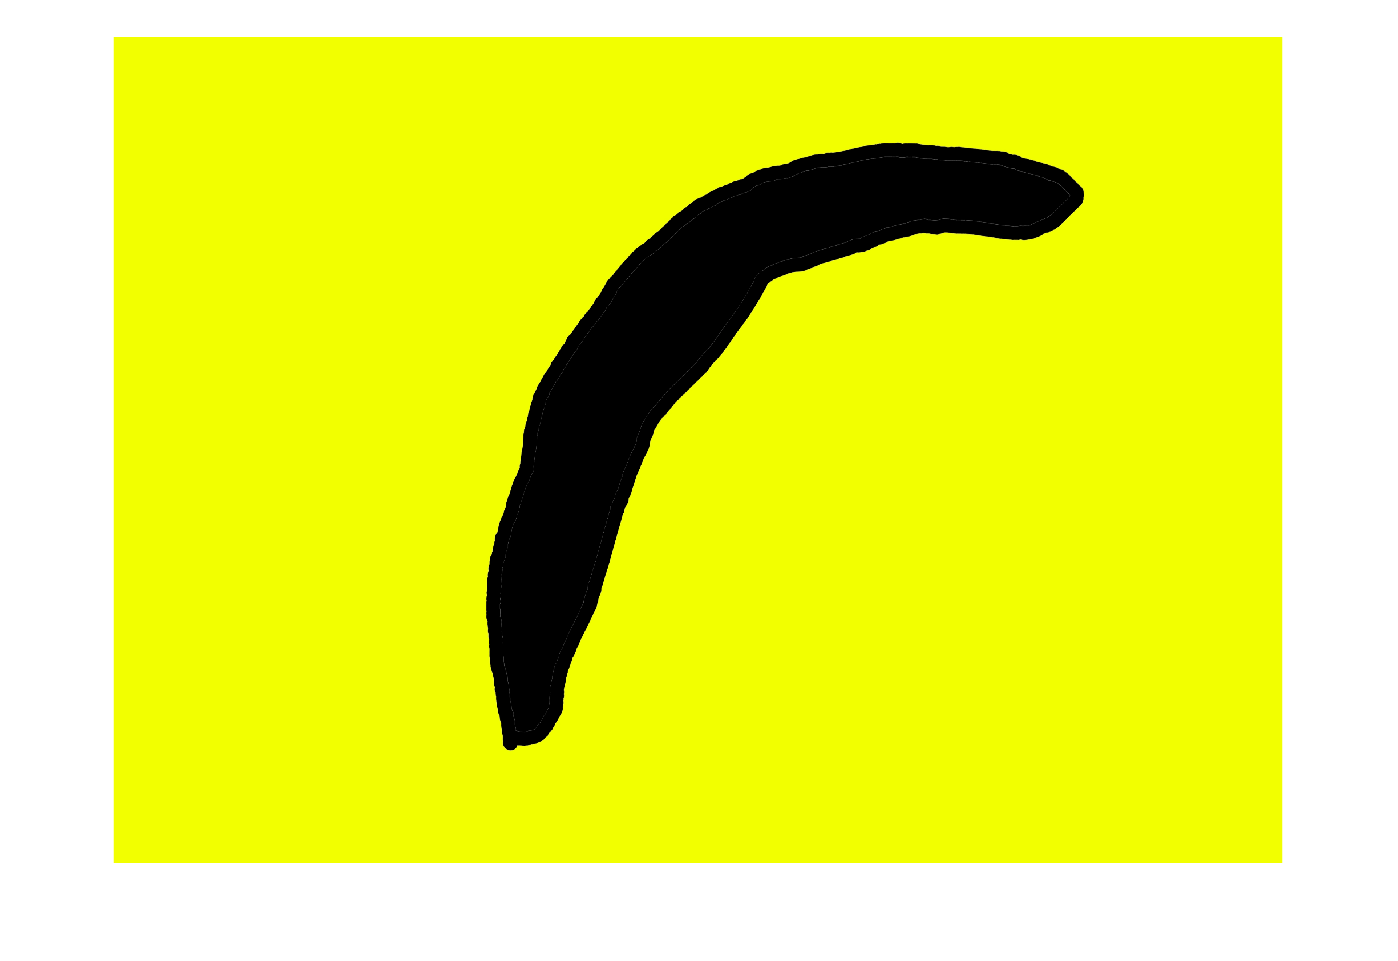

I=imread("image2.jpg");
imshow(I);

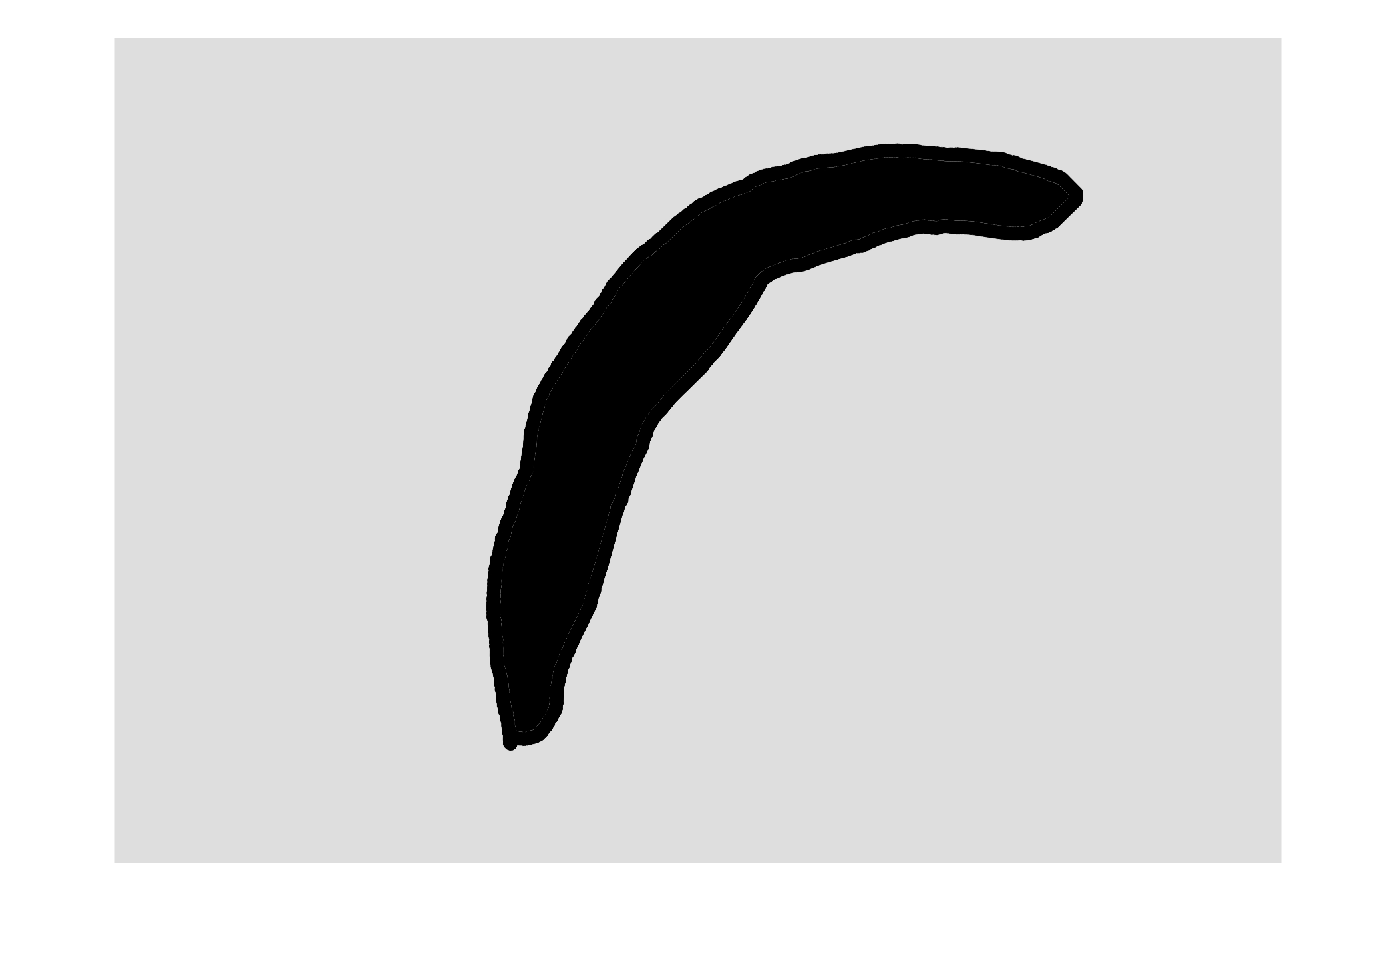

I=rgb2gray(I);
imshow(I);

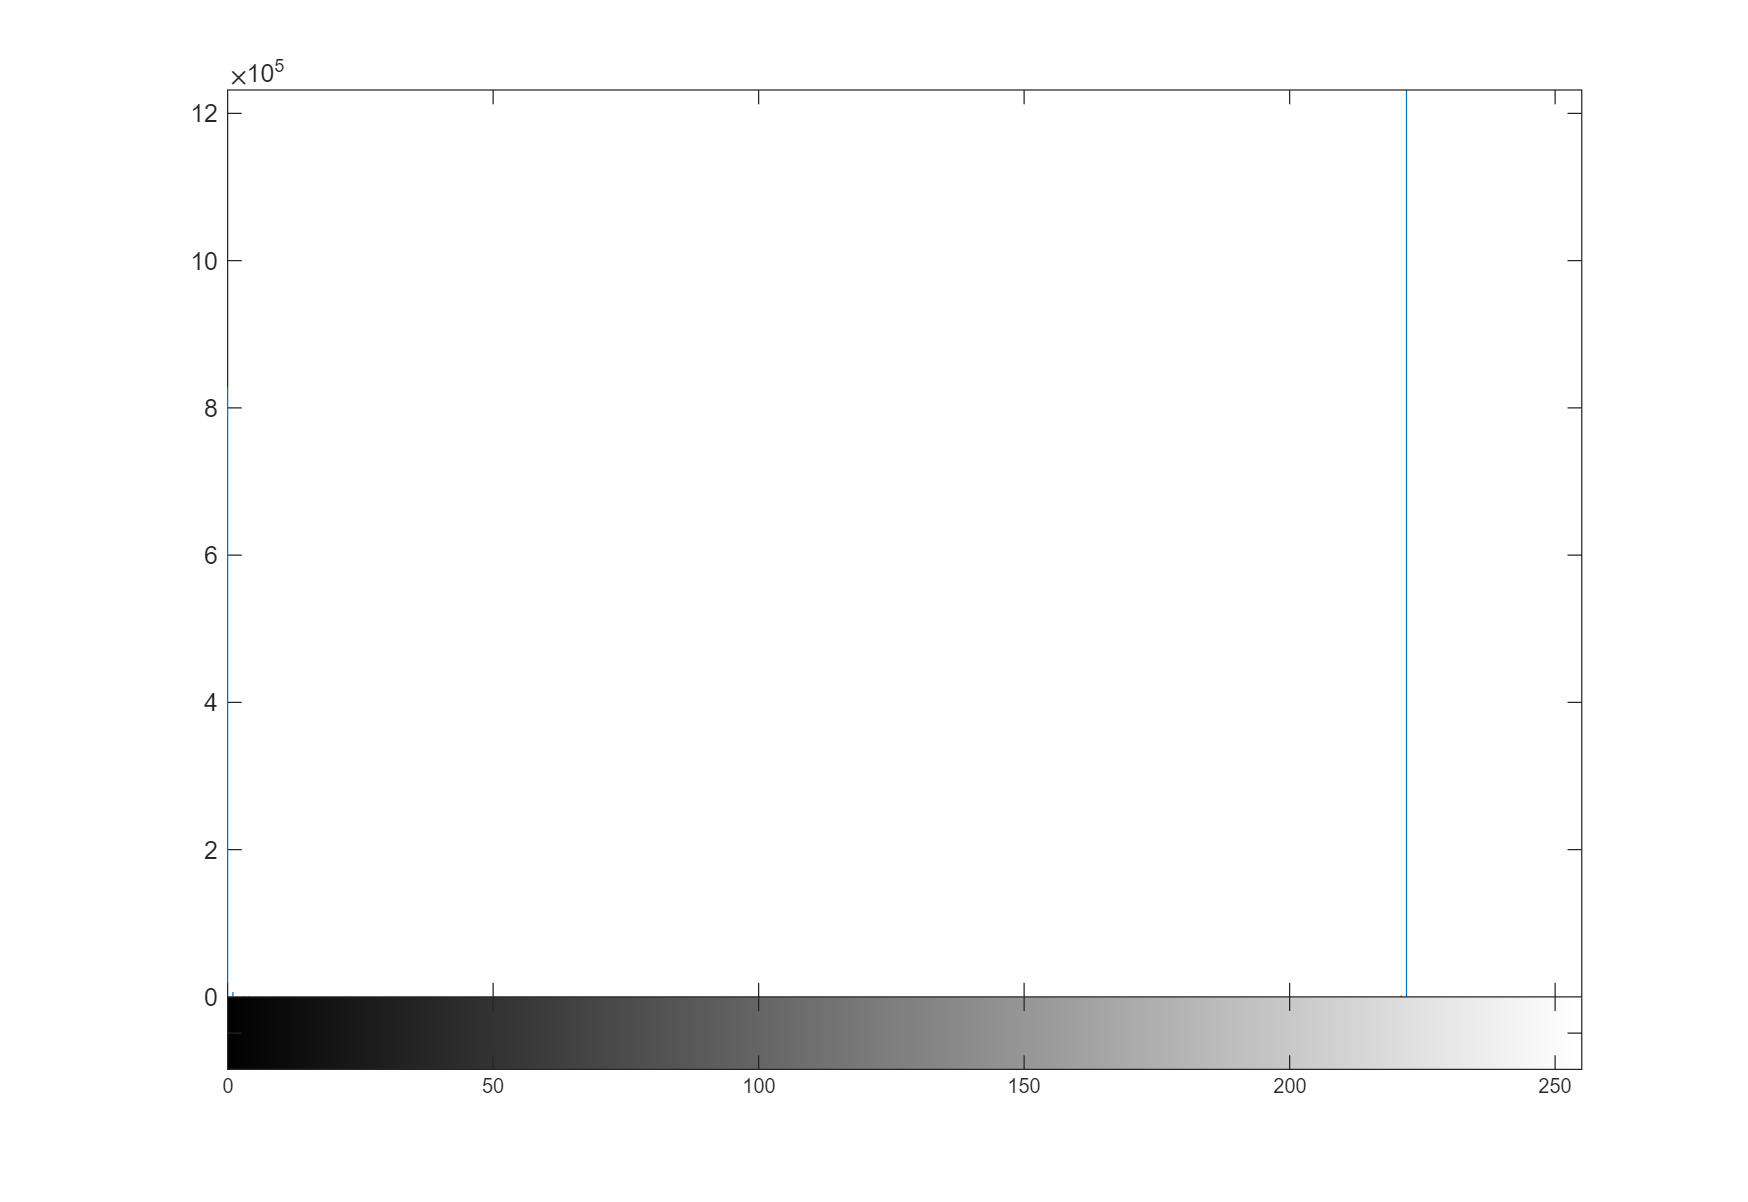

imhist(I);

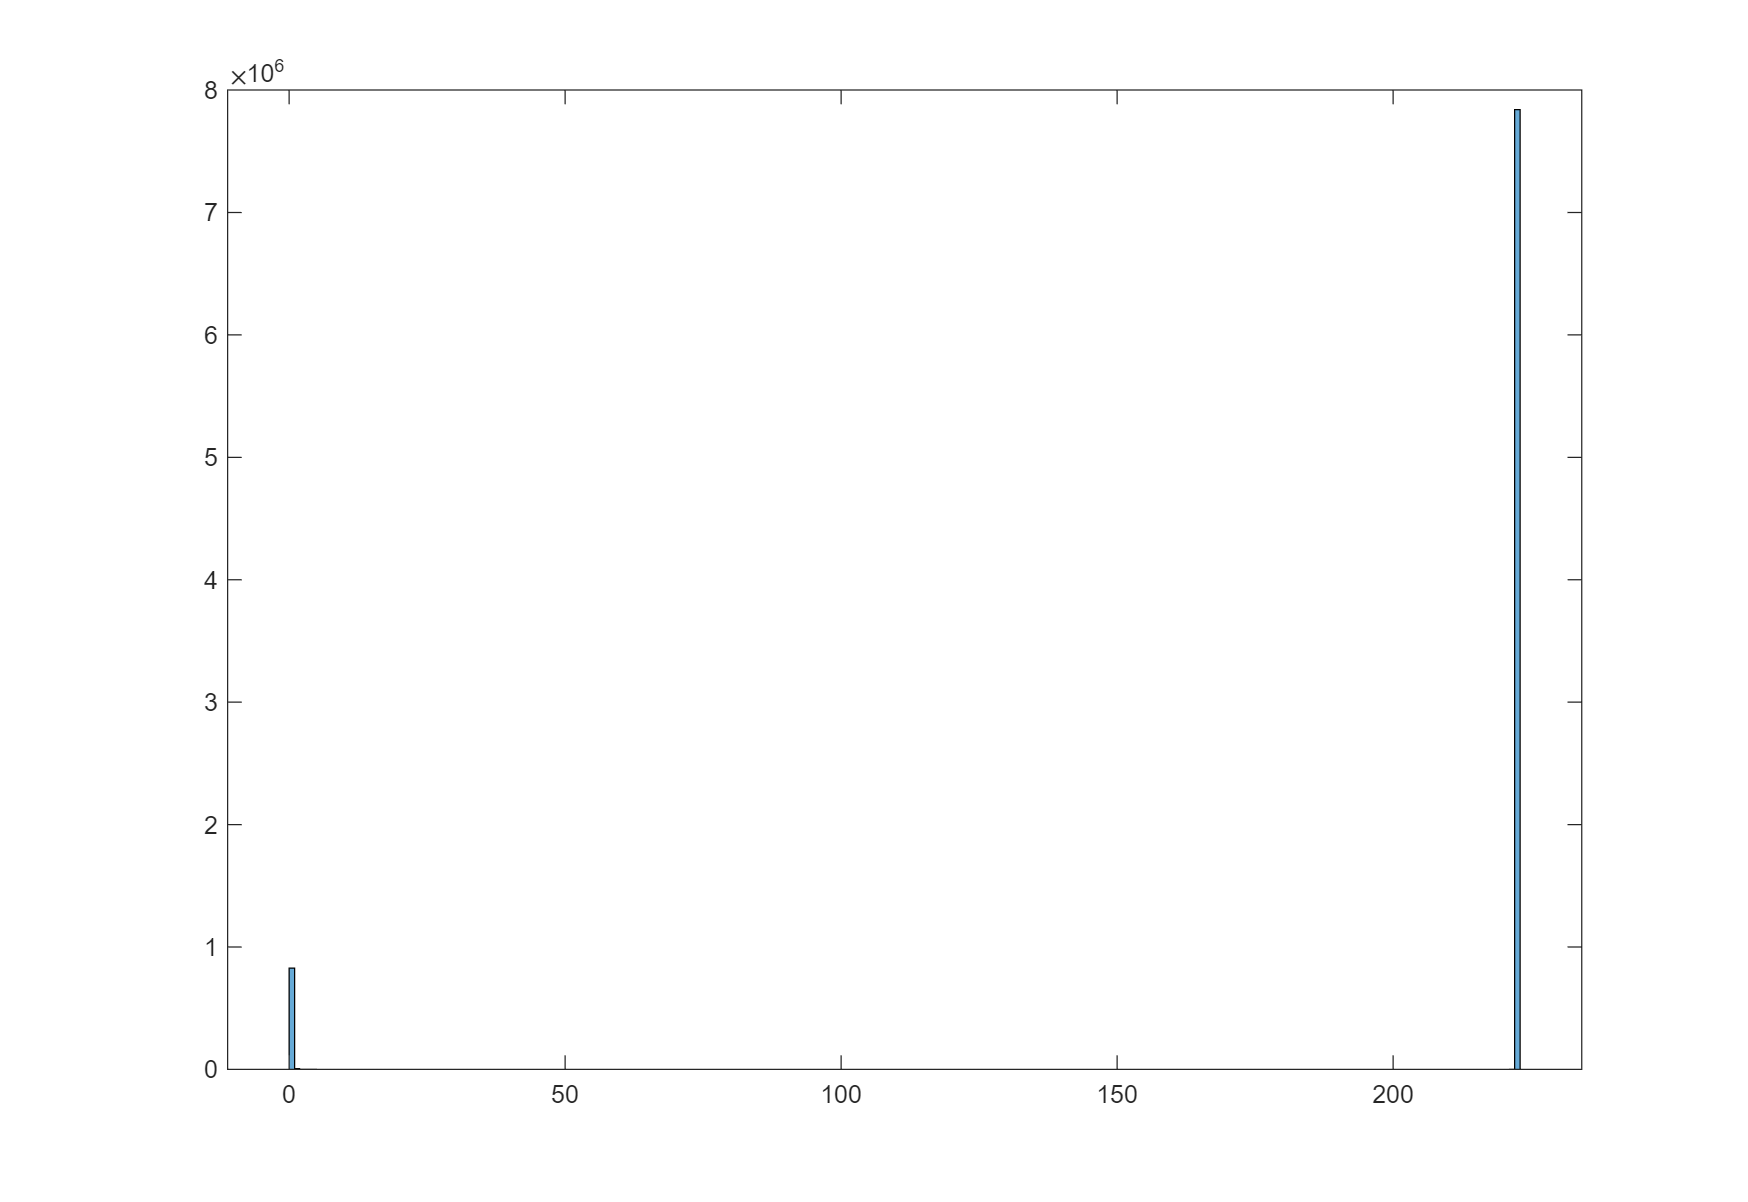

histogram(I)

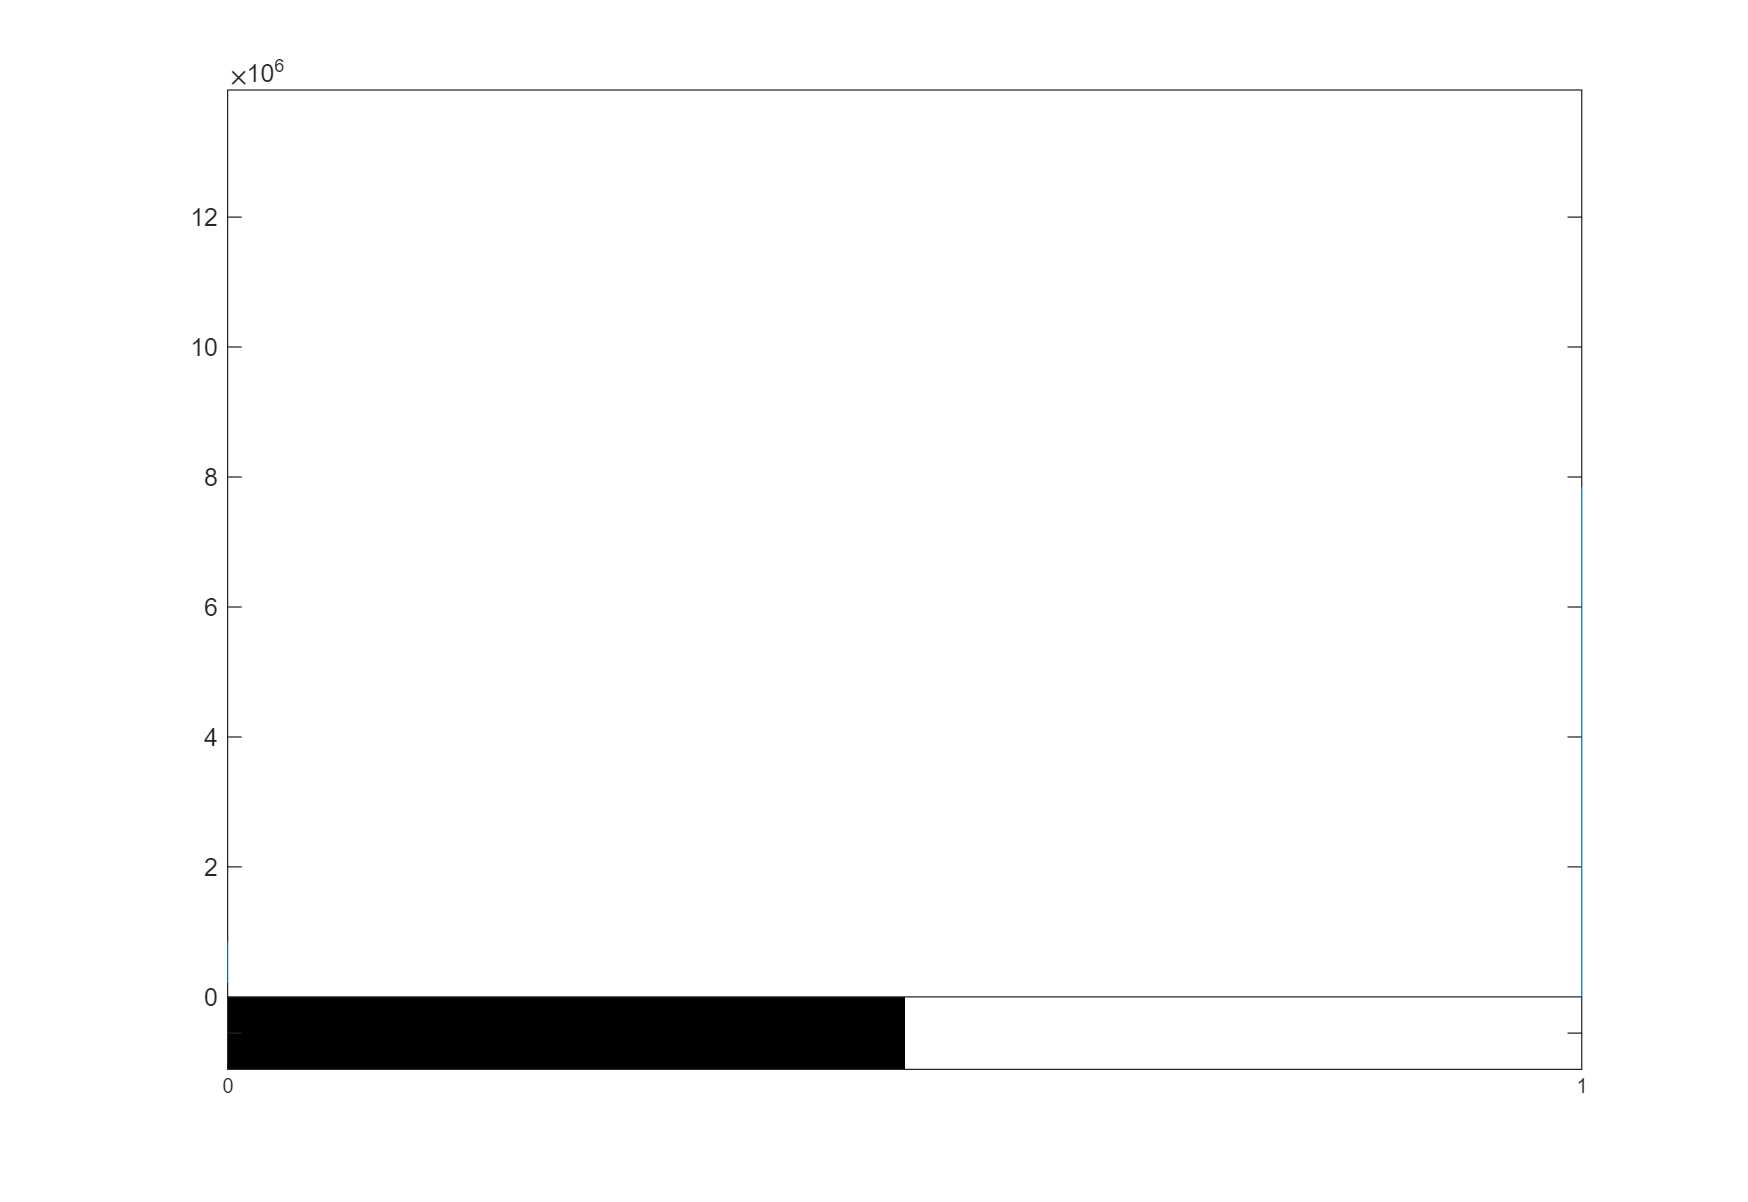

I=imbinarize(I,0.5);

imhist(I);

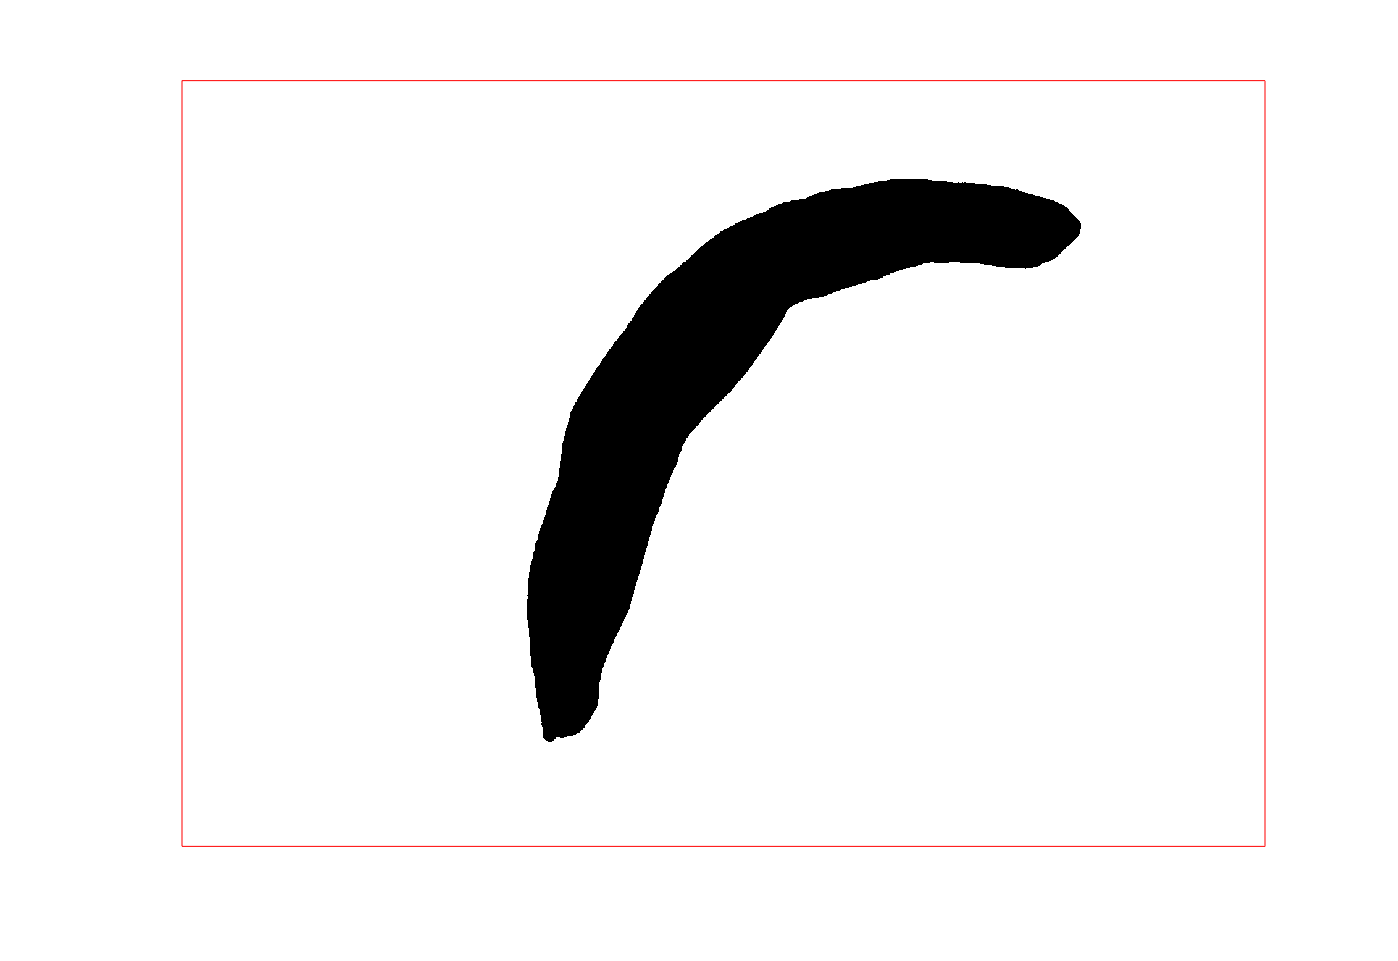

imshow(I);

feats=regionprops(I,'Area','Centroid','BoundingBox','Orientation');

rectangle('Position',feats.BoundingBox,'EdgeColor','red');

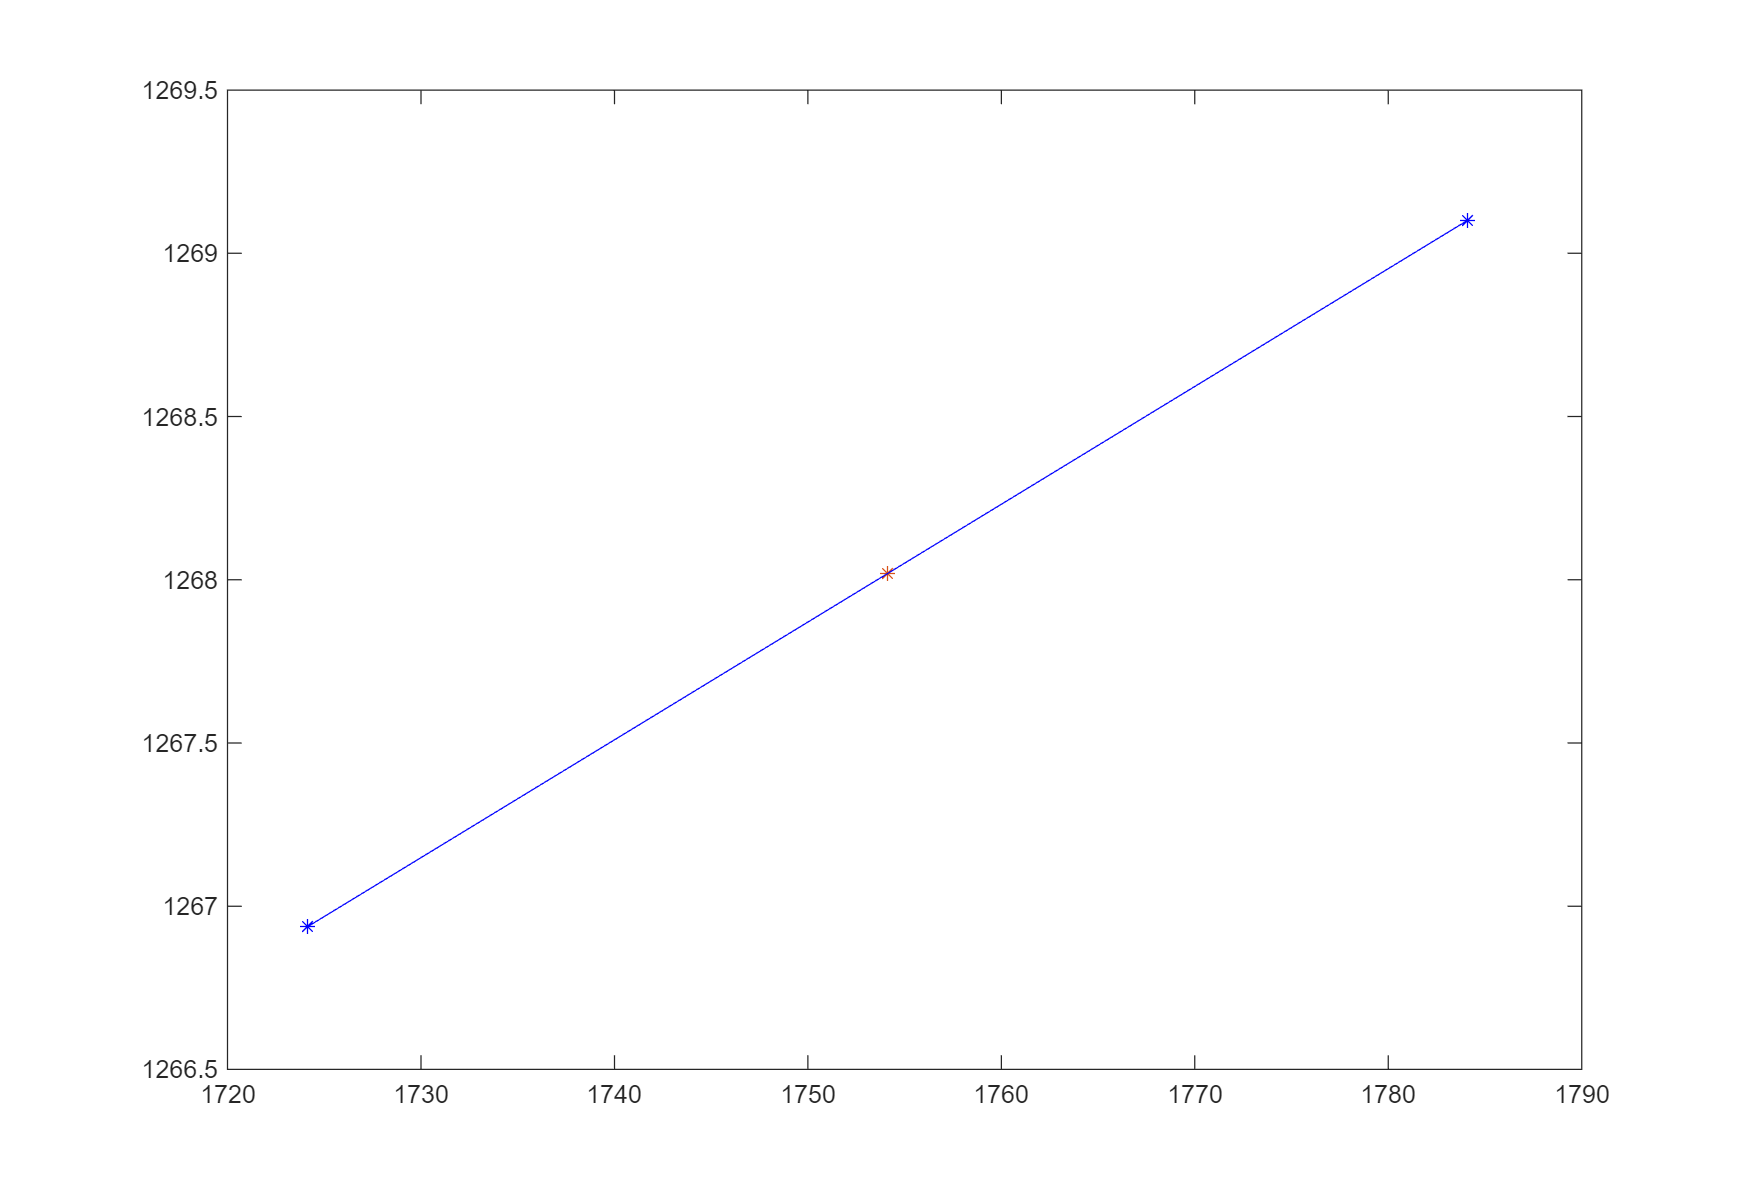

centroids =cat(1,feats.Centroid);
plot(centroids(:,1),centroids(:,2),'b*');hold on

x=feats.Centroid(1,1);
y=feats.Centroid(1,2);
plot(x,y,"*");
a1=tan((feats.Orientation)*pi/180);
b1=y-a1*x;
x1=x-30;
x2=x+30;
y1=a1*x1+b1;
y2=a1*x2+b1;
plot([x1 x2],[y2 y1],'-b*')
hold off

Task 1.2

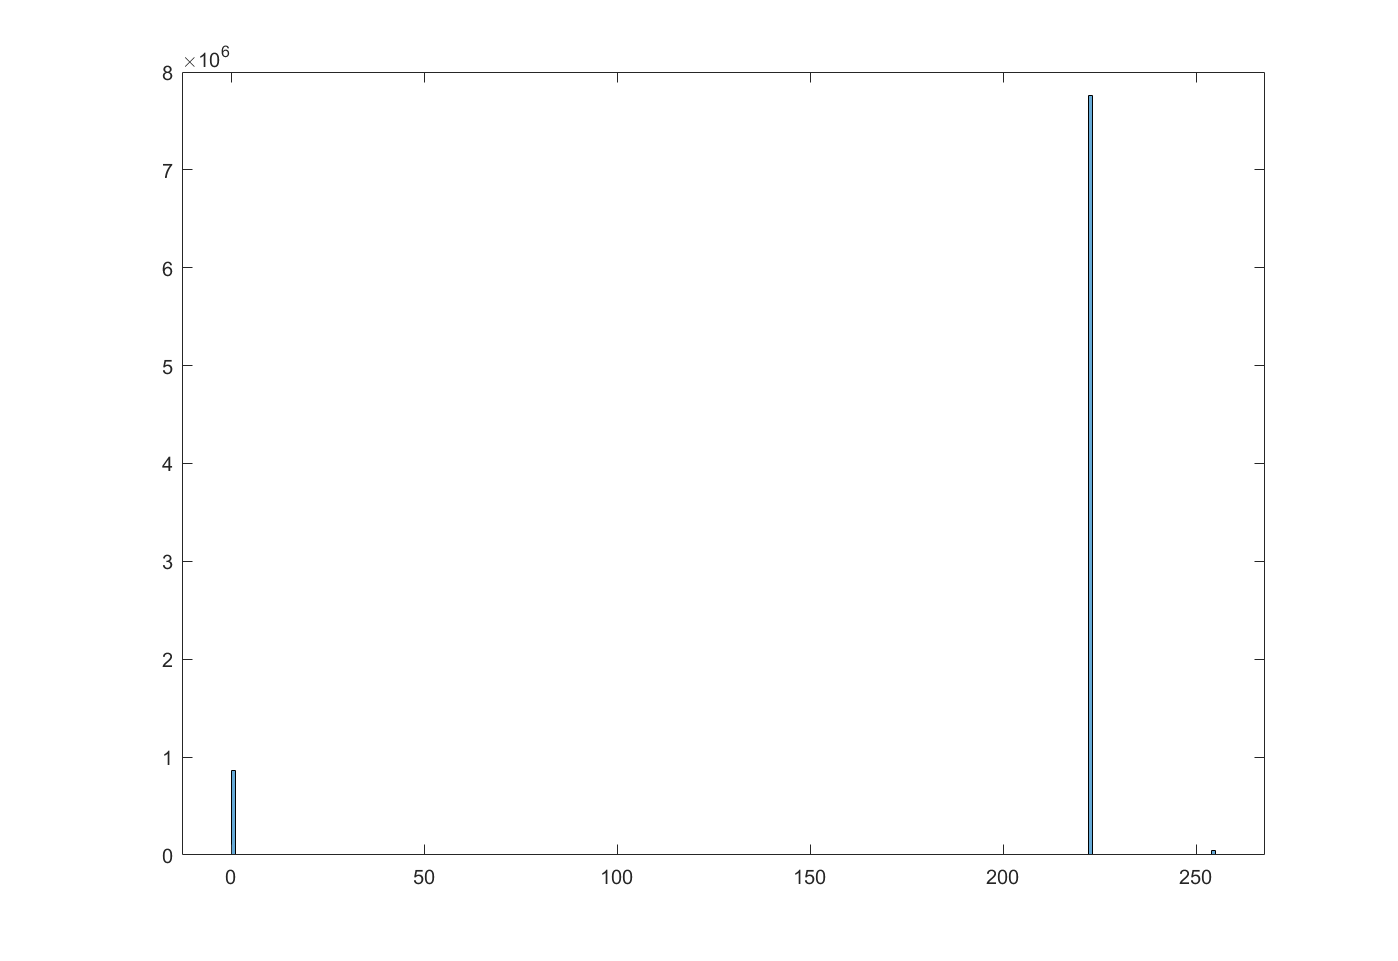

I=imread("image2.jpg");
I=rgb2gray(I);
I=imnoise(I,"salt & pepper",0.01);
histogram(I)

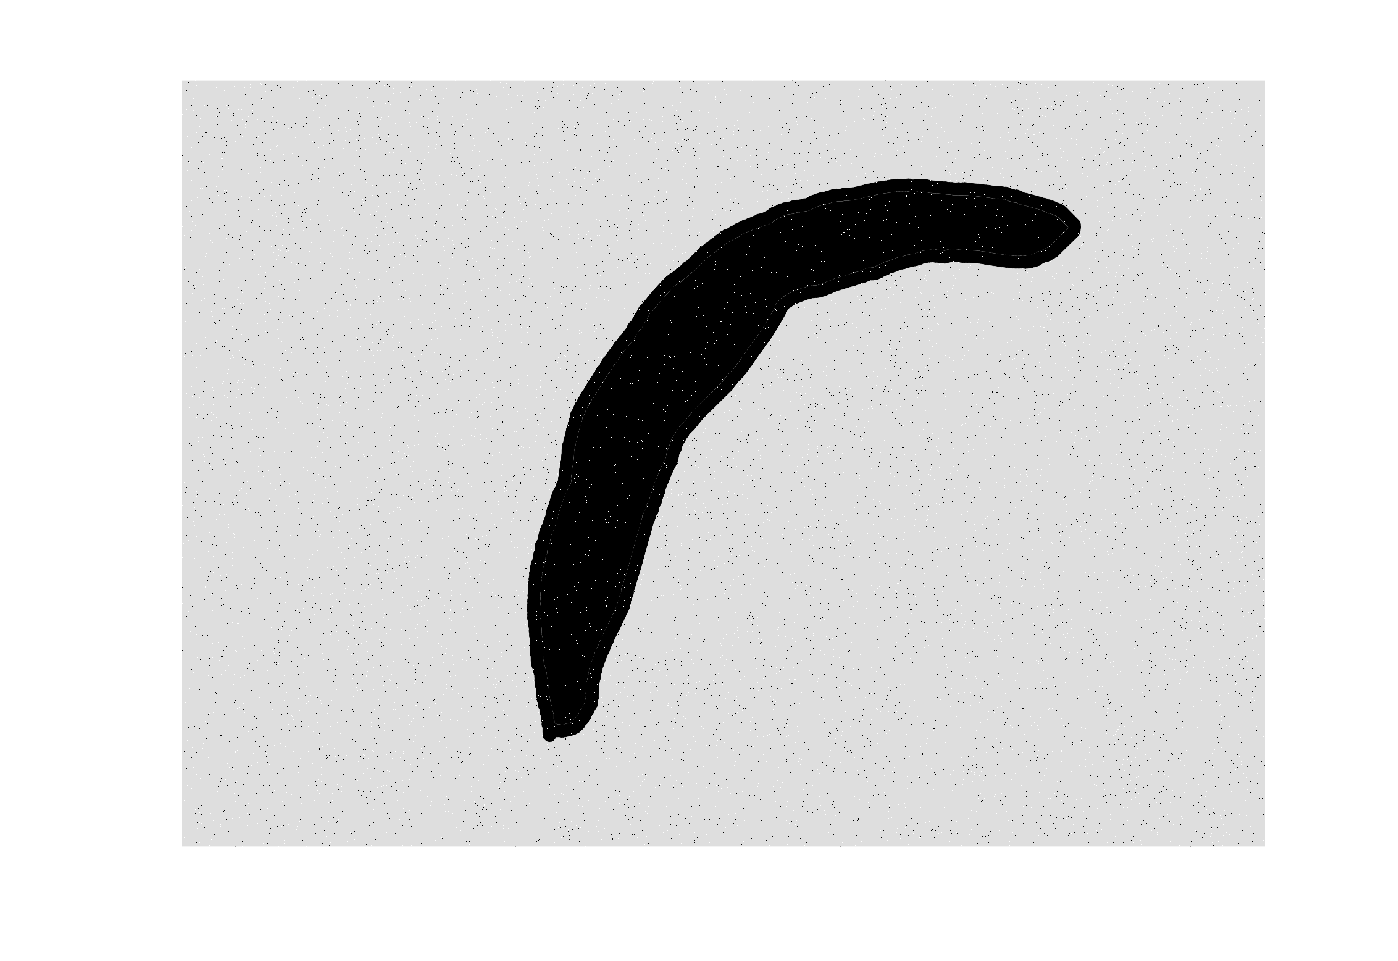

imshow(I);

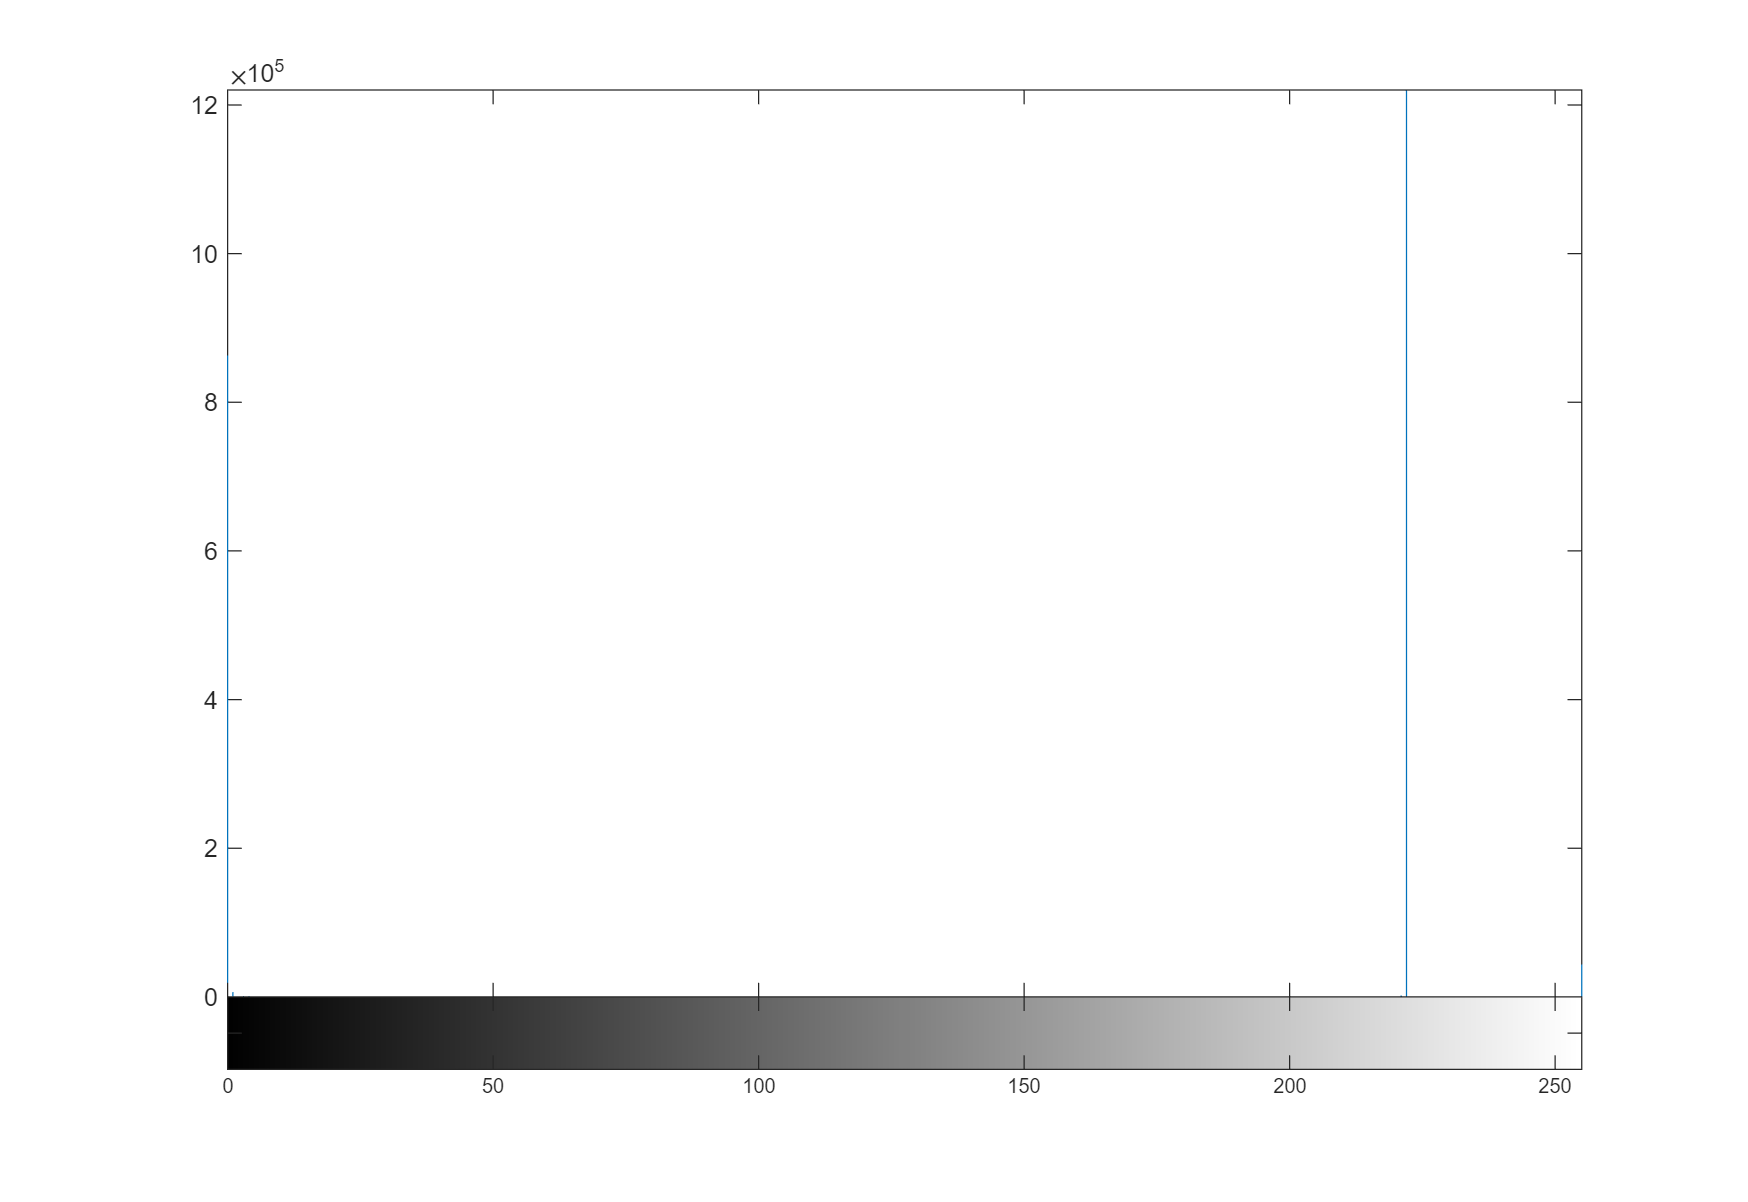

imhist(I);

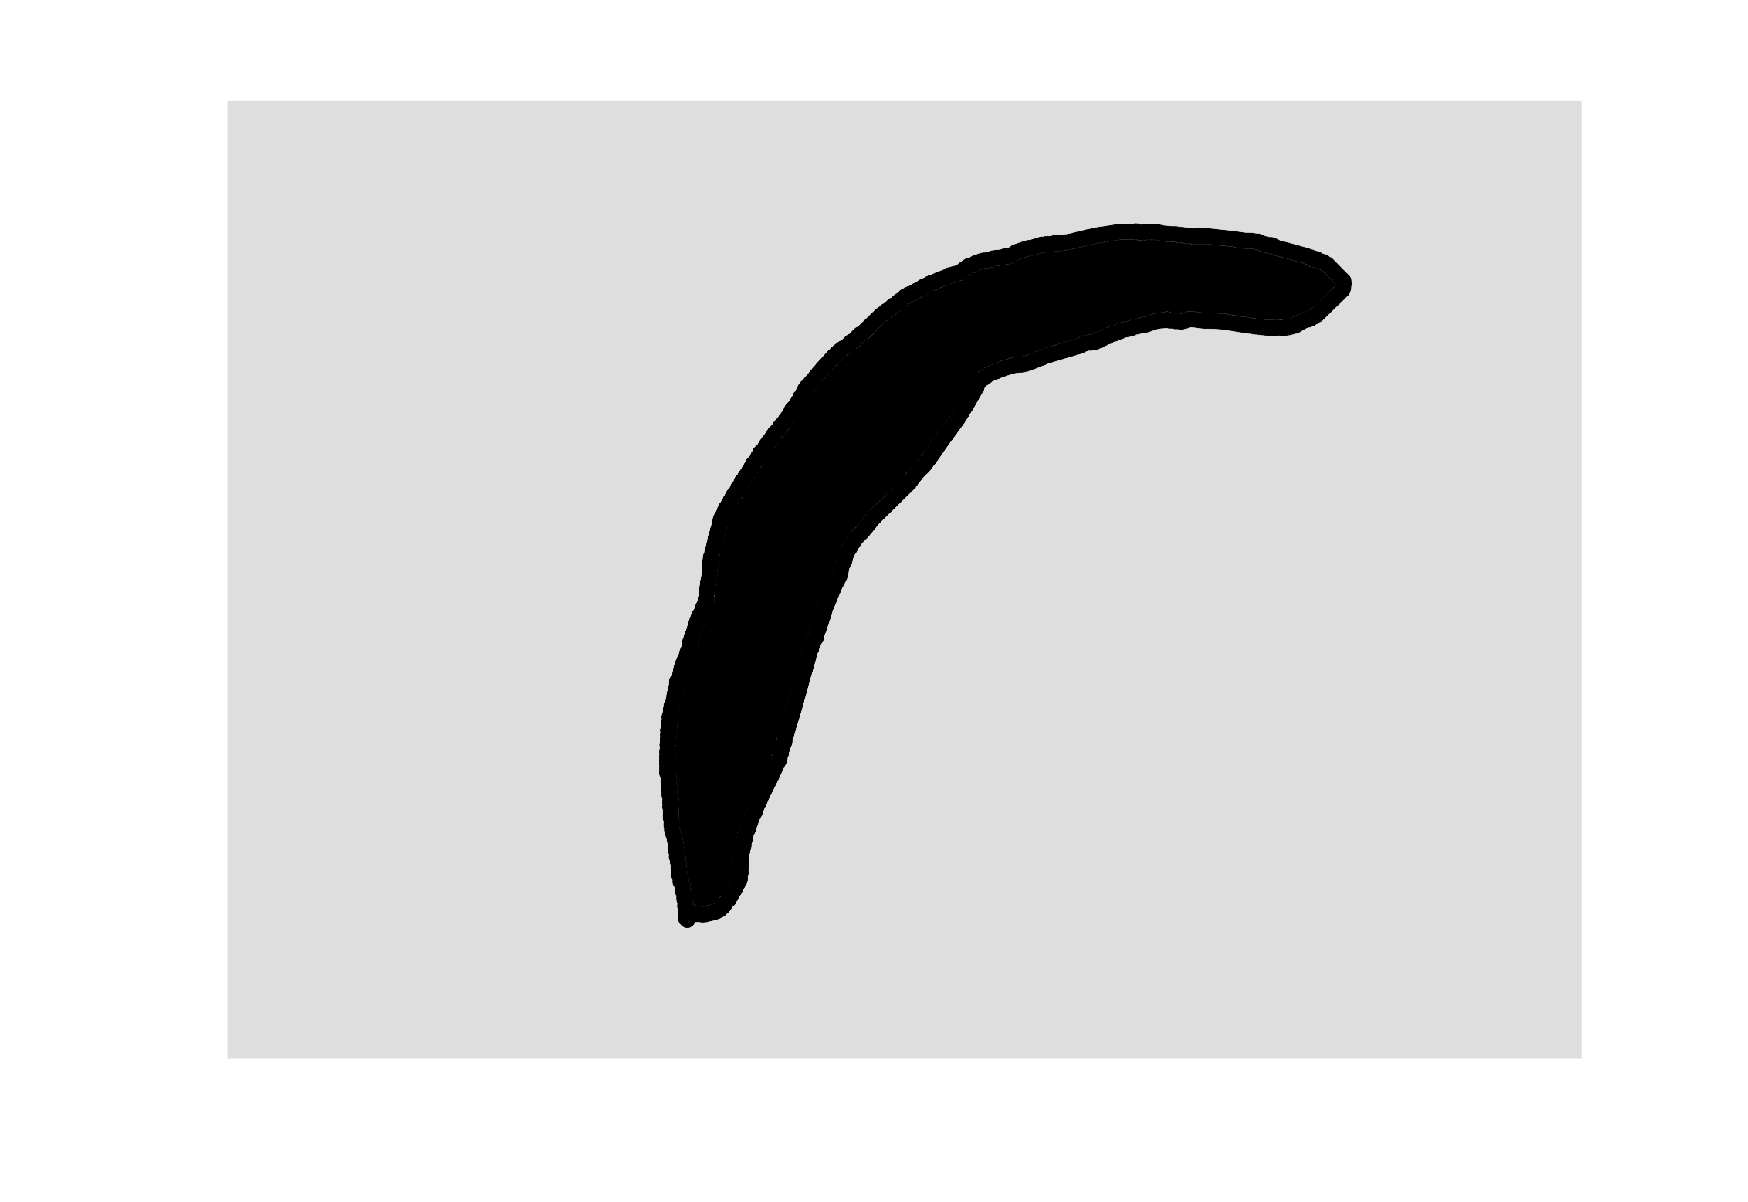


I = medfilt2(I,"symmetric");
imshow(I);

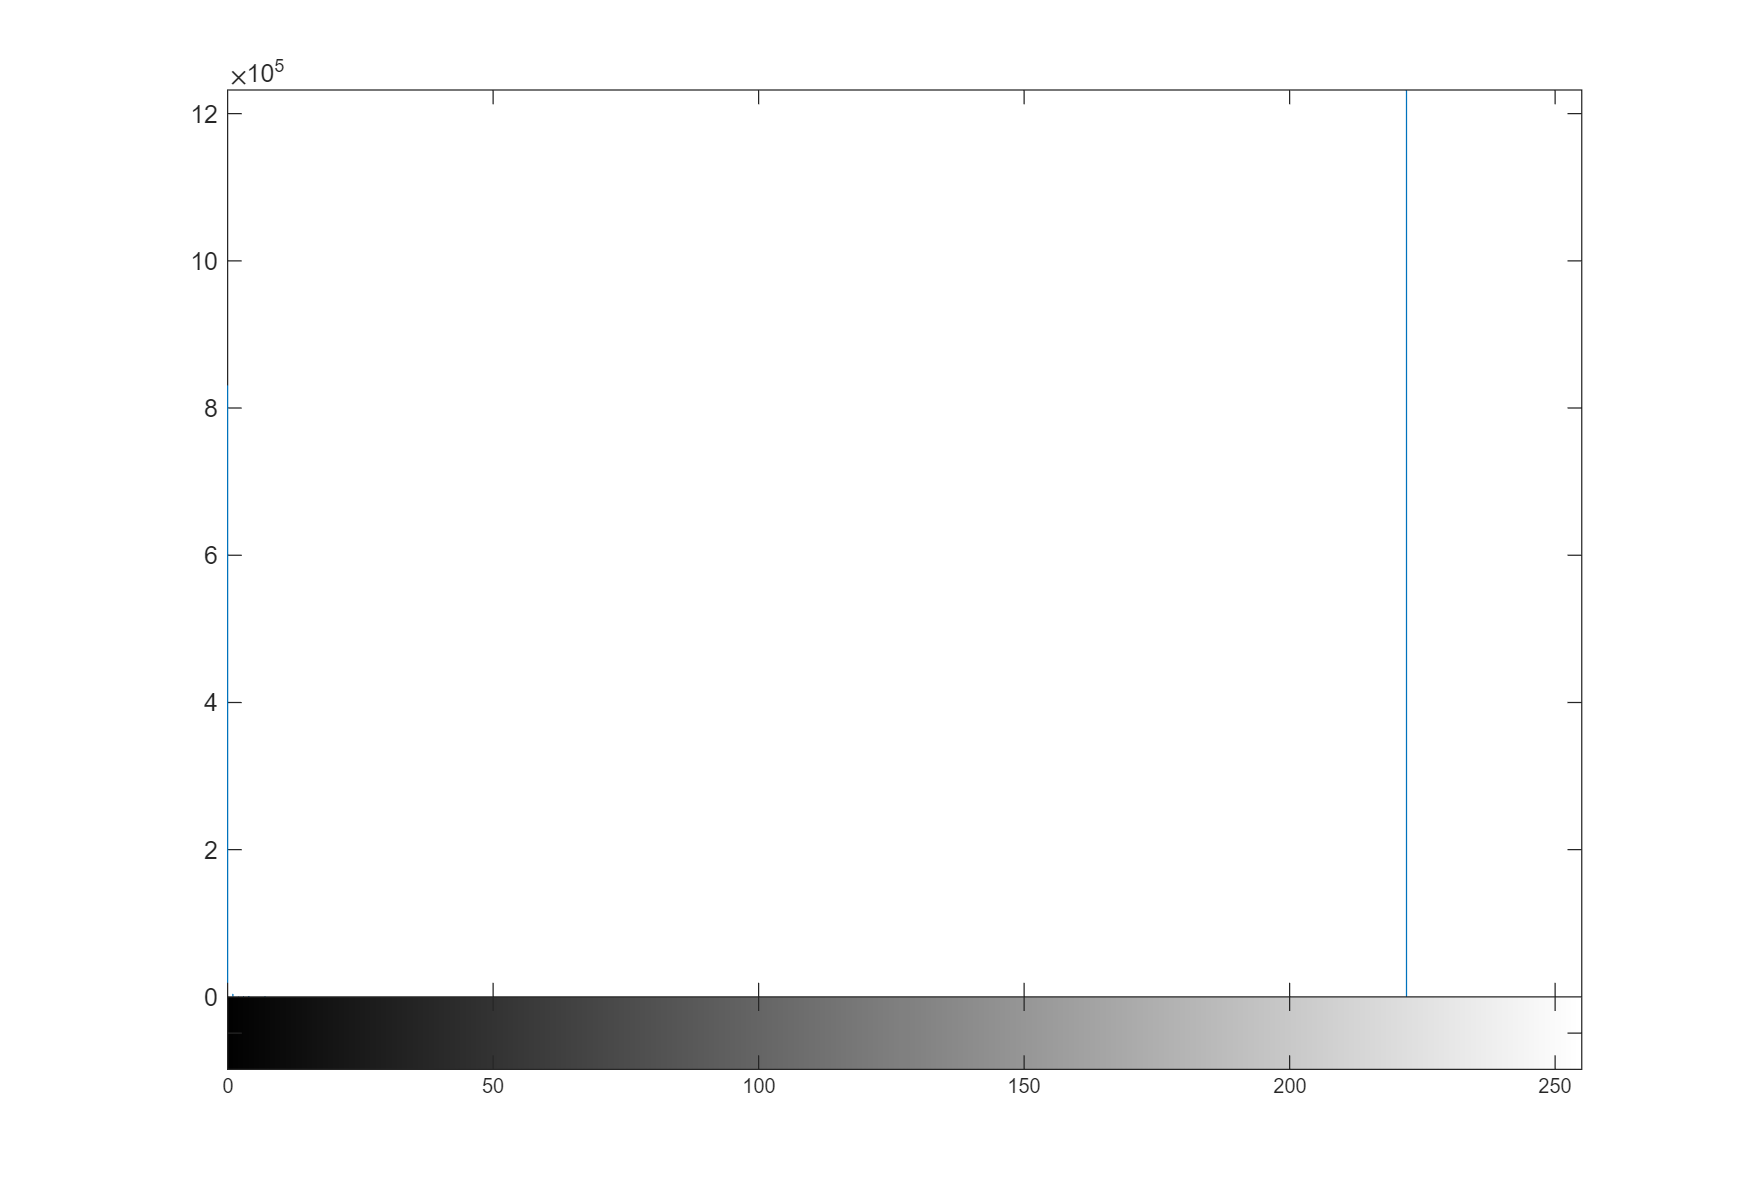

imhist(I);

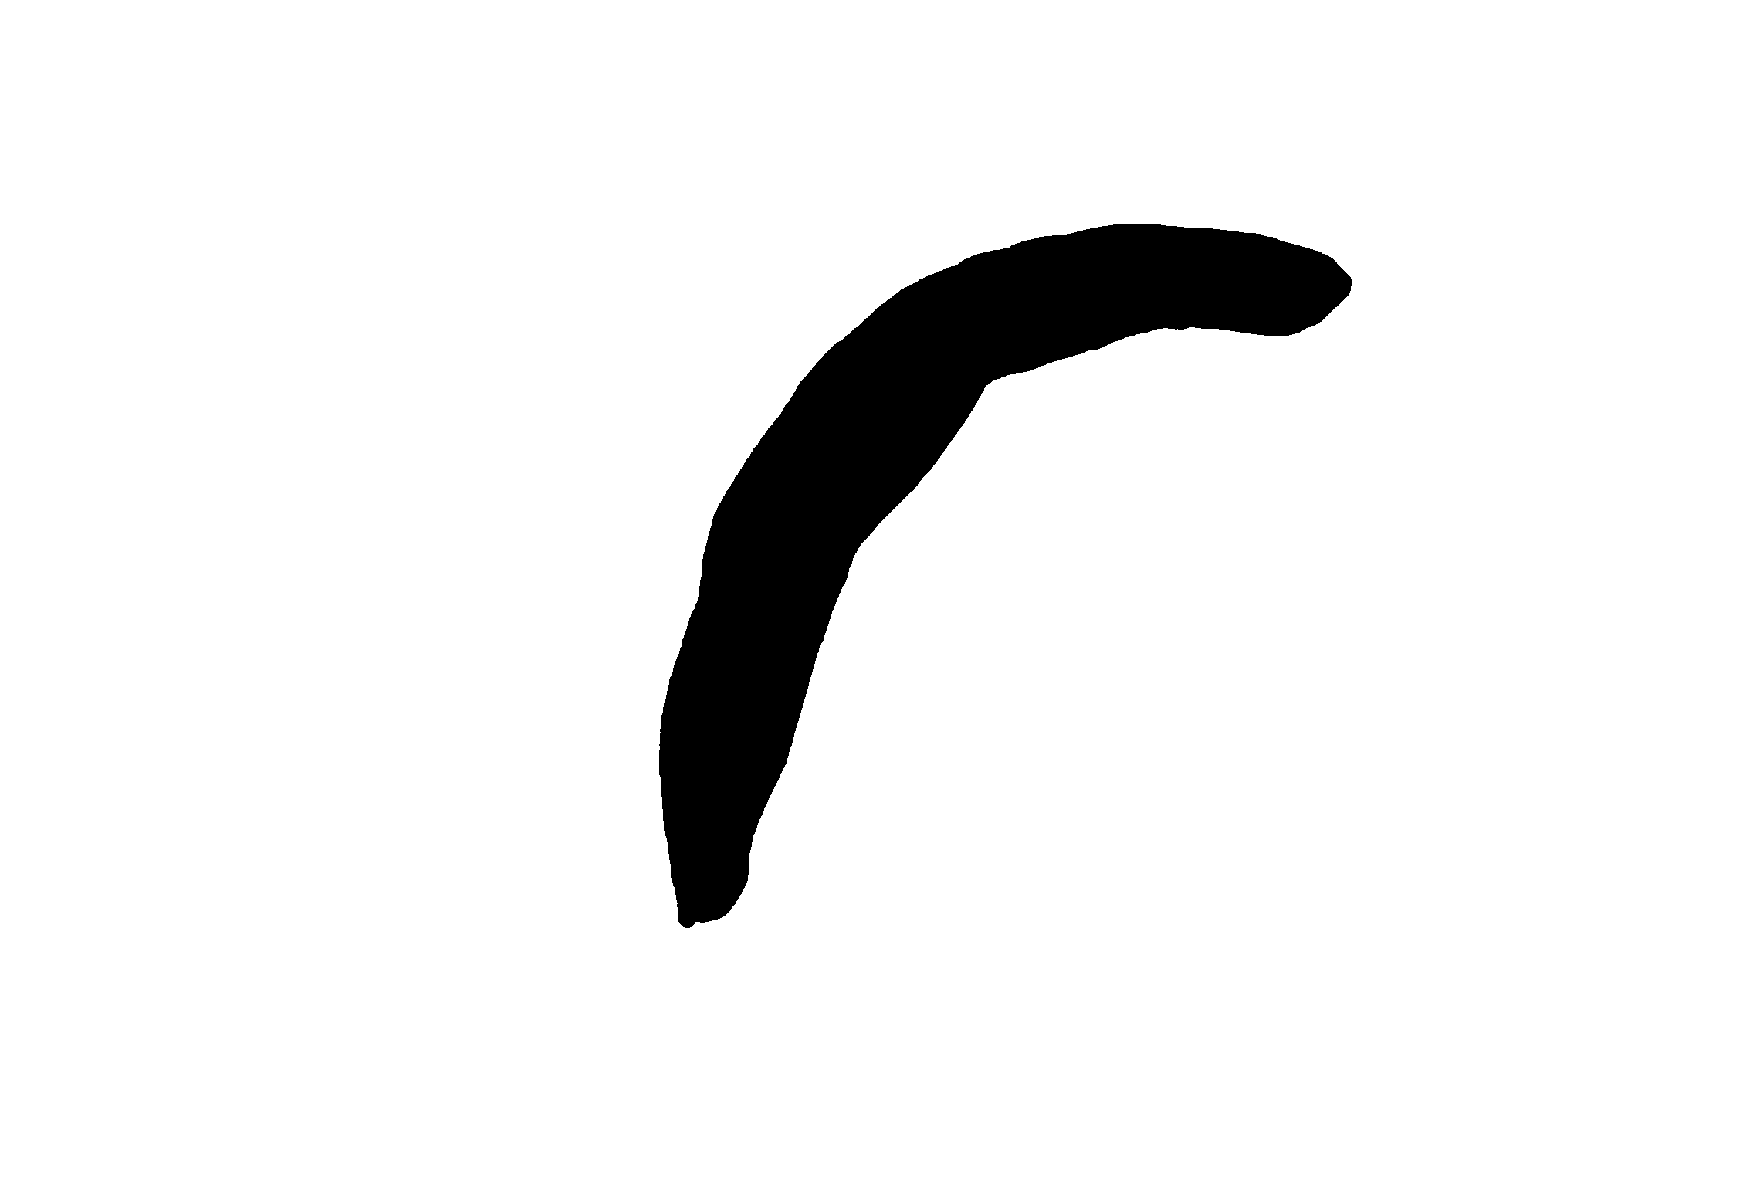



I=imbinarize(I,0.5);
imshow(I);

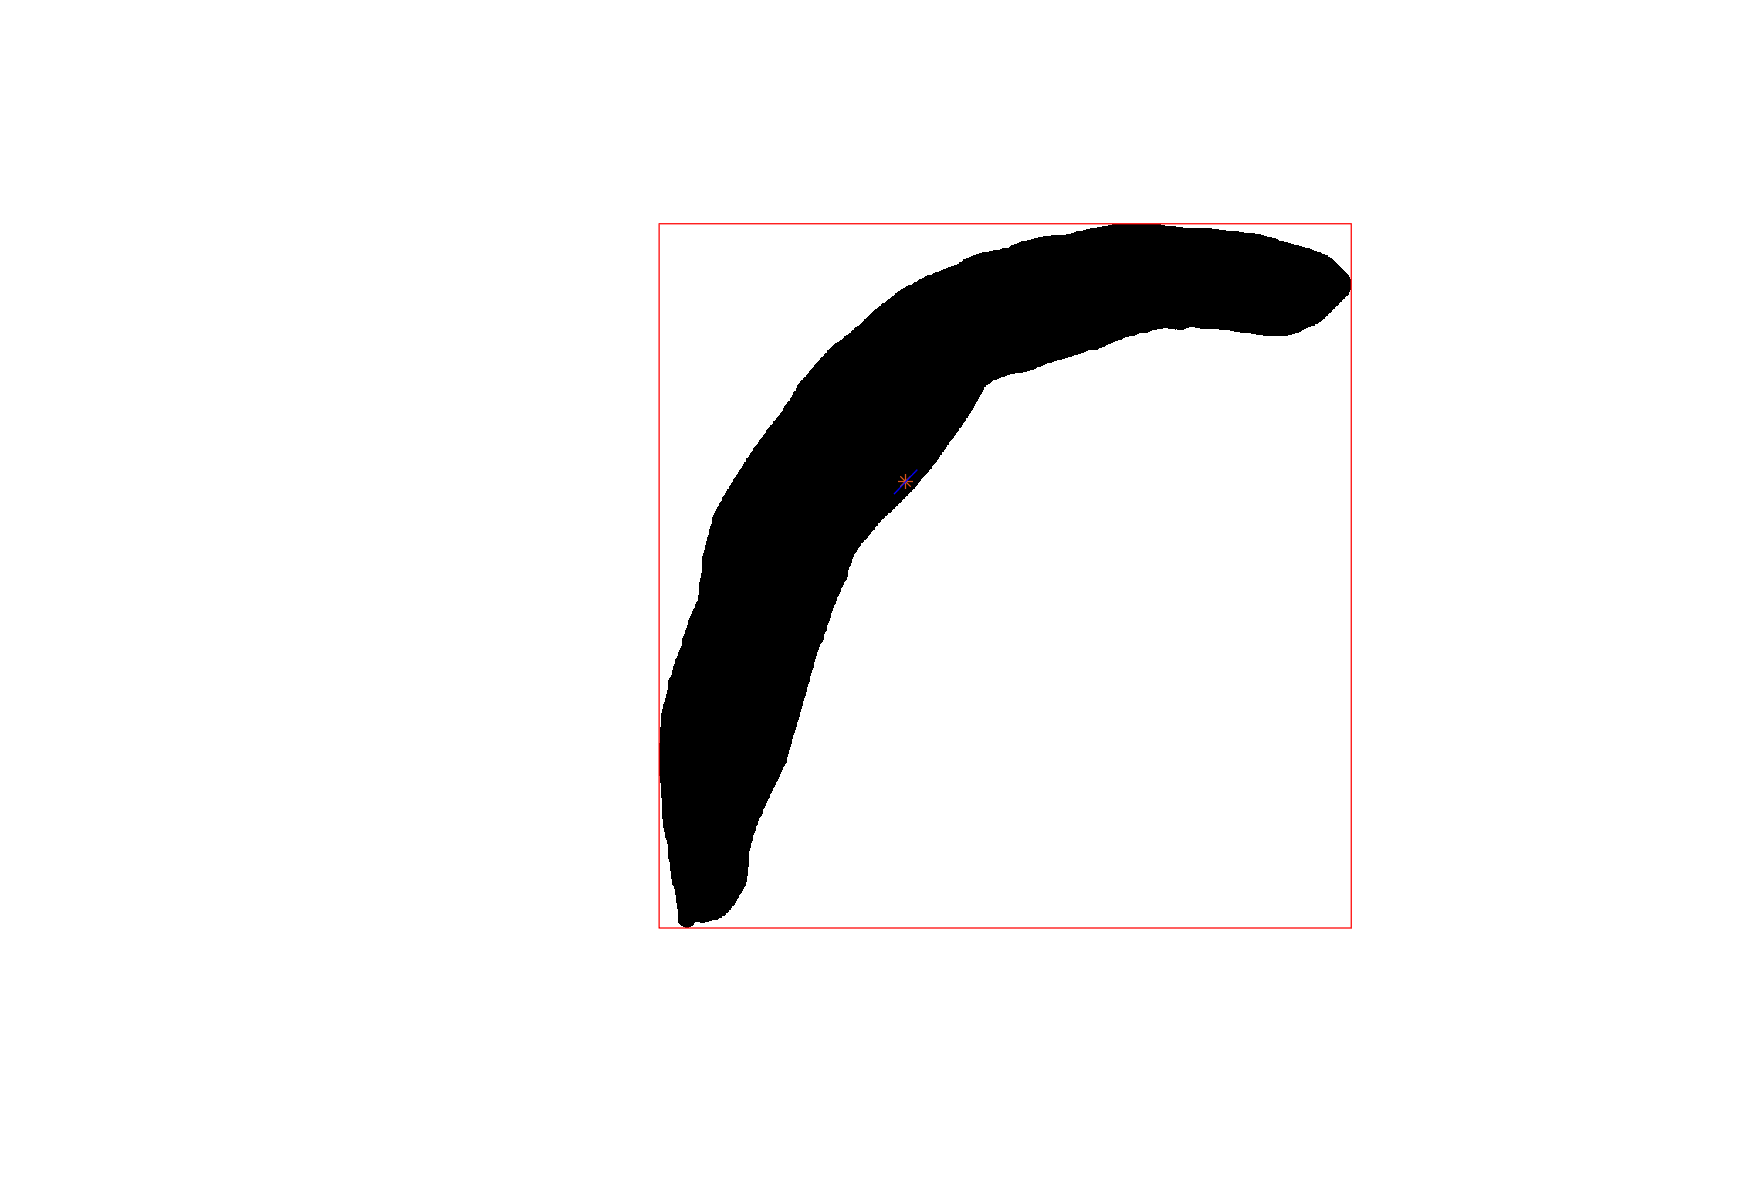


I=imerode(I,[0 1]);
imshow(I);hold on

I=1-logical(I);
feats=regionprops(I,'all');

rectangle('Position',feats.BoundingBox,'EdgeColor','red');
centroids =cat(1,feats.Centroid);
plot(centroids(:,1),centroids(:,2),'b*')

x=feats.Centroid(1,1);
y=feats.Centroid(1,2);
plot(x,y,"*");
a1=tan((feats.Orientation)*pi/180);
b1=y-a1*x;
x1=x-30;
x2=x+30;
y1=a1*x1+b1;
y2=a1*x2+b1;
plot([x1 x2],[y2 y1],'-b')
hold off

Task 1.3

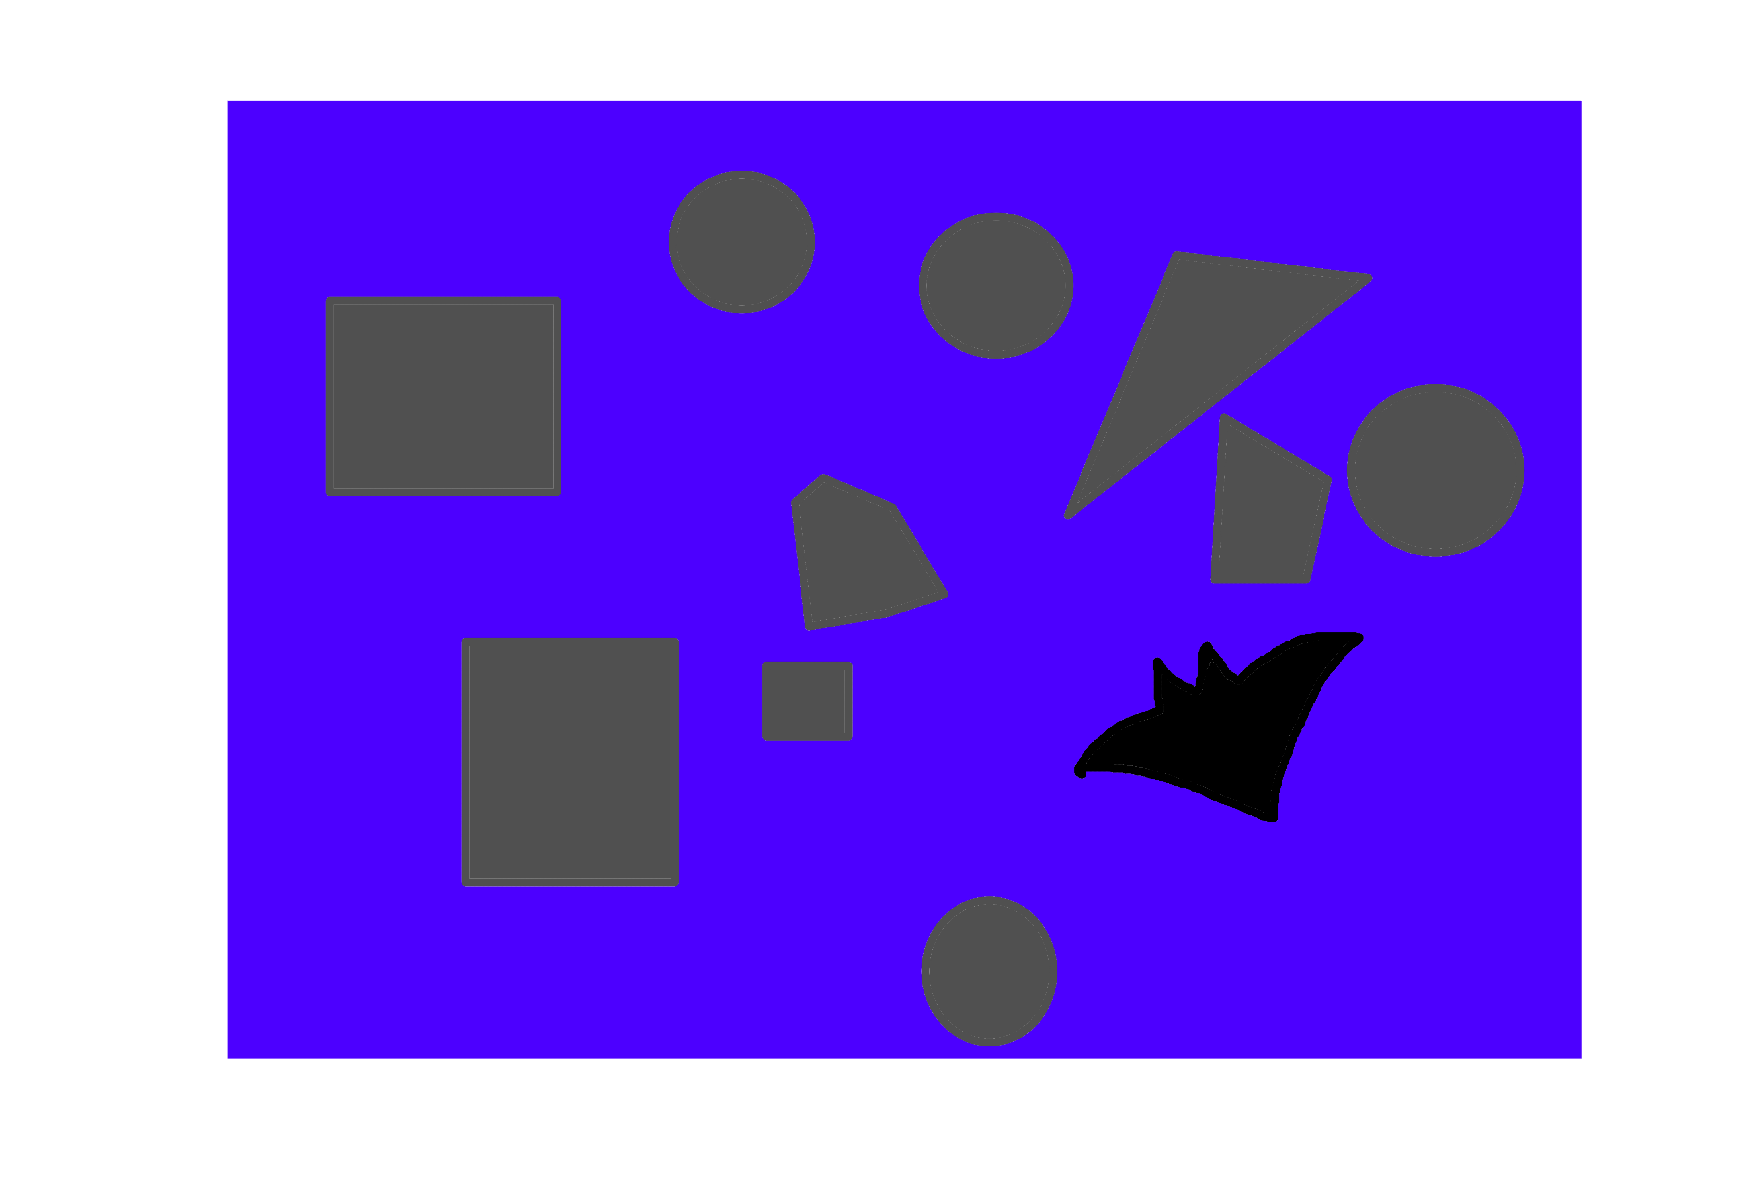

I=imread("image.jpg");
imshow(I);

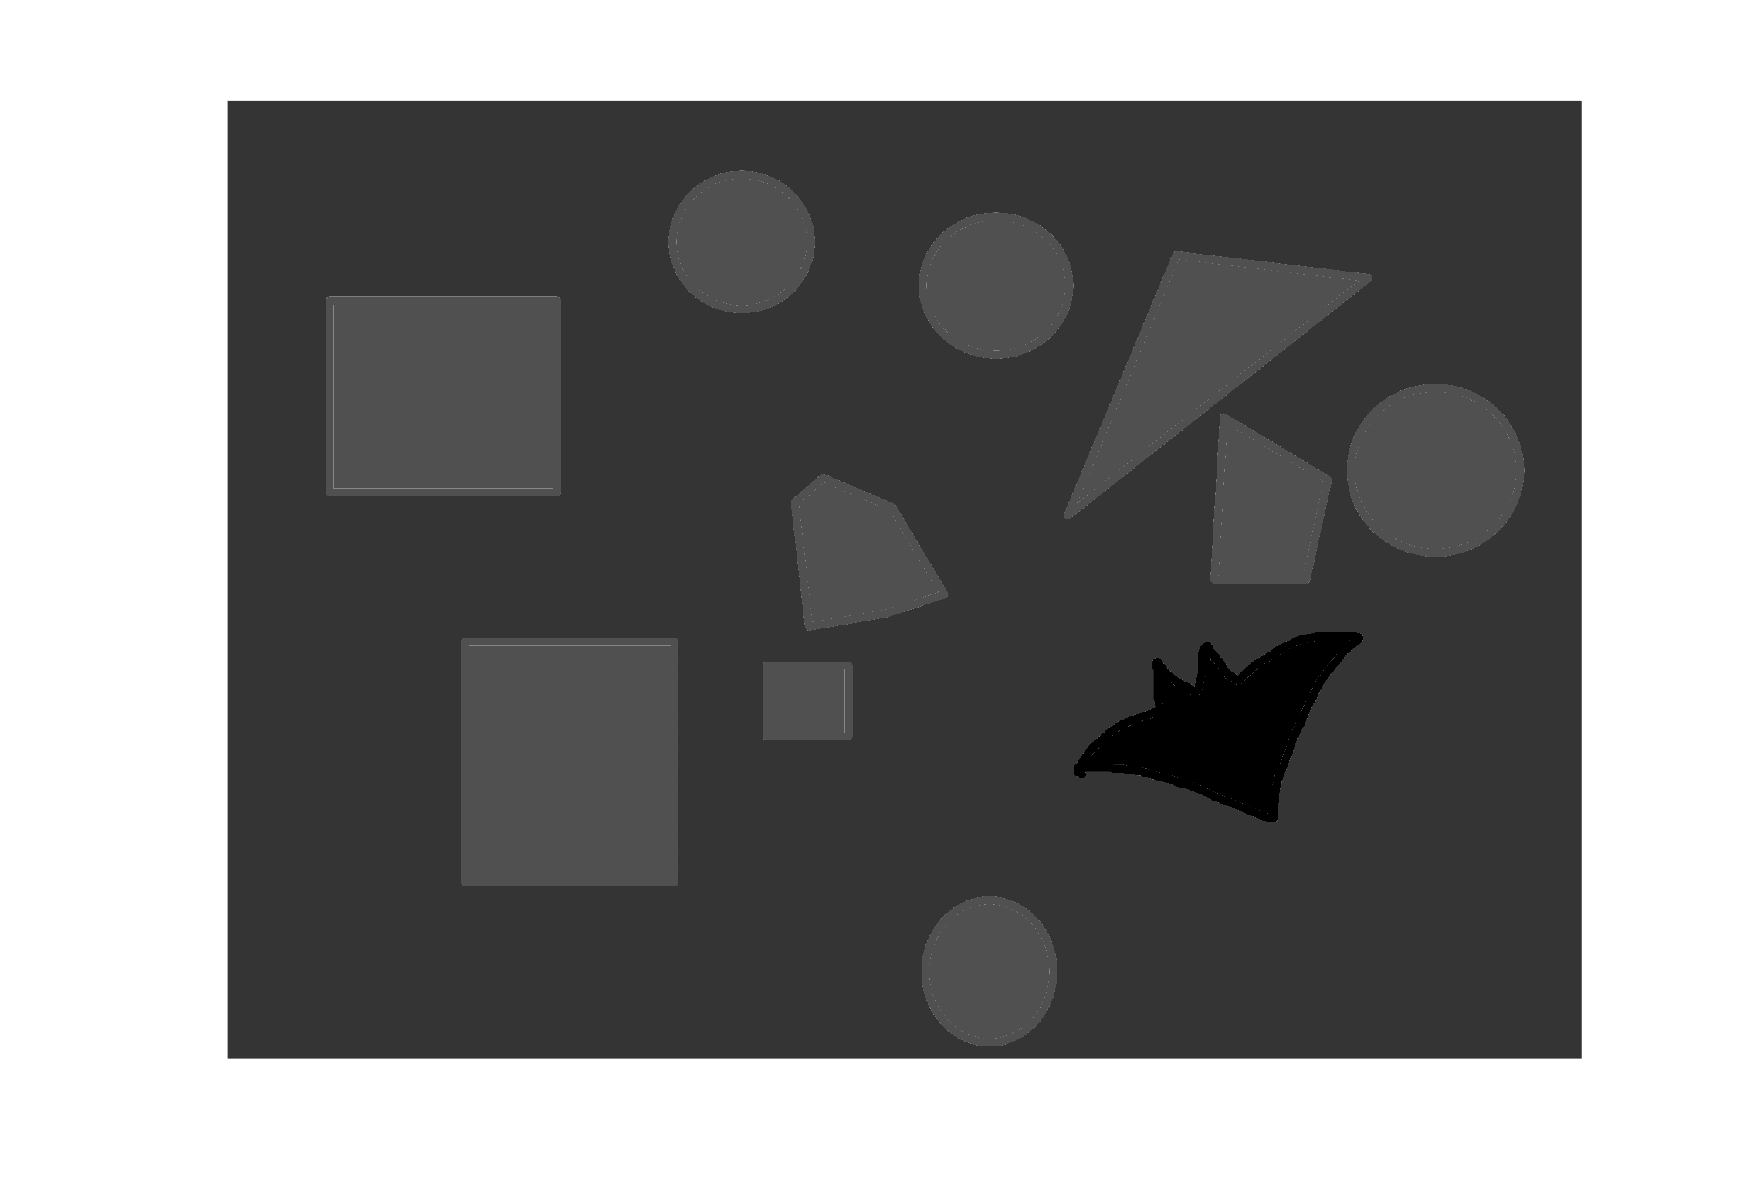

I=rgb2gray(I);
imshow(I);

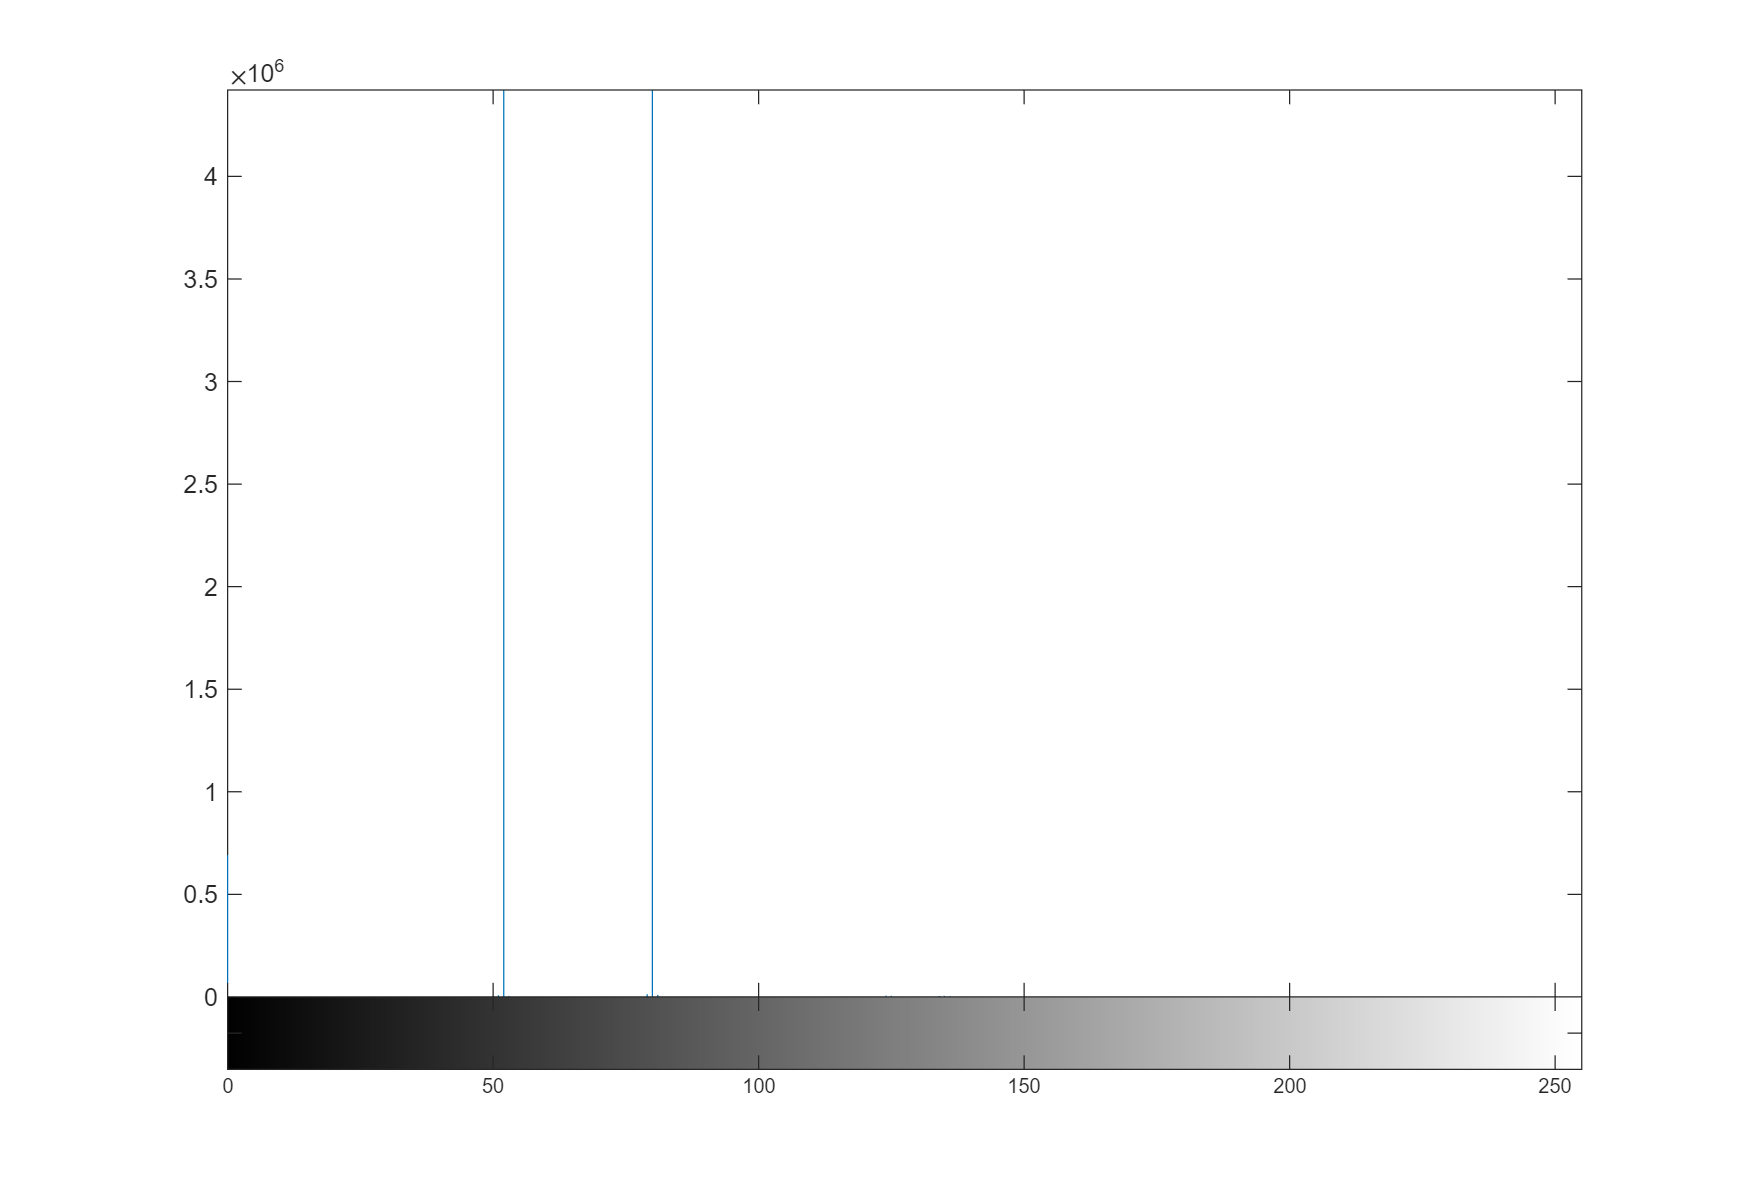

imhist(I);

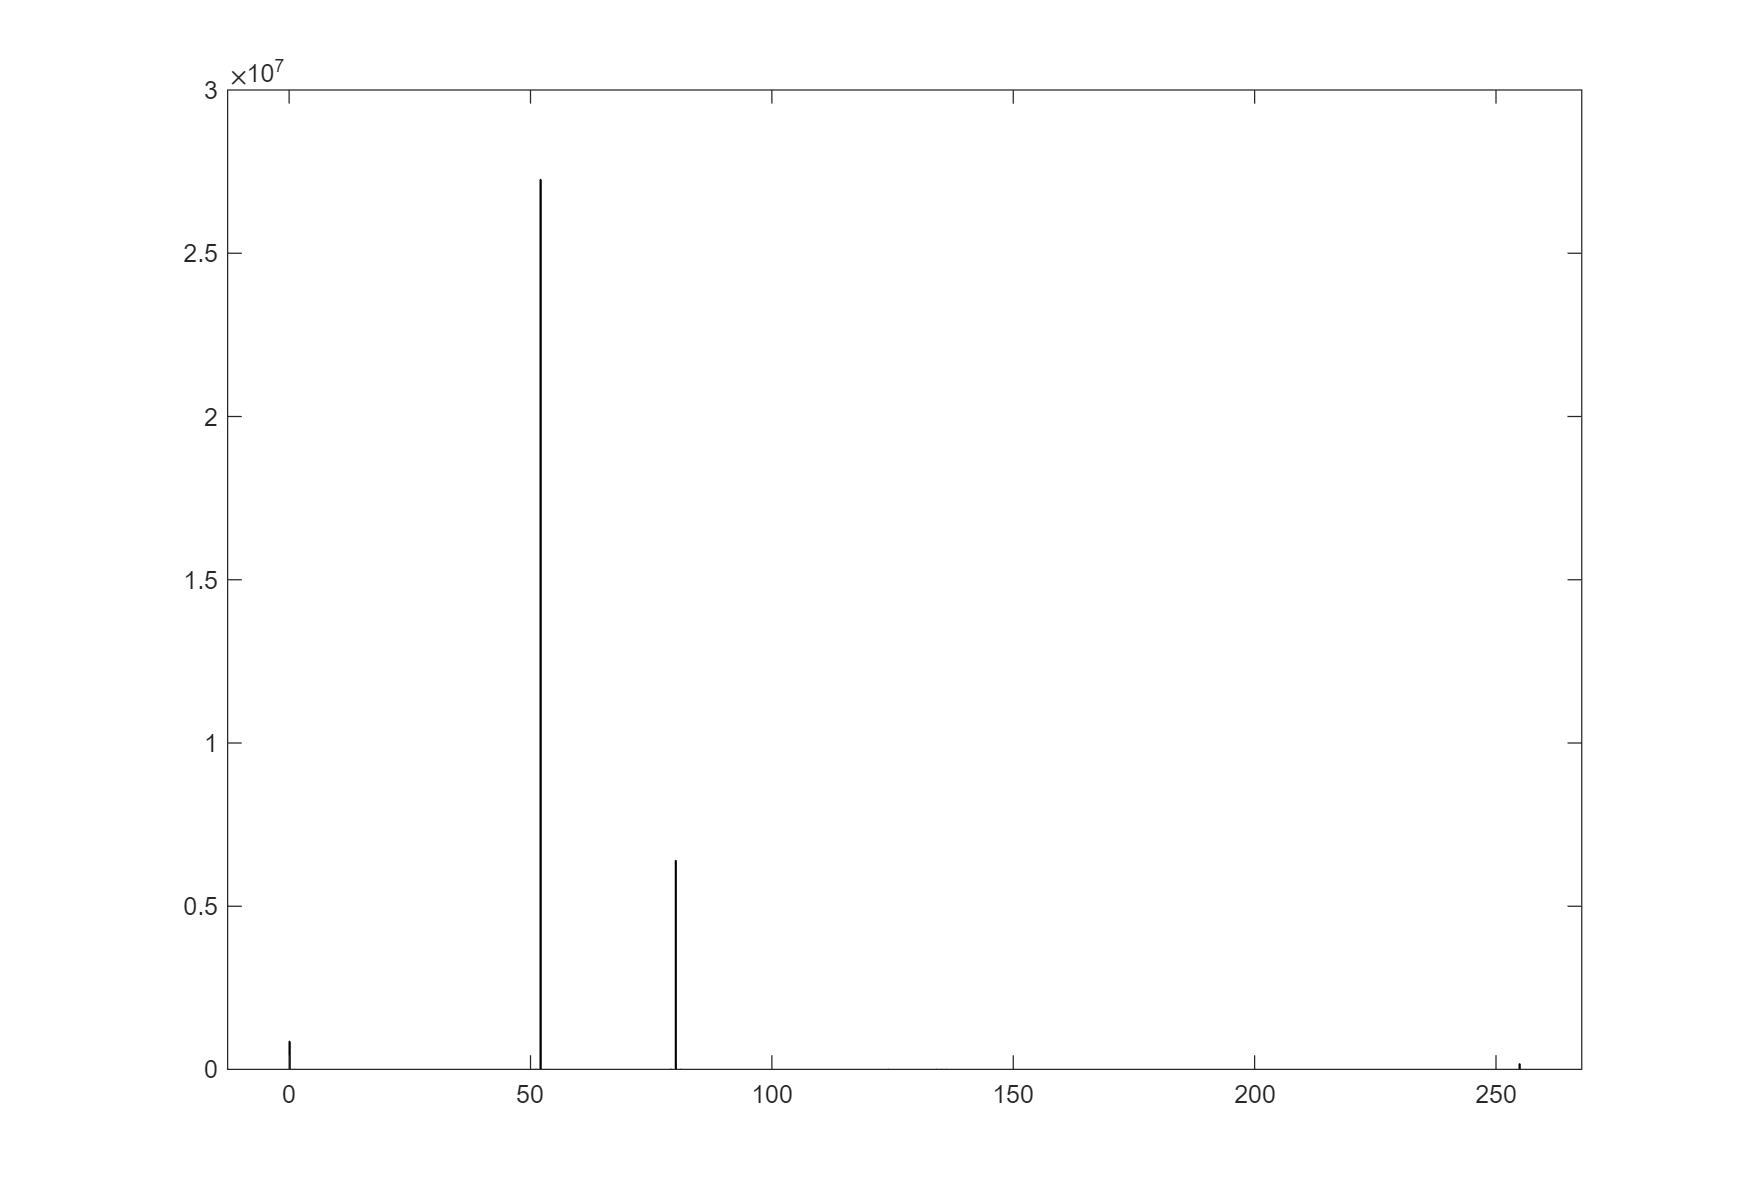


I=imnoise(I,"salt & pepper",0.01);
histogram(I)

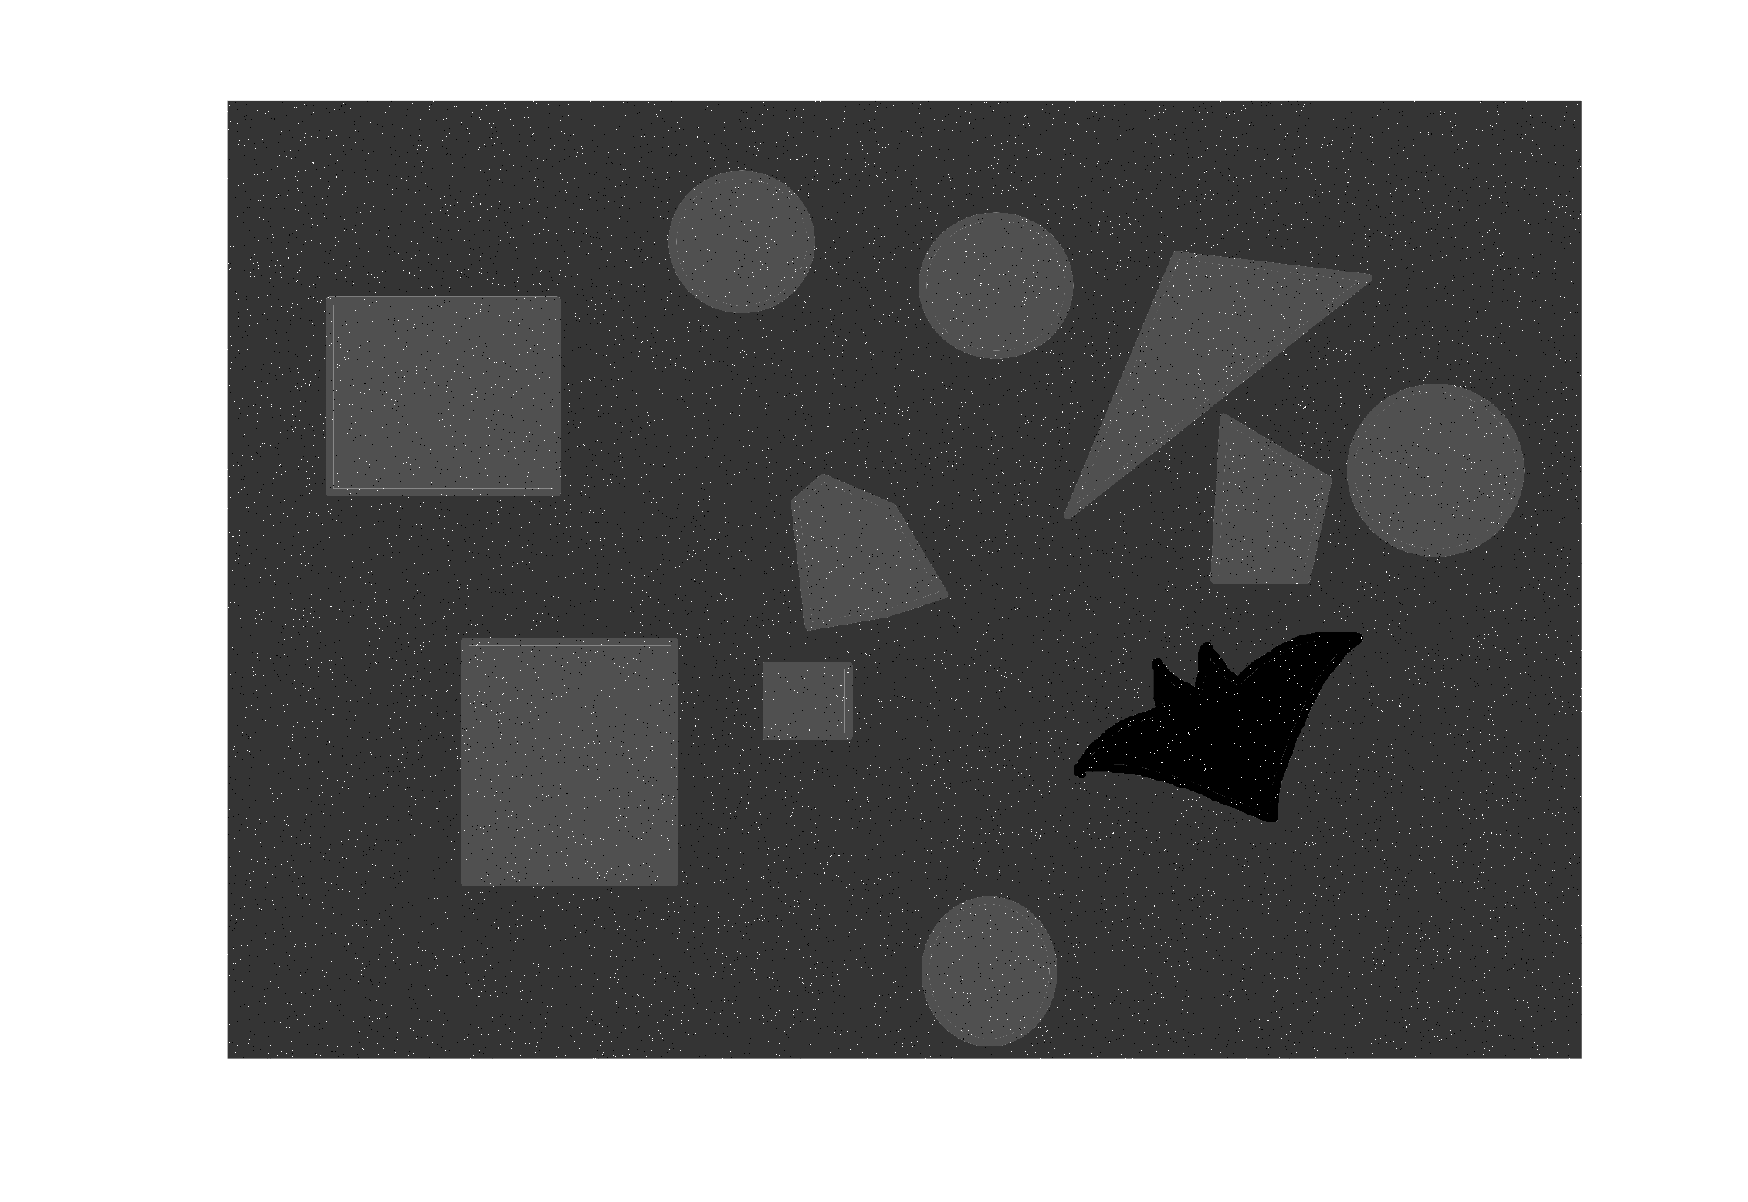

imshow(I);

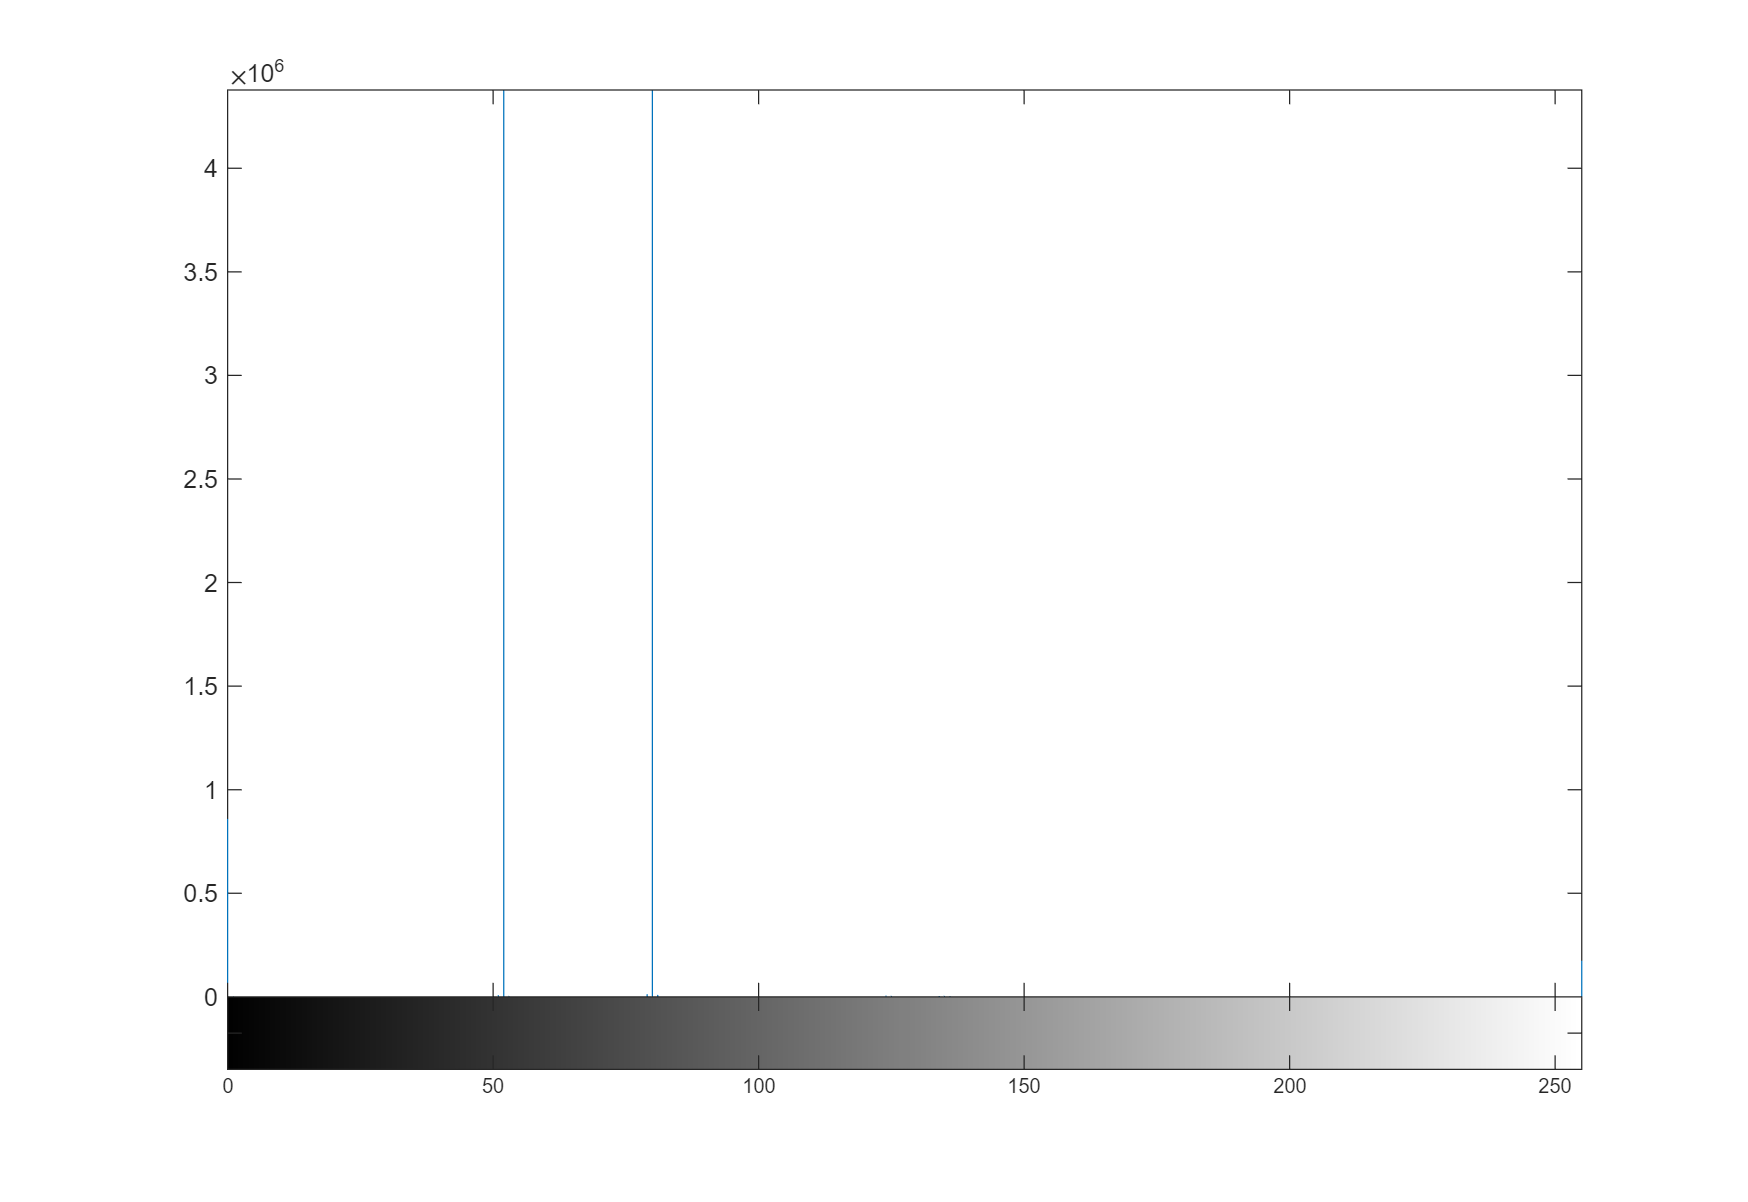

imhist(I);

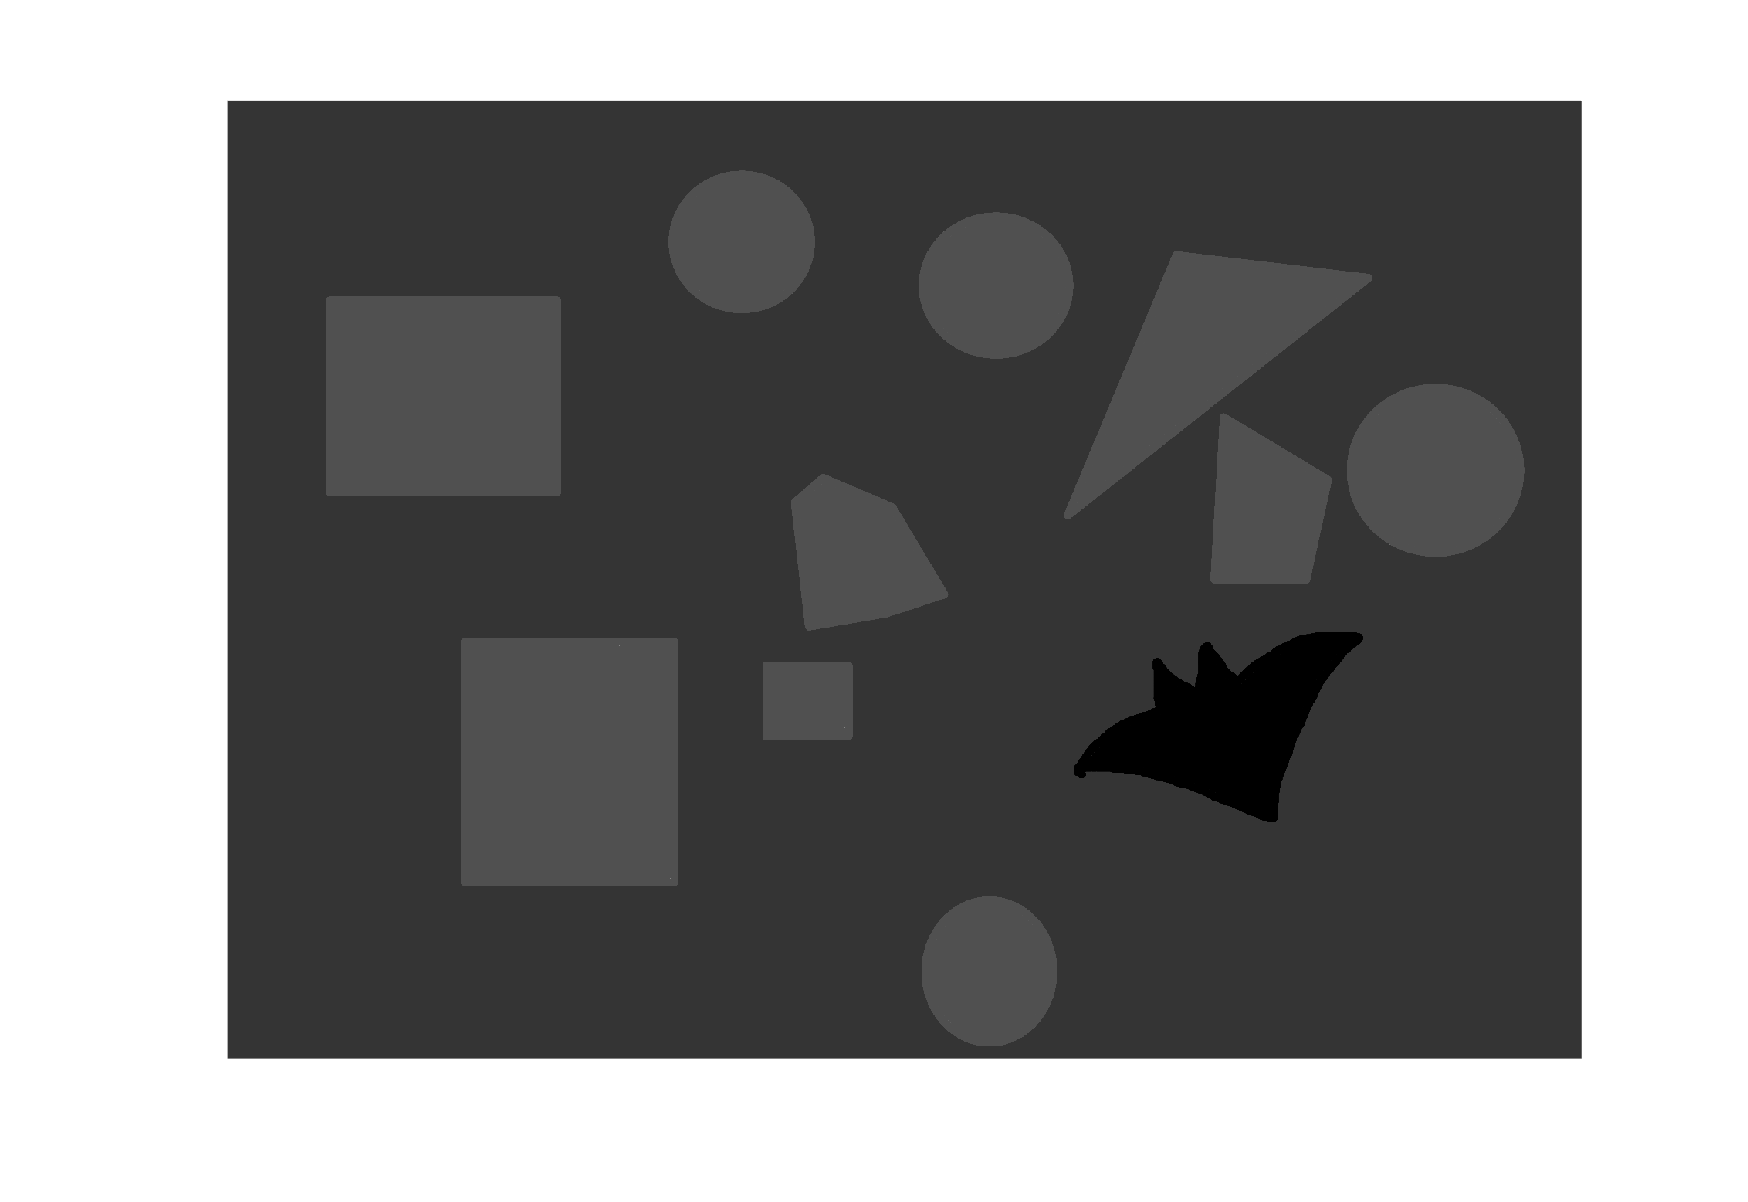


I = medfilt2(I,"symmetric");
imshow(I);

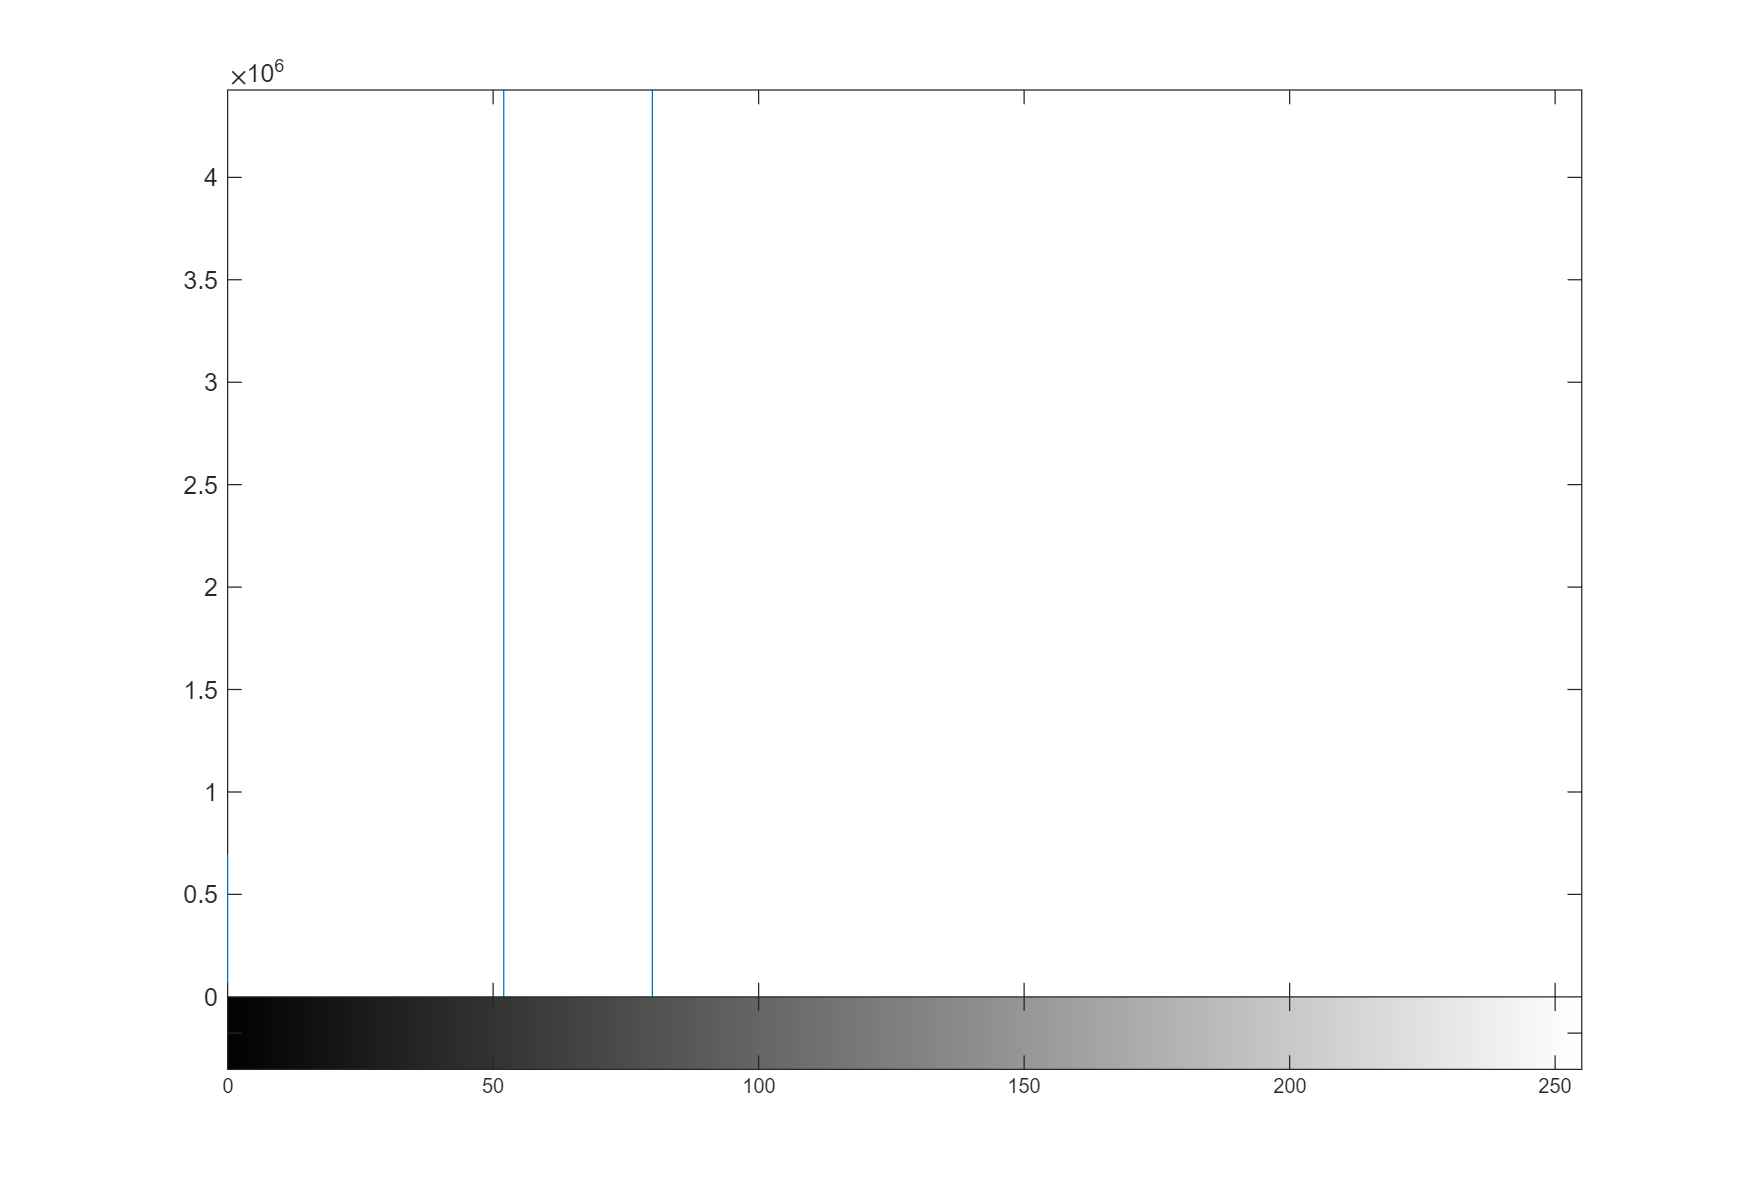

imhist(I);

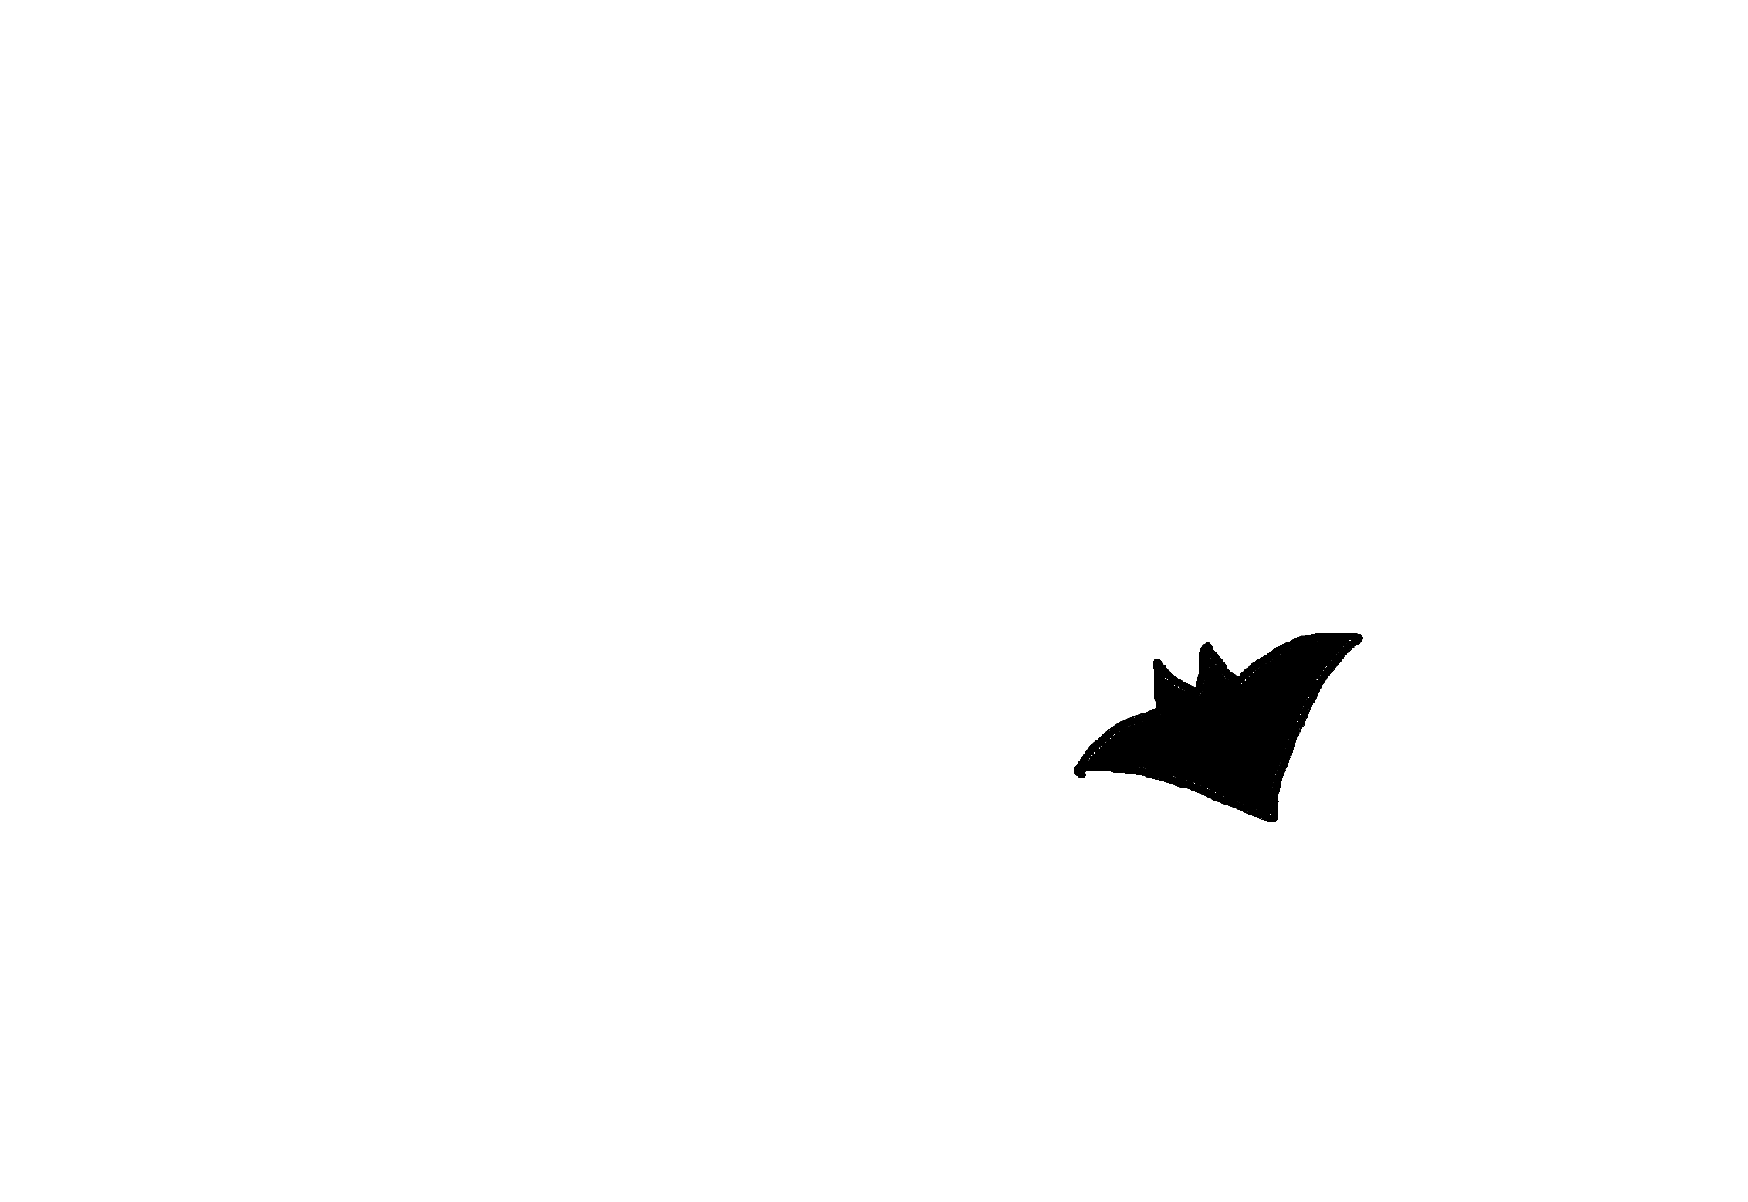


fil1=1/16*[1 2 1;2 4 2;1 2 1];
I=conv2(I,fil1);
imshow(I);

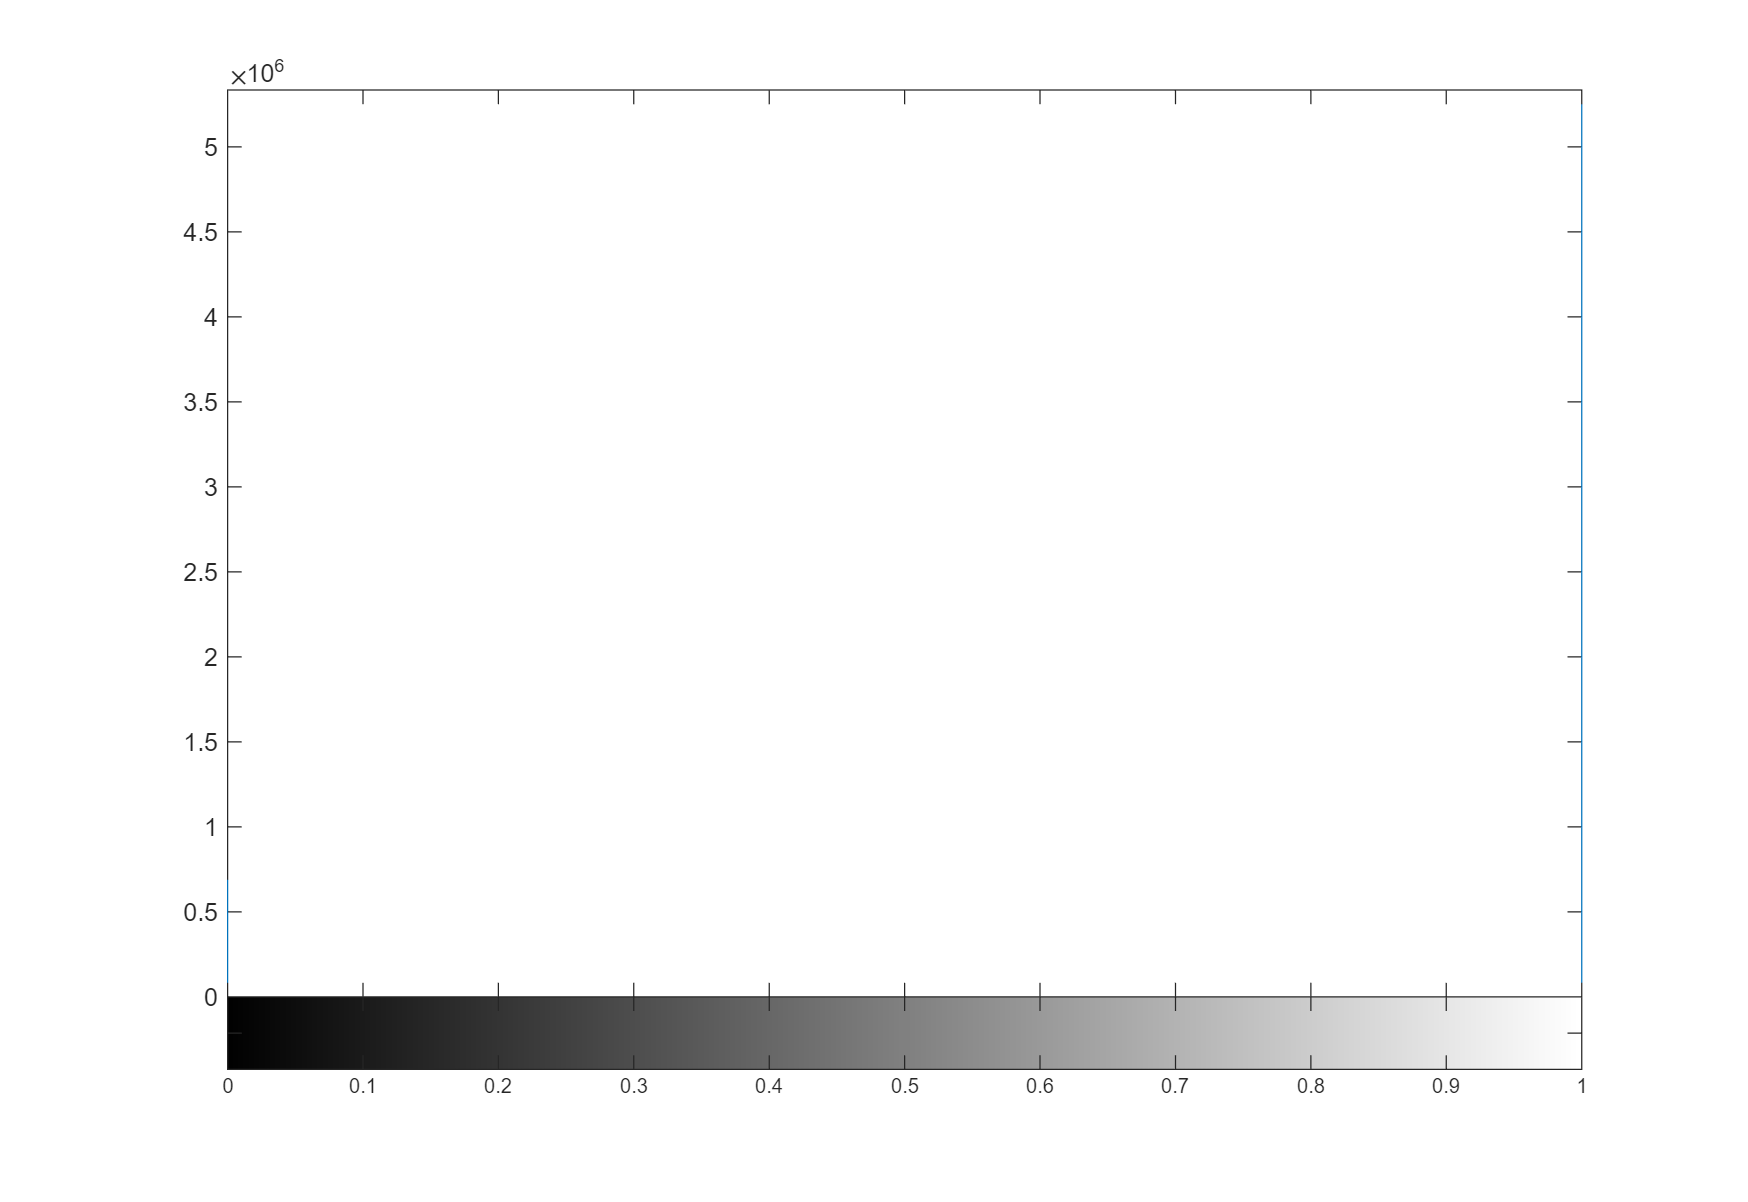

imhist(I);

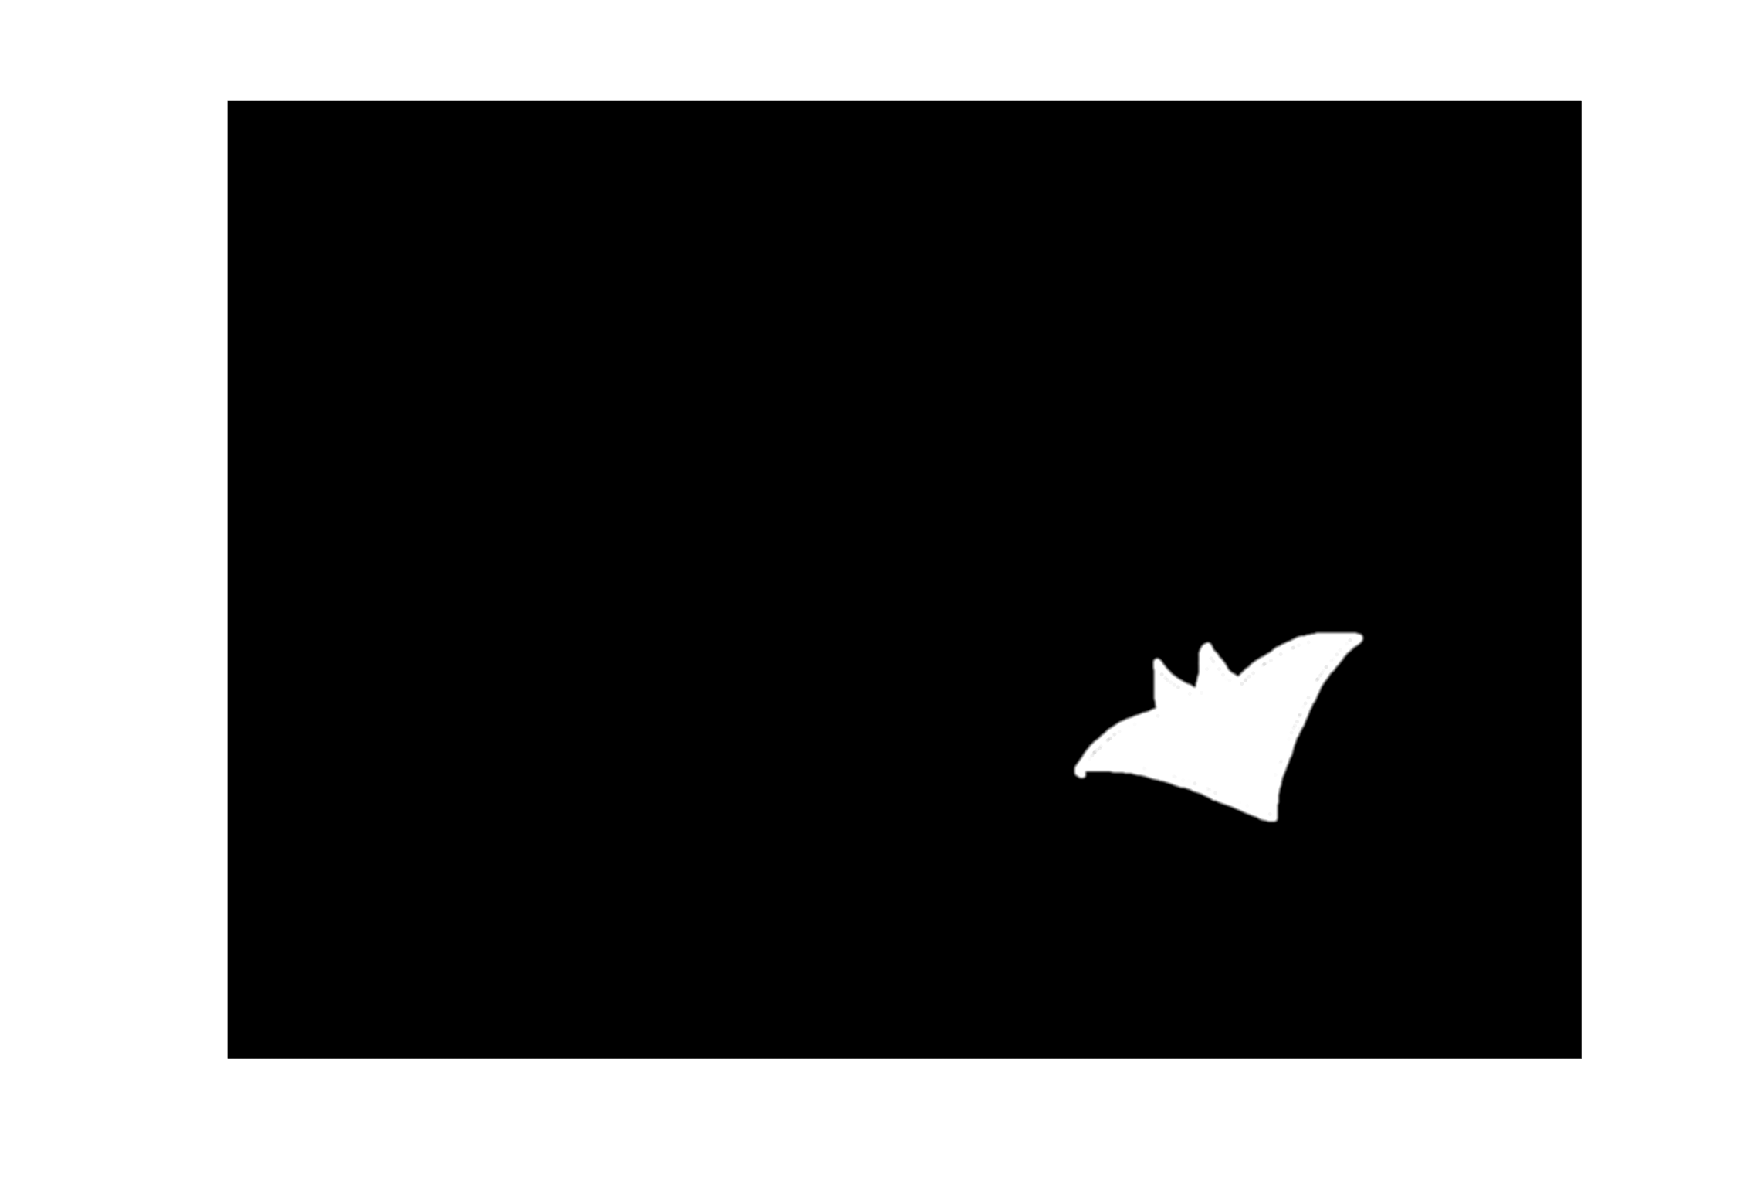


I=1-imbinarize(I);

% mask=[1 1 1 1 1 1 1;1 1 1 1 1 1 1;1 1 1 1 1 1 1];
% I=conv2(I,mask/sum(mask));

mask=fspecial("disk",10);
I=imfilter(I,mask,"replicate");
I=mat2gray(I);
imshow(I)

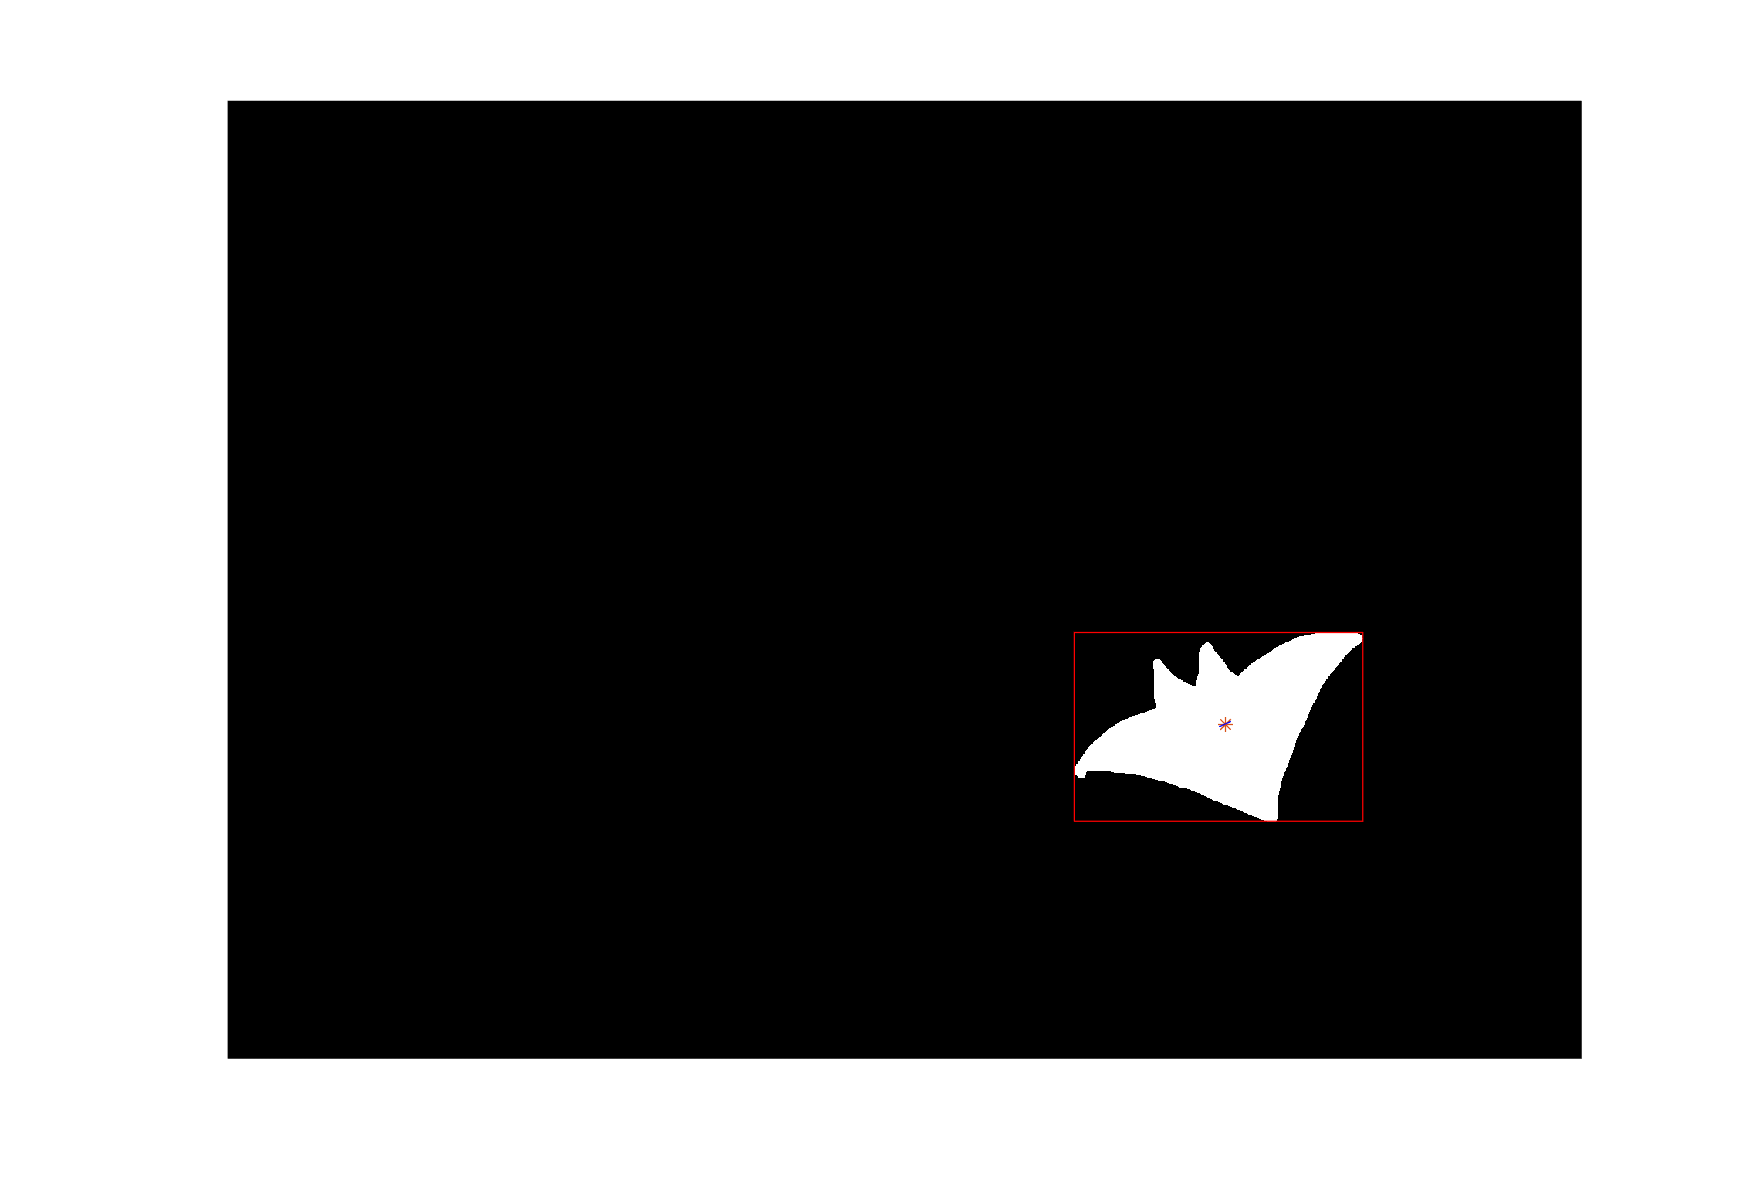

I=imbinarize(I,"global");

I=bwlabel(I);
feats=regionprops(I,'all');
imshow(I);hold on
rectangle('Position',feats.BoundingBox,'EdgeColor','red');
centroids =cat(1,feats.Centroid);
plot(centroids(:,1),centroids(:,2),'b*');

x=feats.Centroid(1,1);
y=feats.Centroid(1,2);

plot(x,y,"*");
a1=tan((feats.Orientation)*pi/180);
b1=y-a1*x;
x1=x-30;
x2=x+30;
y1=a1*x1+b1;
y2=a1*x2+b1;
plot([x1 x2],[y2 y1],'-b')
hold off

Task 1.4

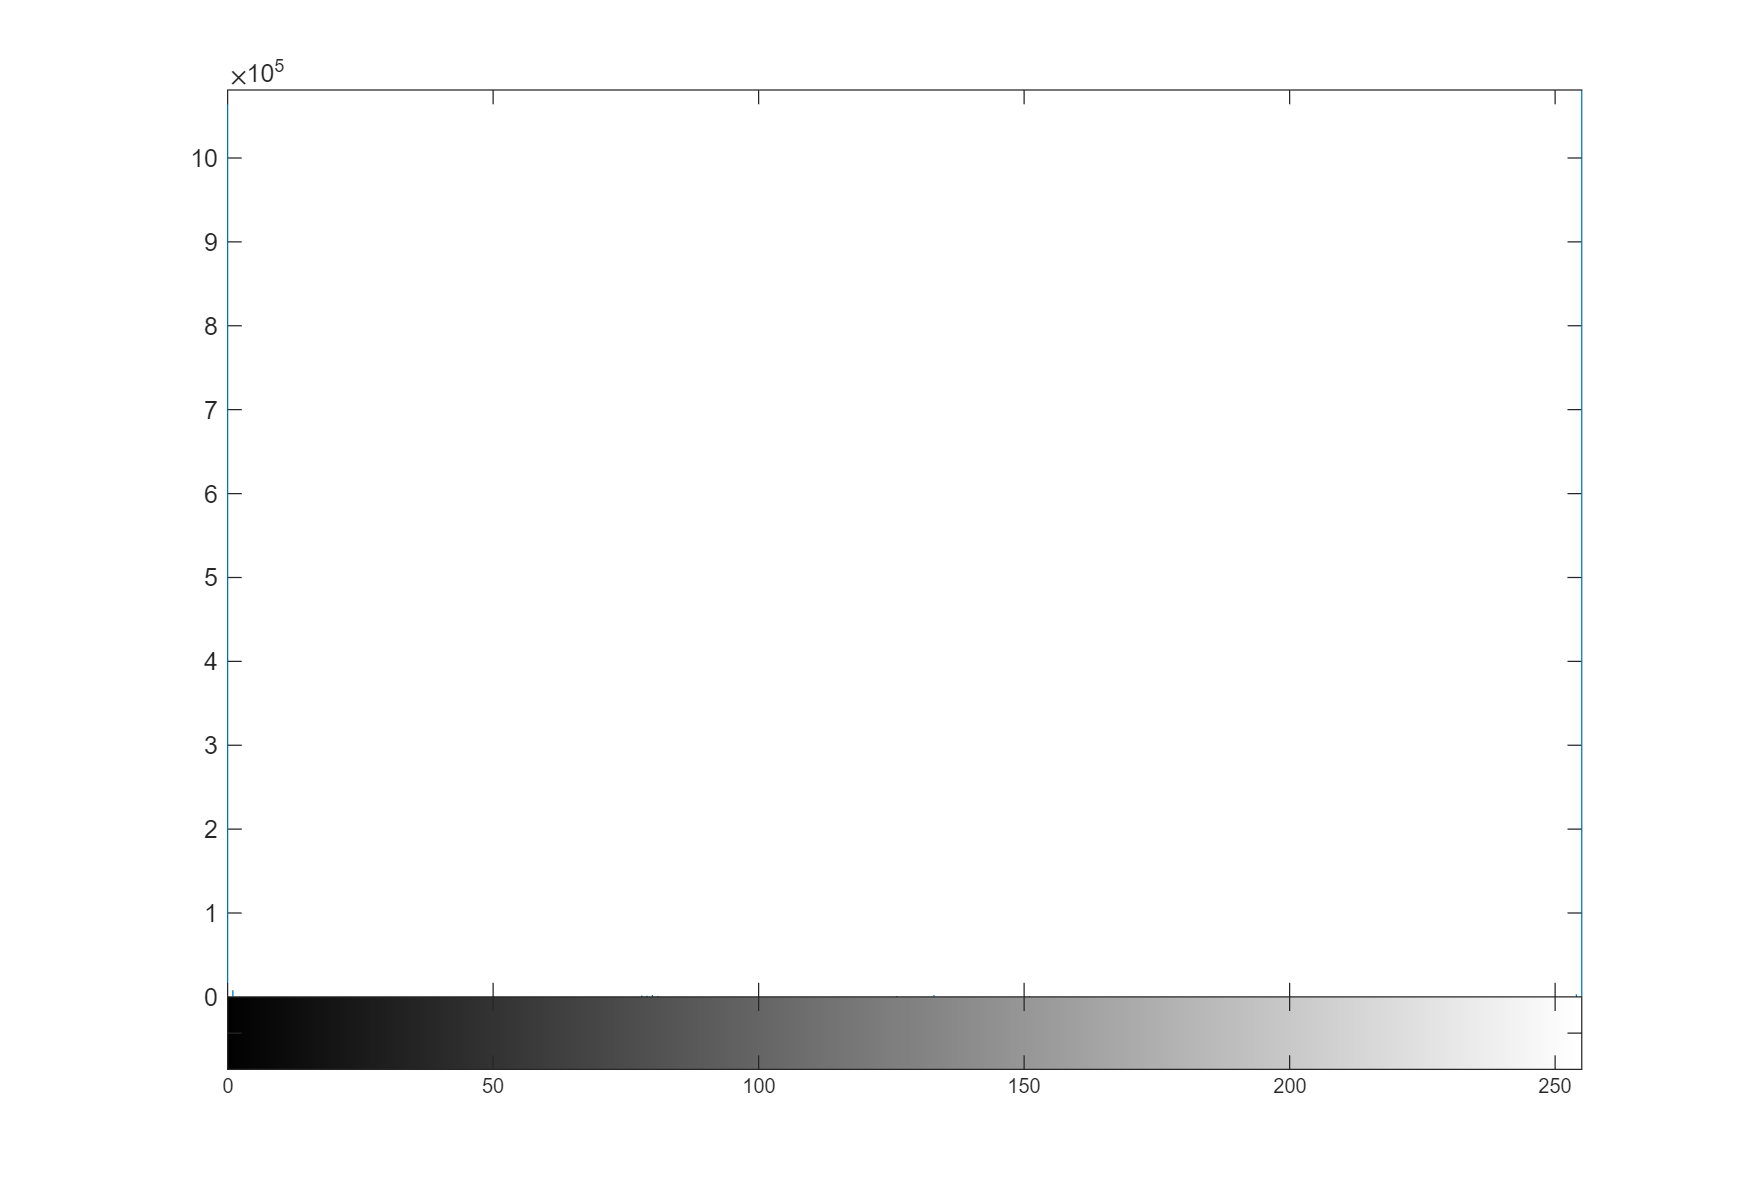

I=imread("image3.jpg");
I=rgb2gray(I);
imhist(I);

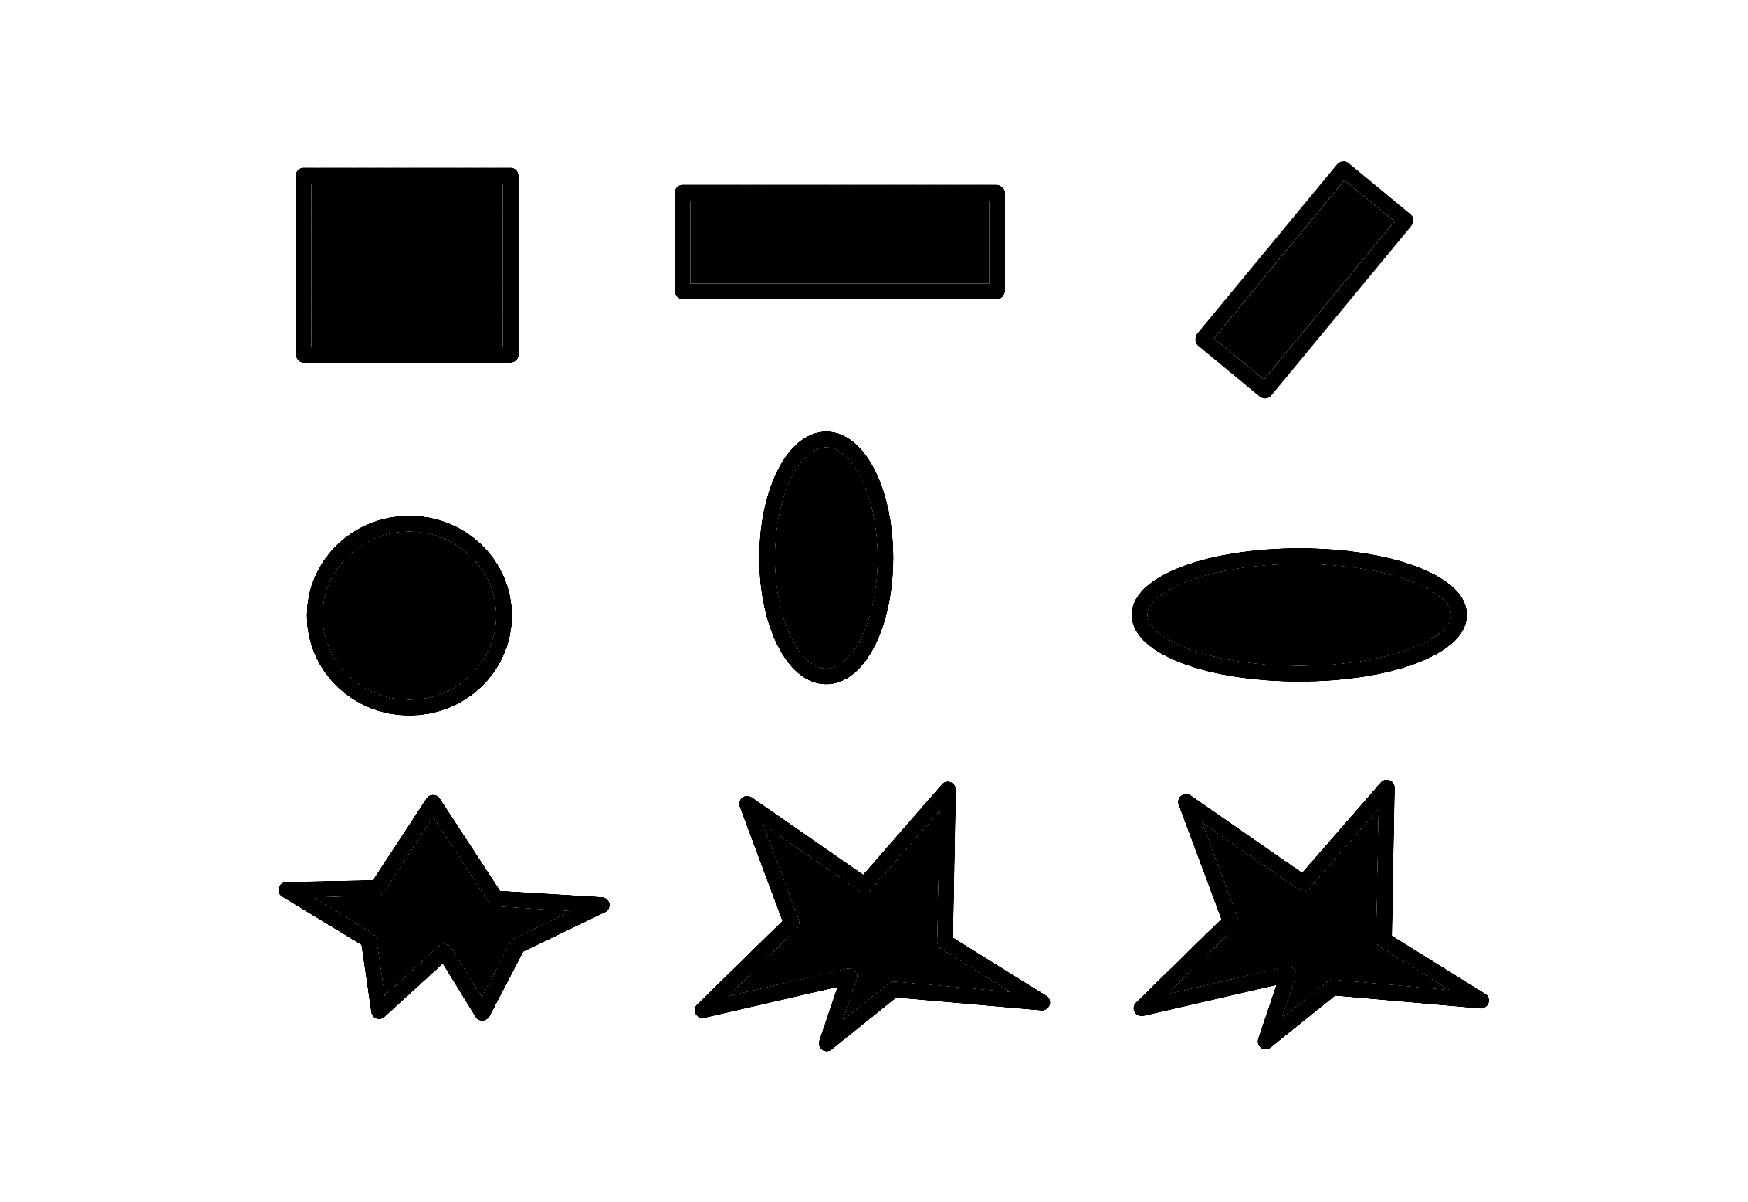

imshow(I);

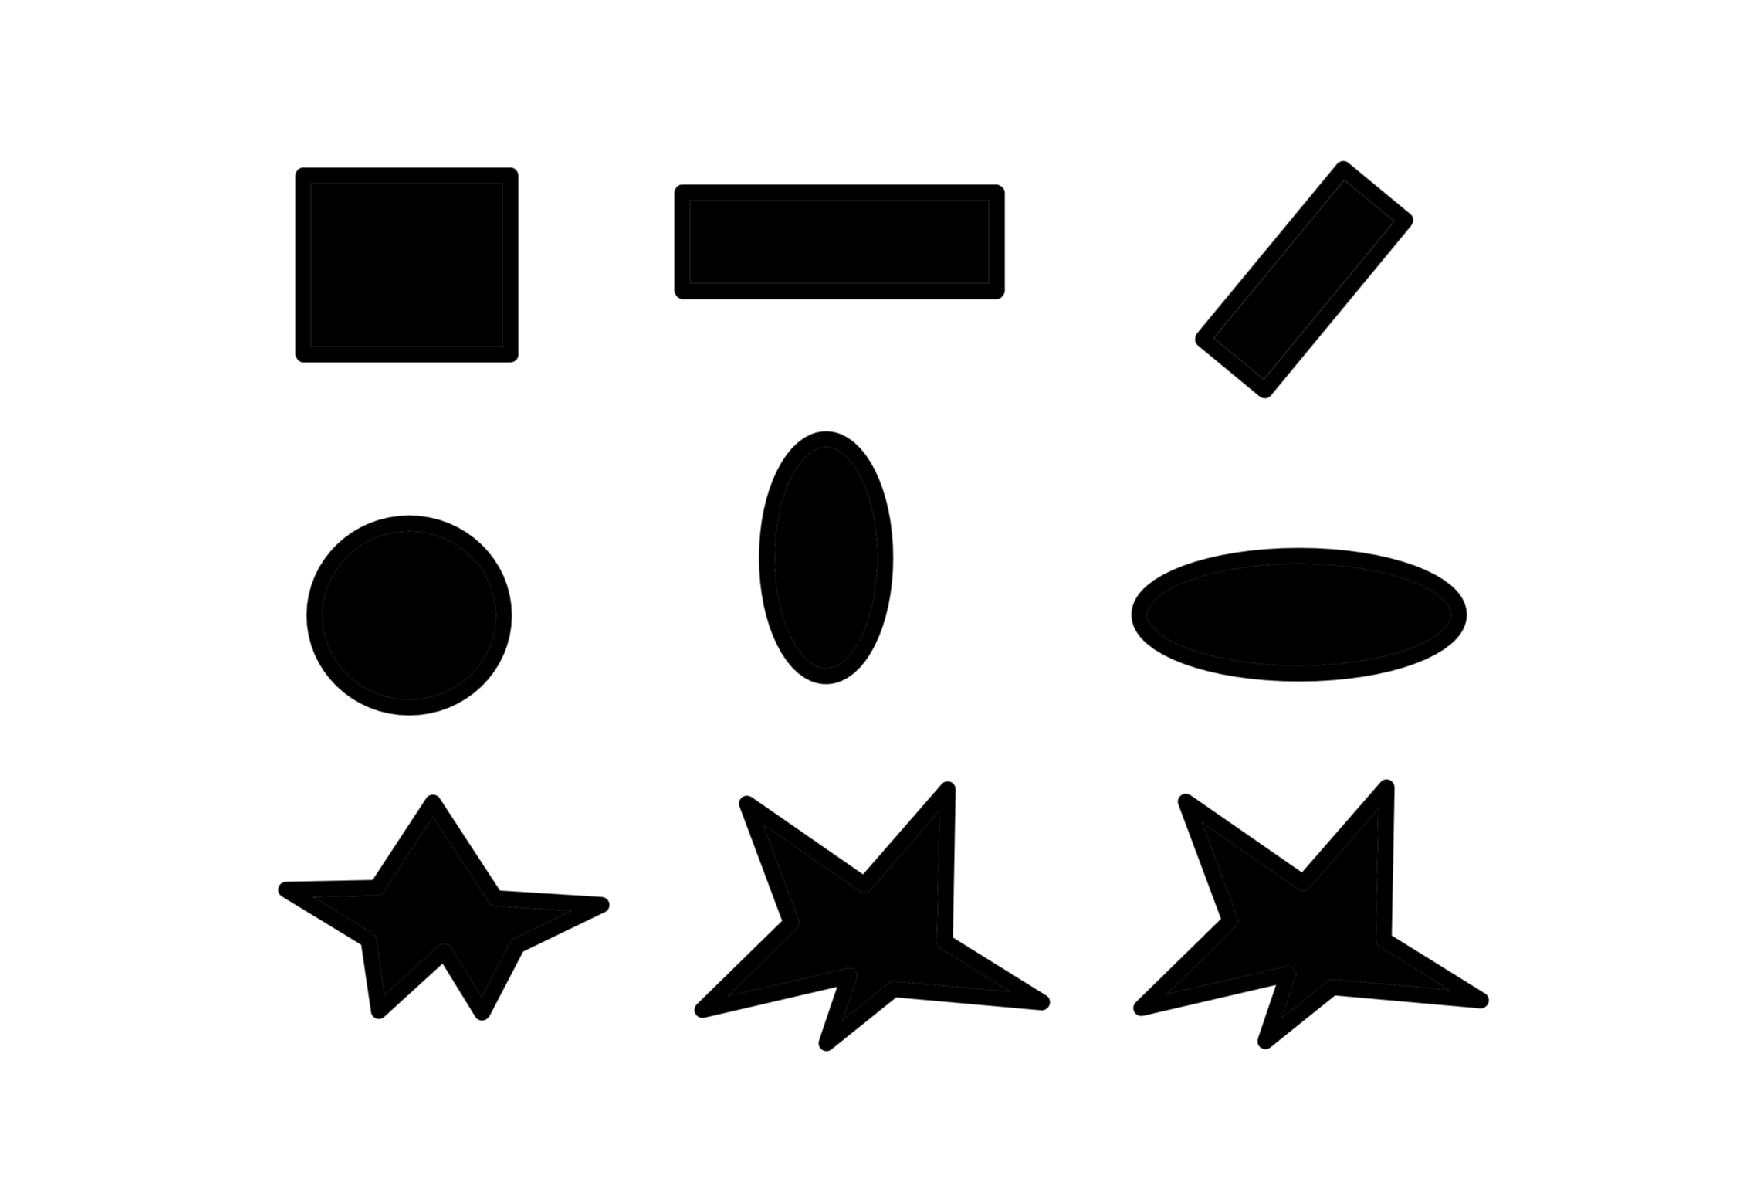

mask=fspecial("average",4);
I=imfilter(I,mask,"replicate");
I=mat2gray(I);
imshow(I)

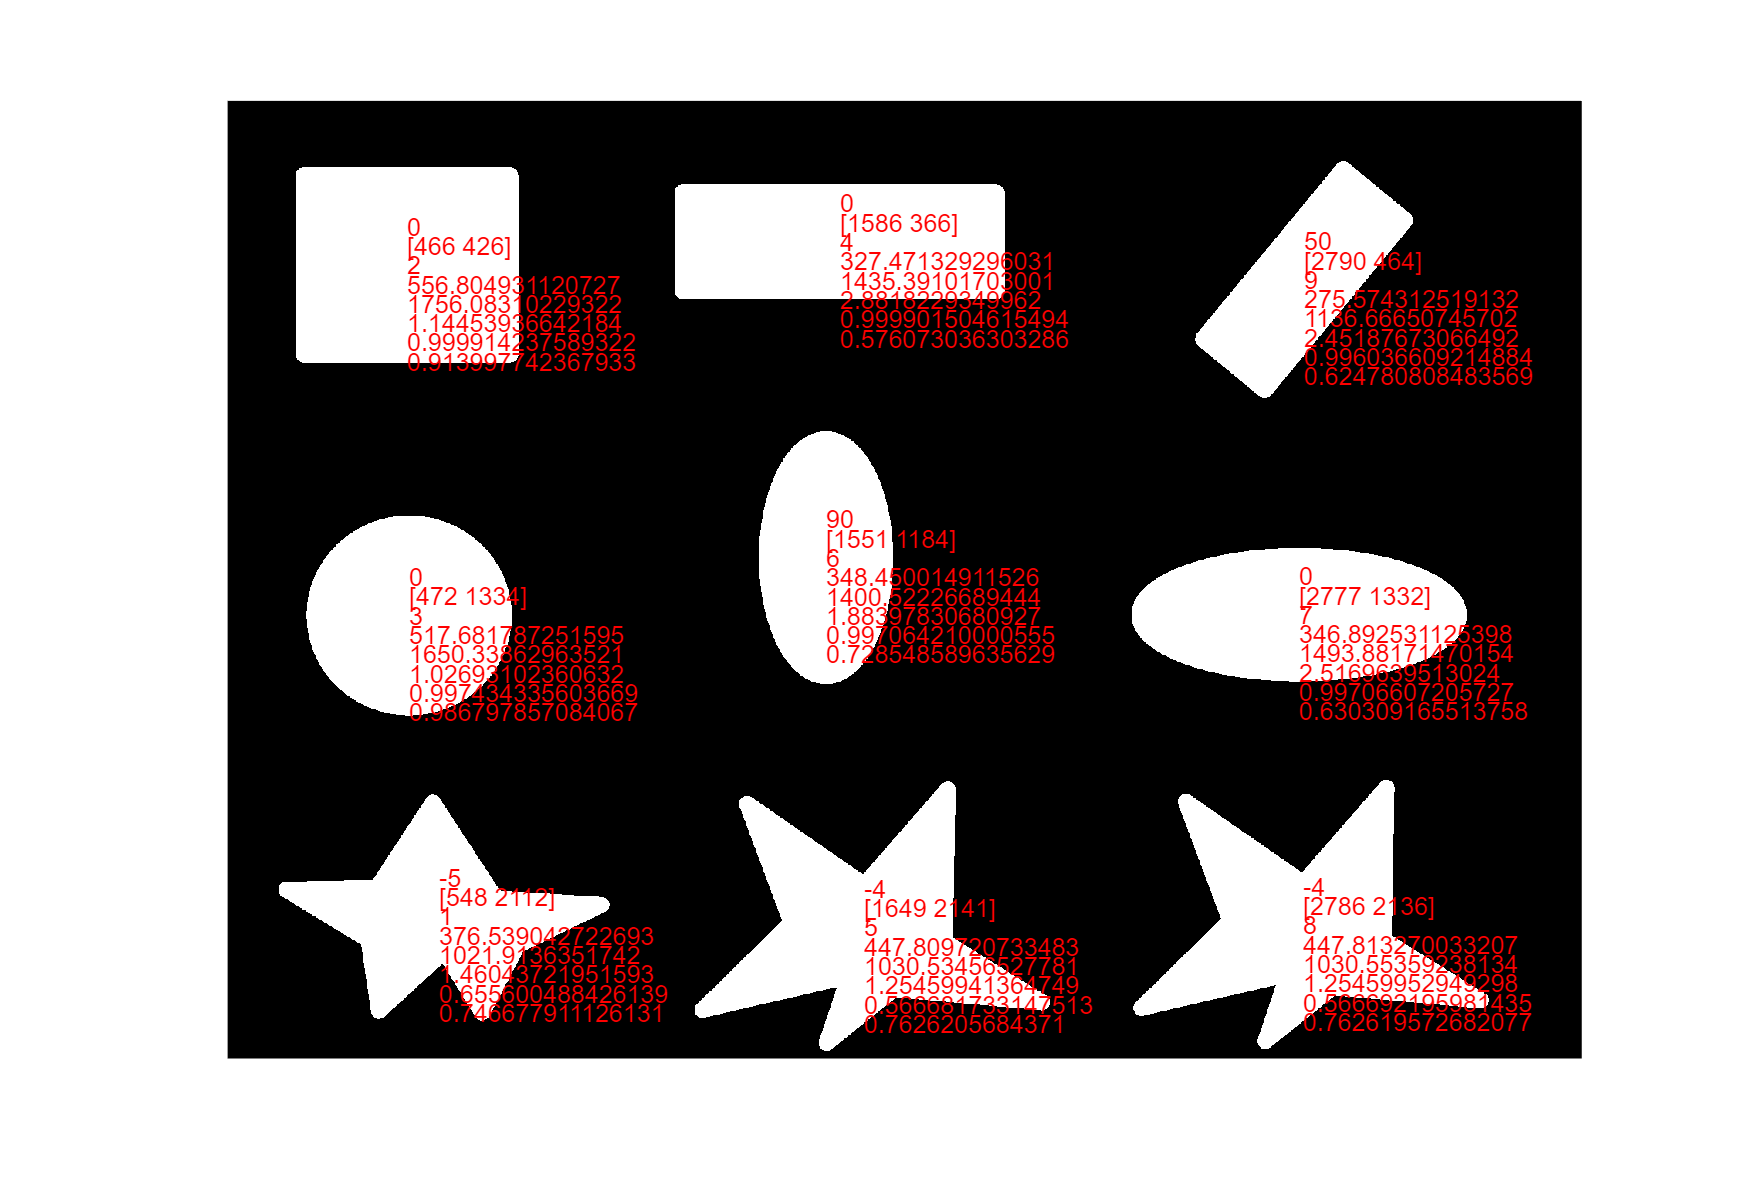

I=1-imbinarize(I);
imshow(I);hold on
[label, num]=bwlabel(I);
feats=regionprops(label,'all');hold off

for i=1:num

    roundness(i)=(4.*feats(i).Area)/(pi*feats(i).MajorAxisLength);
    form_factor(i)=(4*pi.*feats(i).Area)/(feats(i).Perimeter);
    aspec_ratio(i)=feats(i).MajorAxisLength/feats(i).MinorAxisLength;
    solidity(i)=feats(i).Area/feats(i).ConvexArea;
    compactness(i)=sqrt(4*feats(i).Area/pi)/feats(i).MajorAxisLength;

    text(feats(i).Centroid(1),feats(i).Centroid(2)-100,mat2str(round(feats(i).Orientation)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)-50,mat2str(round(feats(i).Centroid)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2),mat2str(i),'Color','r');
    
    text(feats(i).Centroid(1),feats(i).Centroid(2)+50,mat2str(roundness(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+100,mat2str(form_factor(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+150,mat2str(aspec_ratio(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+200,mat2str(solidity(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+250,mat2str(compactness(i)),'Color','r')


end

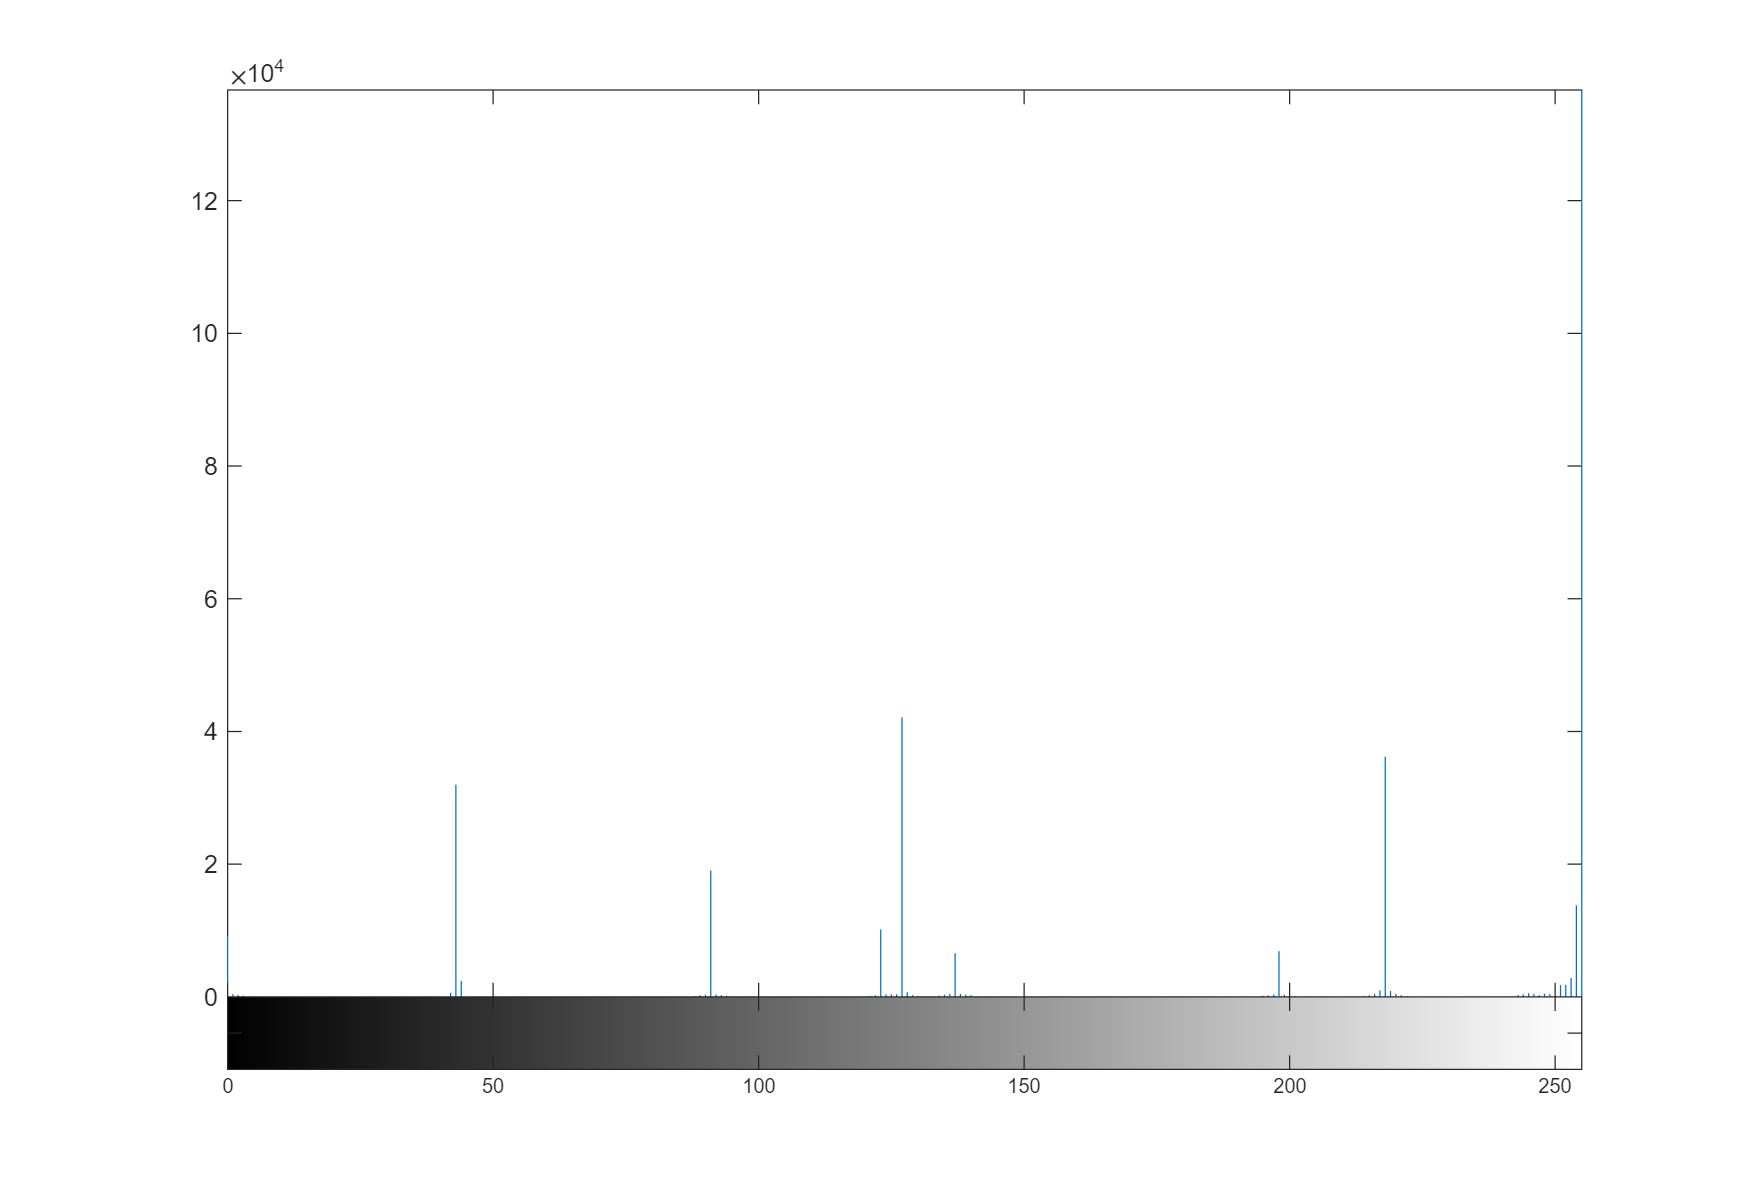

I=imread("image4.jpg");
I=rgb2gray(I);
imhist(I);

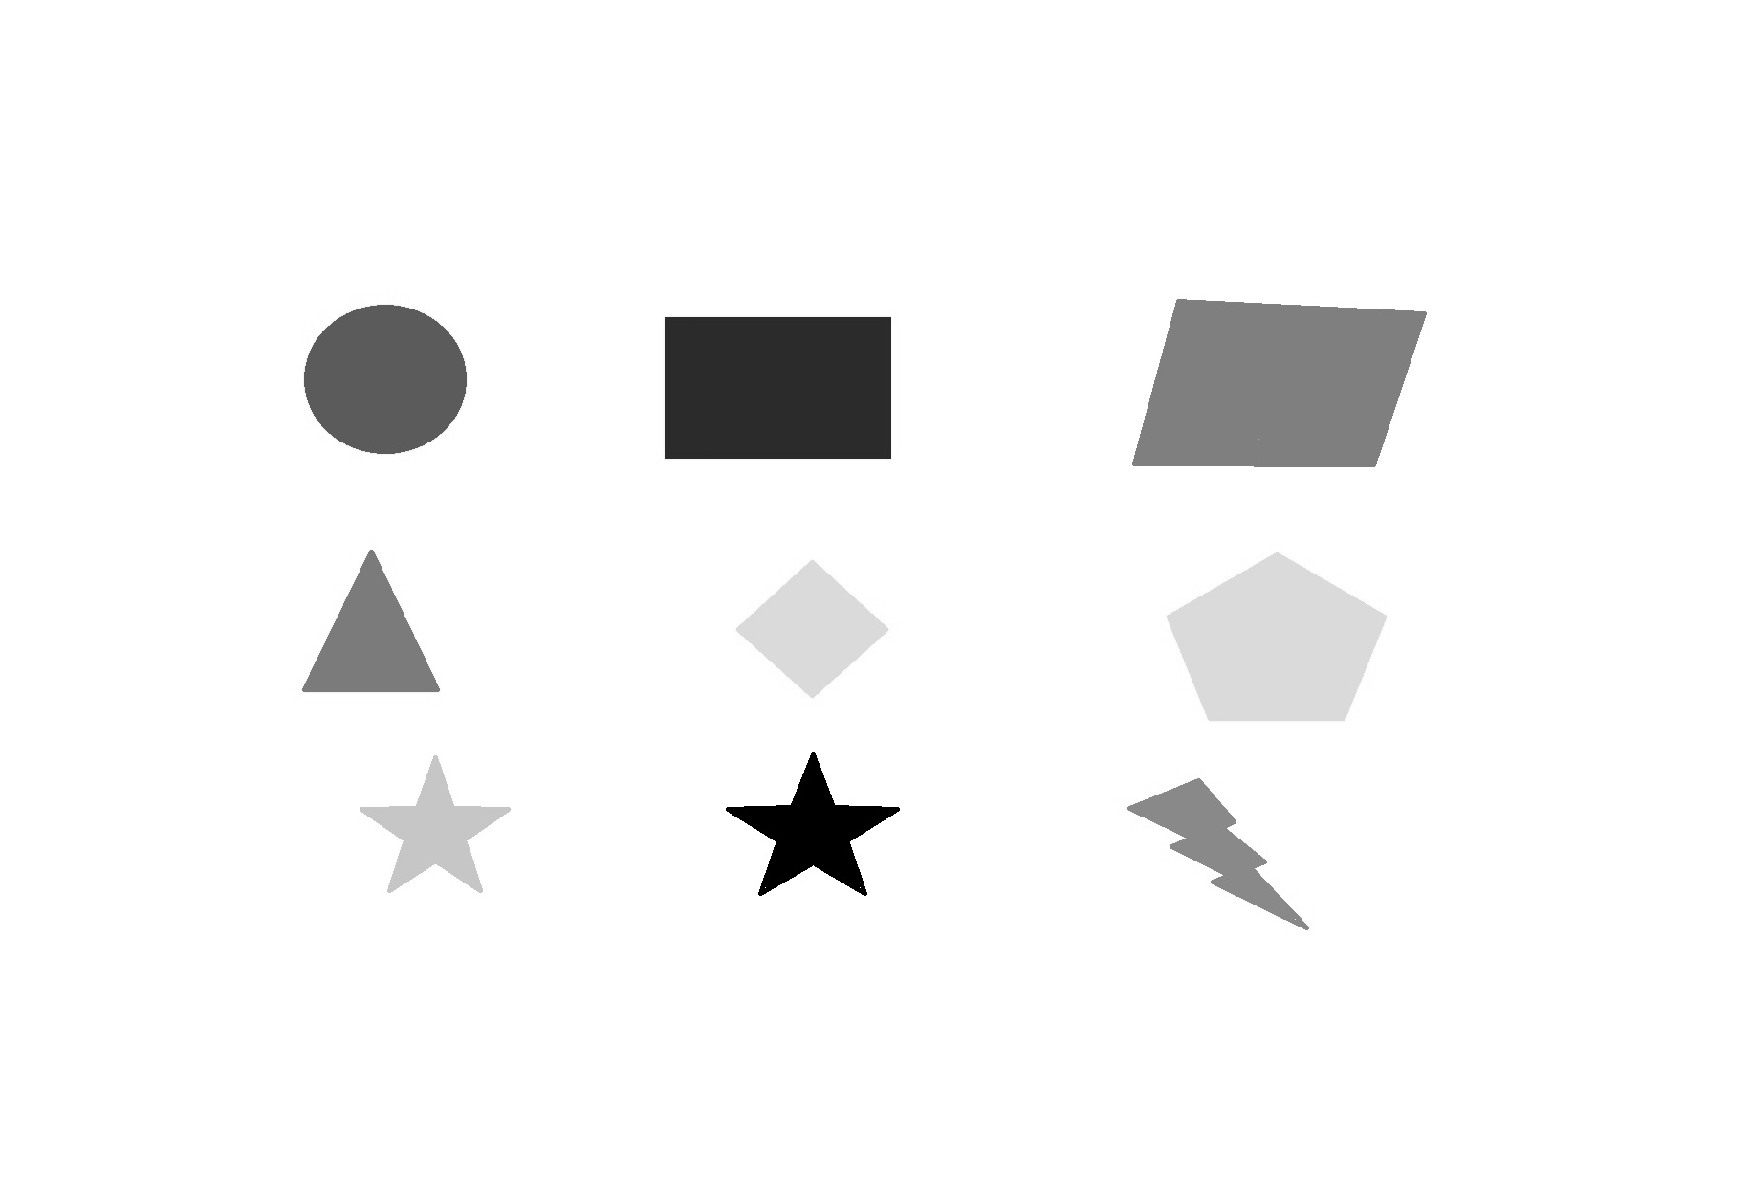

imshow(I);

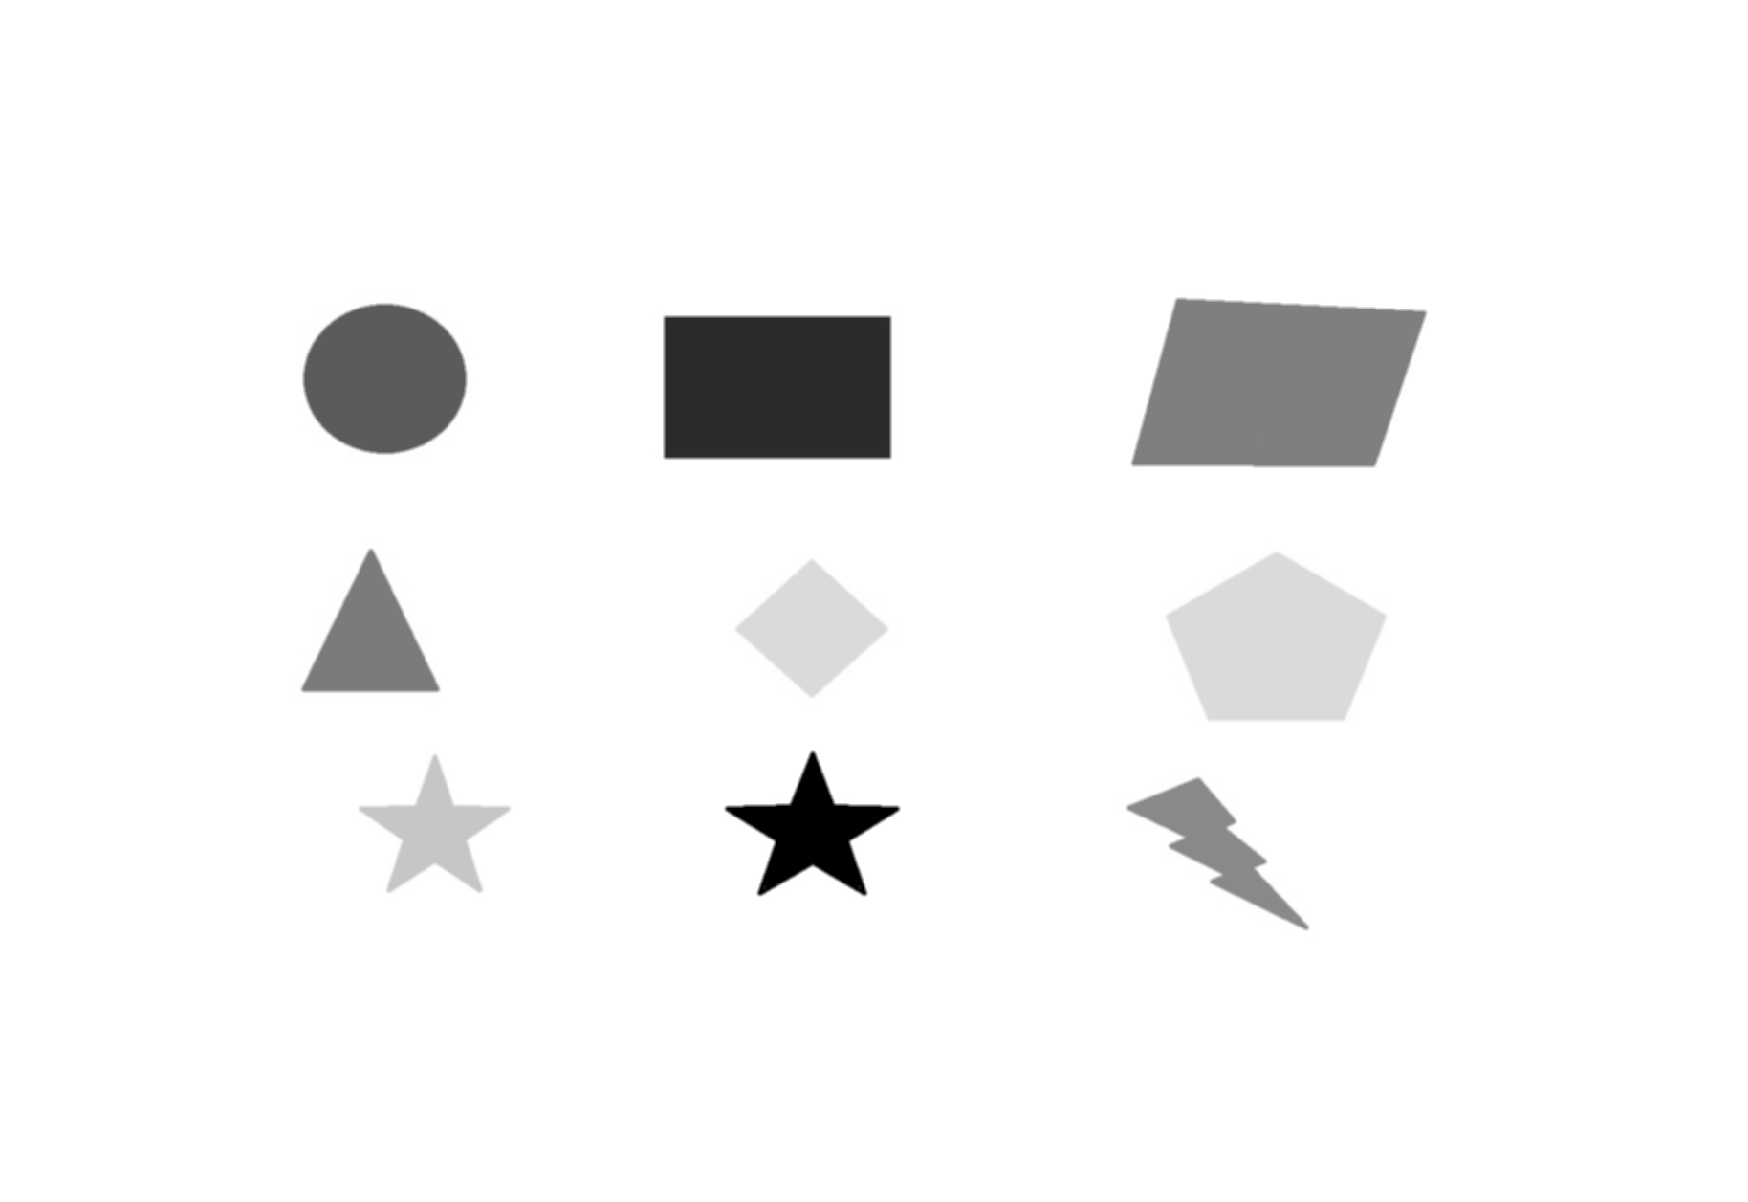

mask=fspecial("average",4);
I=imfilter(I,mask,"replicate");
I=mat2gray(I);
imshow(I)

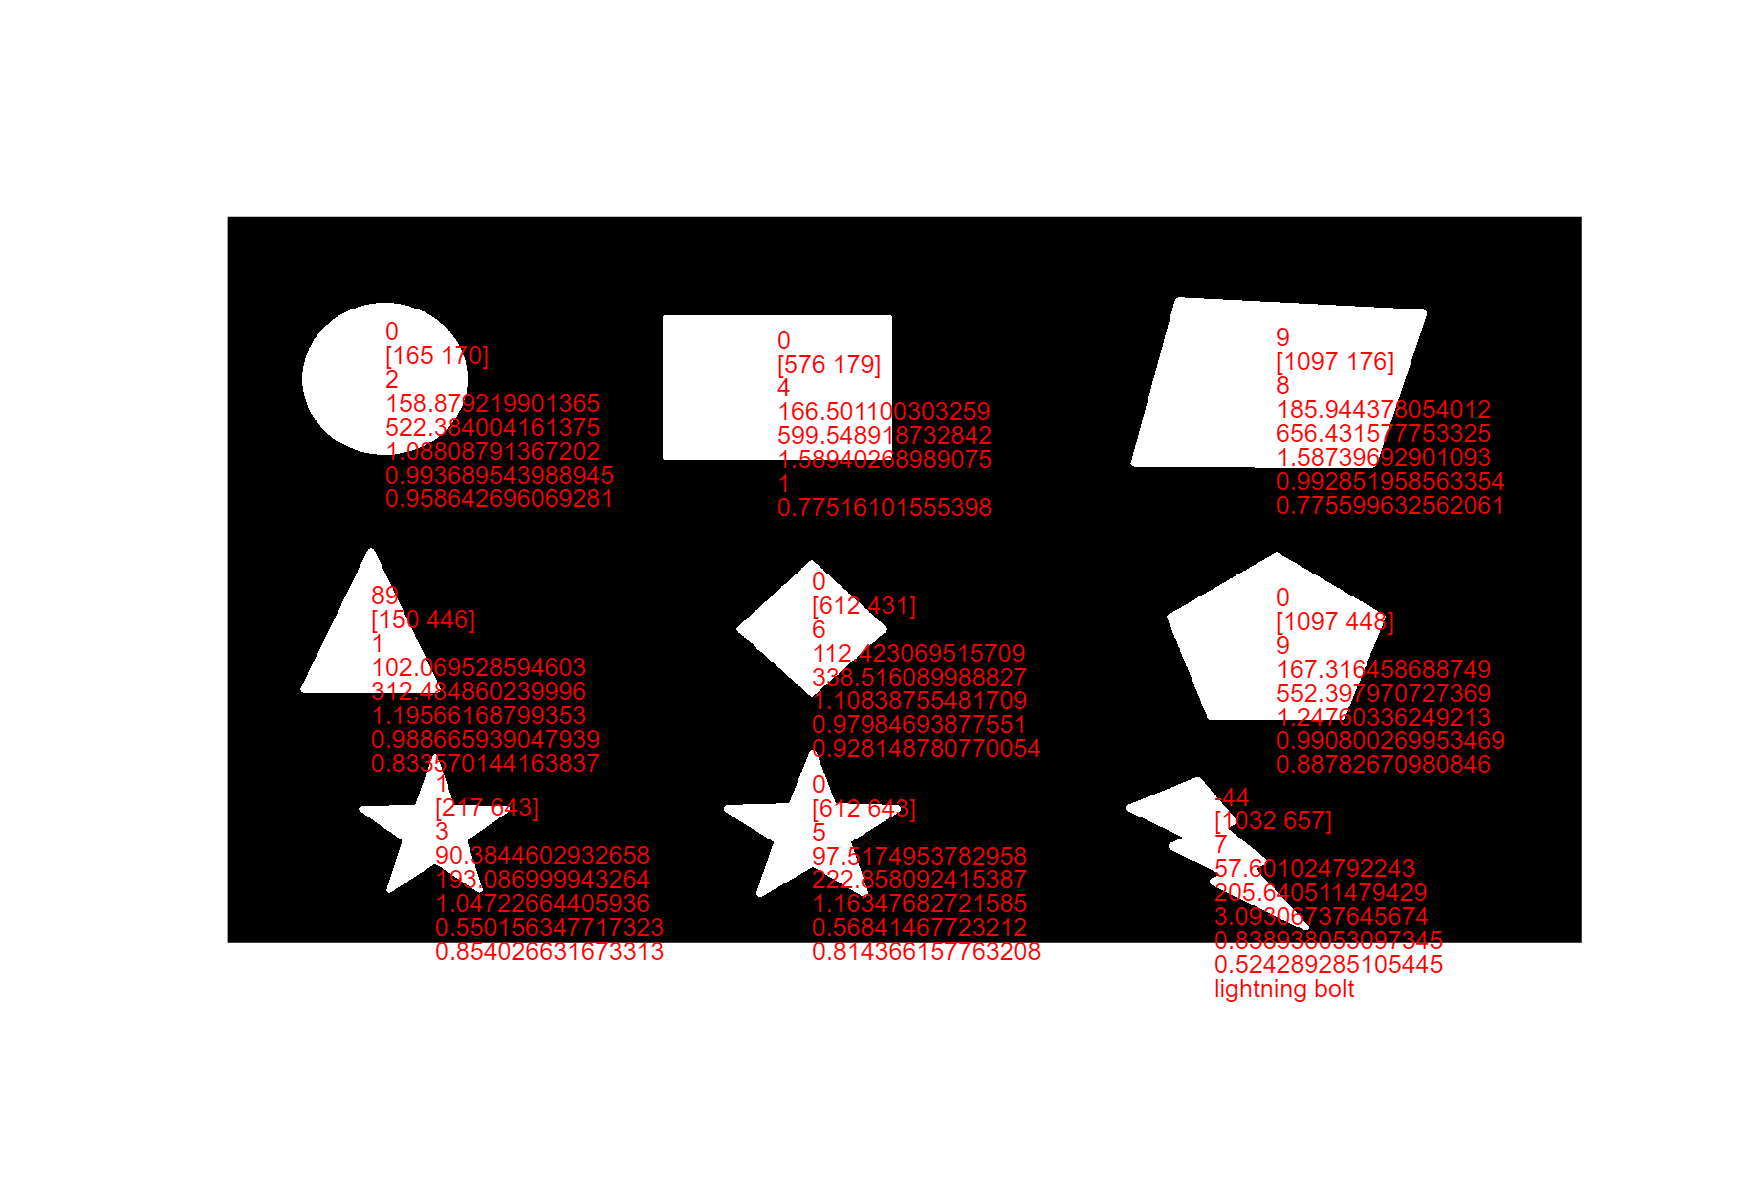

I=1-im2bw(I,0.9);
imshow(I);hold on
[label, num]=bwlabel(I);
feats=regionprops(label,'all');hold off

for i=1:num

    roundness(i)=(4.*feats(i).Area)/(pi*feats(i).MajorAxisLength);
    form_factor(i)=(4*pi.*feats(i).Area)/(feats(i).Perimeter);
    aspec_ratio(i)=feats(i).MajorAxisLength/feats(i).MinorAxisLength;
    solidity(i)=feats(i).Area/feats(i).ConvexArea;
    compactness(i)=sqrt(4*feats(i).Area/pi)/feats(i).MajorAxisLength;

    text(feats(i).Centroid(1),feats(i).Centroid(2)-100*0.5,mat2str(round(feats(i).Orientation)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)-50*0.5,mat2str(round(feats(i).Centroid)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2),mat2str(i),'Color','r');
    
    text(feats(i).Centroid(1),feats(i).Centroid(2)+50*0.5,mat2str(roundness(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+100*0.5,mat2str(form_factor(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+150*0.5,mat2str(aspec_ratio(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+200*0.5,mat2str(solidity(i)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)+250*0.5,mat2str(compactness(i)),'Color','r')
    if aspec_ratio(i)>3
        
        text(feats(i).Centroid(1), feats(i).Centroid(2)+300*0.5,'lightning bolt', 'Color', 'r');
    end
end

I=imread("image4.jpg");
I=rgb2gray(I);
imhist(I);

imshow(I);

mask=fspecial("average",4);
I=imfilter(I,mask,"replicate");
I=mat2gray(I);
imshow(I)

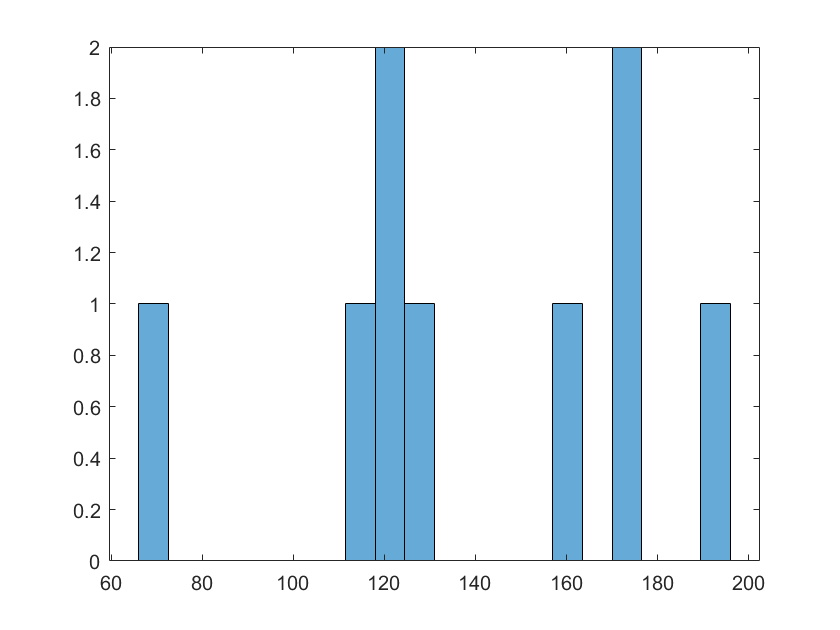

I=1-im2bw(I,0.9);
imshow(I);hold on
[label, num]=bwlabel(I);
feats=regionprops(label,'all');hold off

array=[feats.MinorAxisLength];
Min=min(array);
Max=max(array);
Mean=mean(array);
Std=std(array);
figure('name','histogram for min Feret diameter'),histogram(array,20);

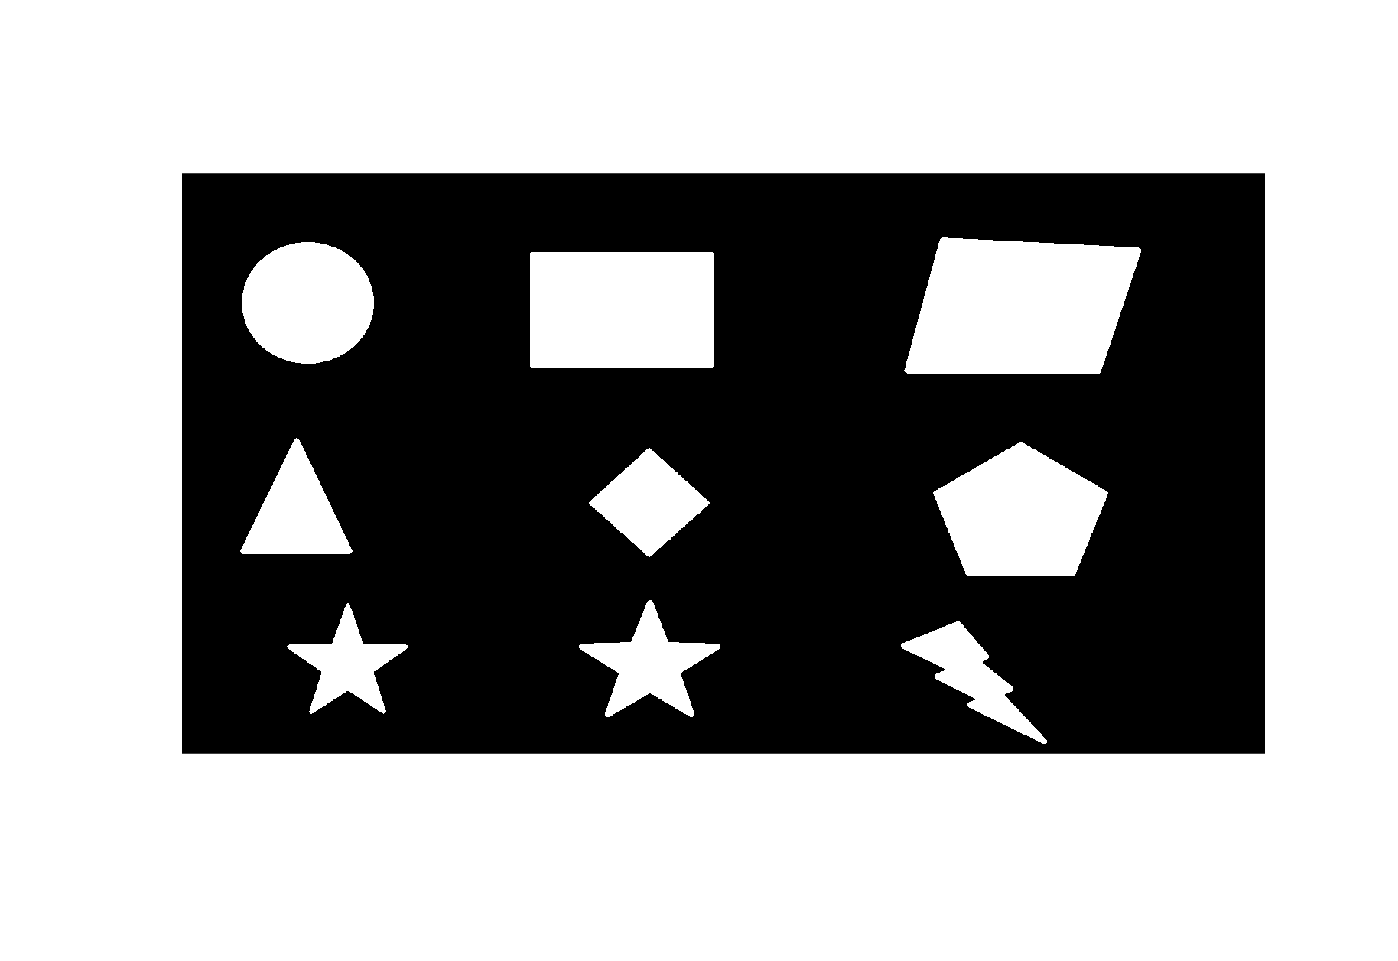

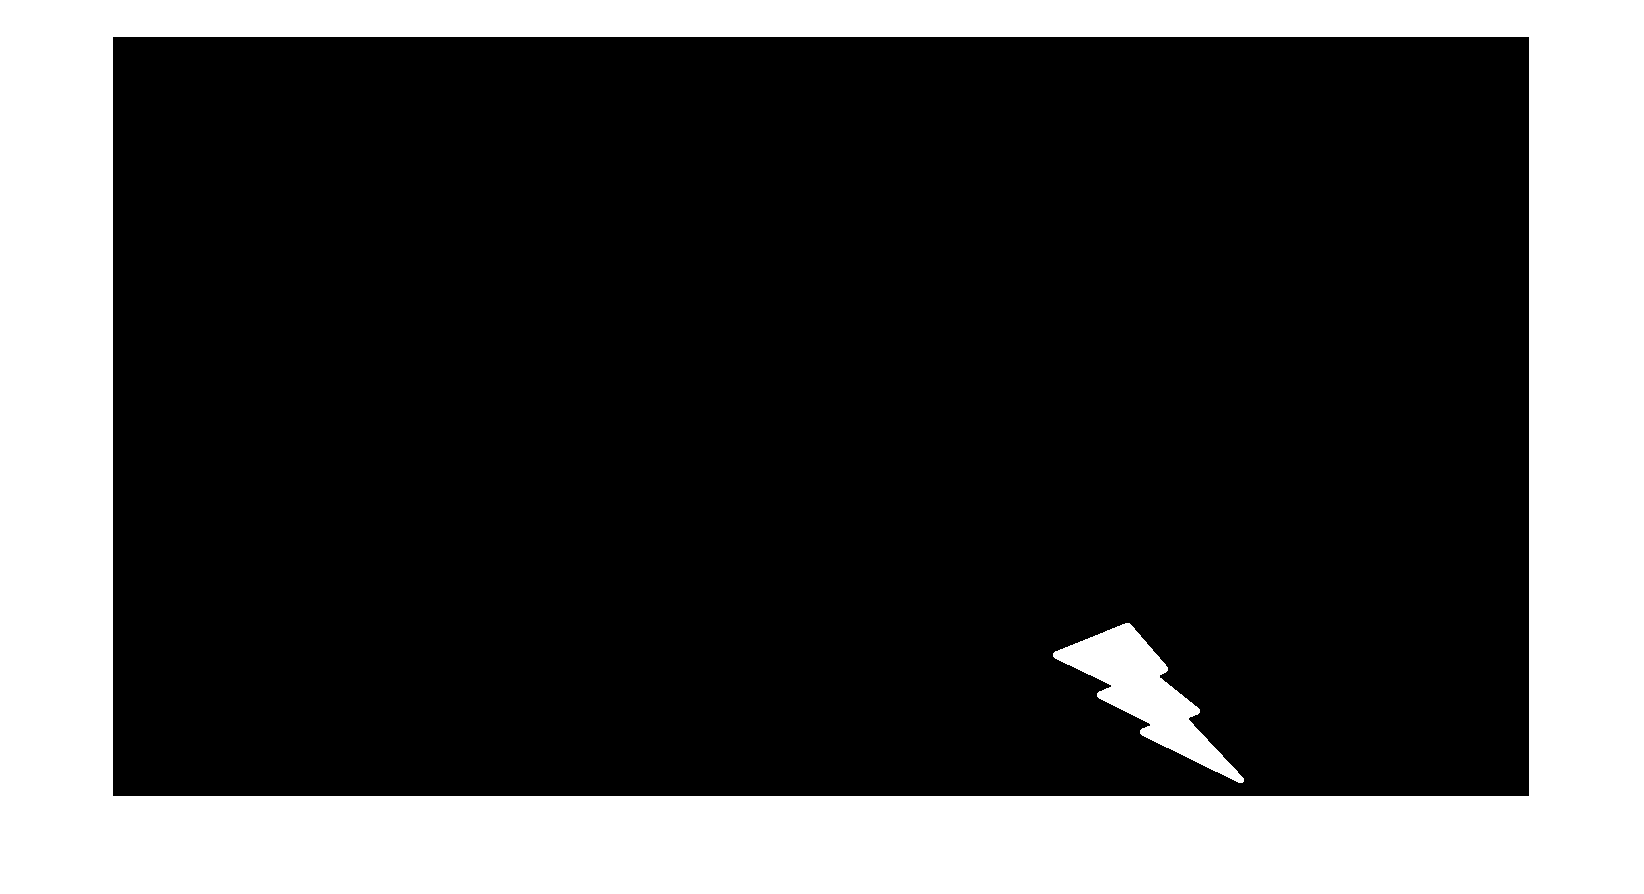


idx=find(array<(Mean-Std));
L1=ismember(label,idx);
L1=I.*L1;
figure('name','objects below mean-std: min FD'),imshow(L1);

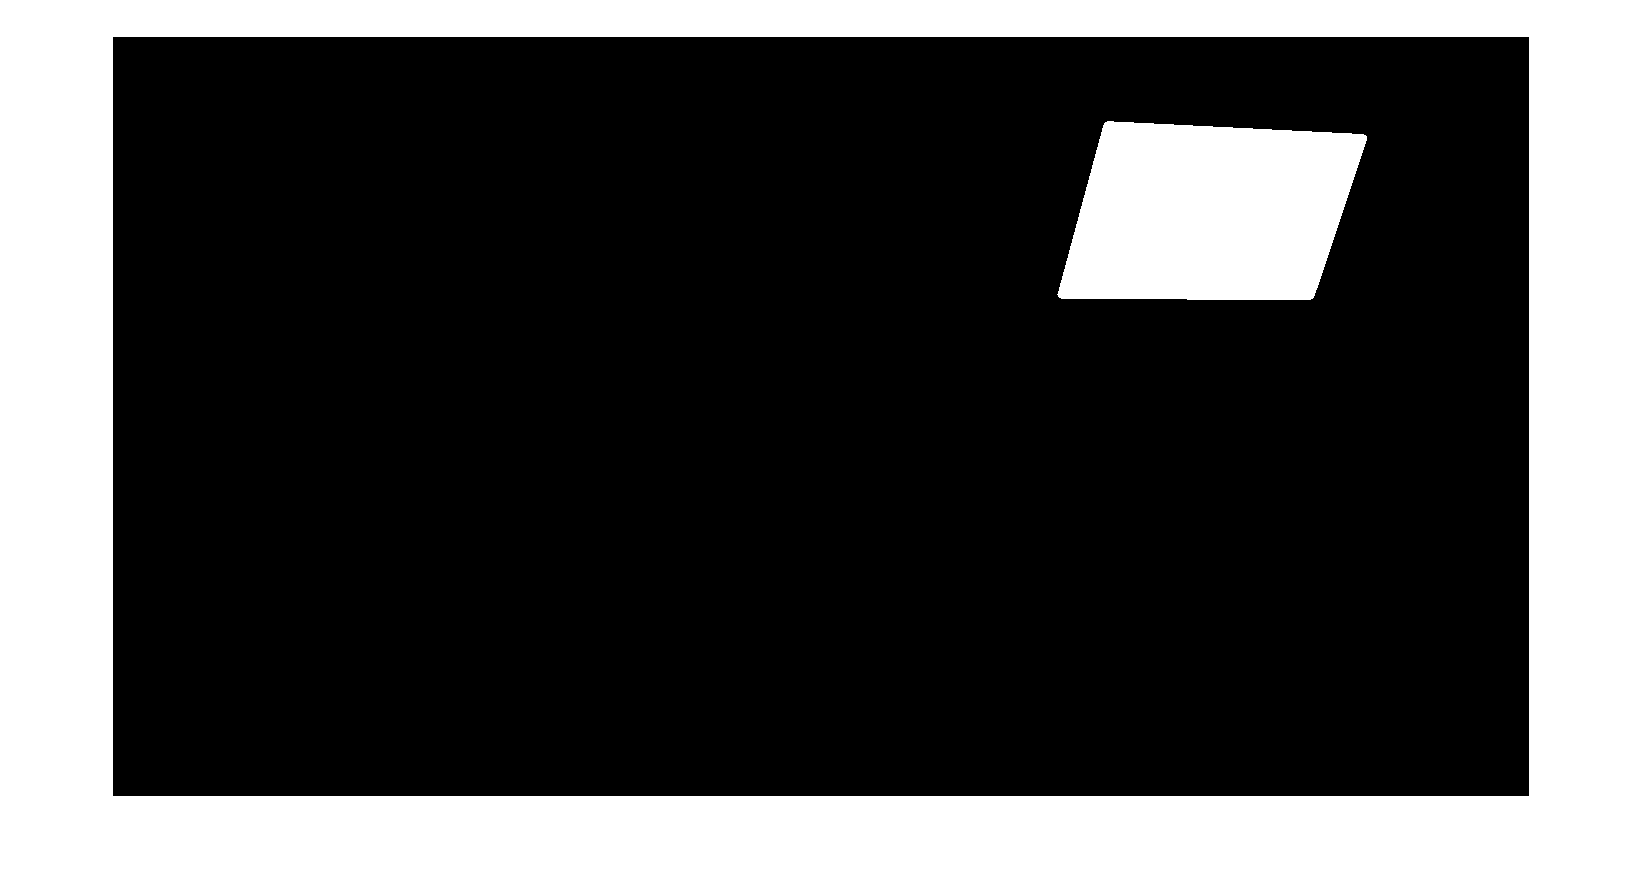


idx=find(array>(Mean+Std));
L2=ismember(label,idx);
L2=I.*L2;
figure('name','objects above mean+std: min FD'),imshow(L2);

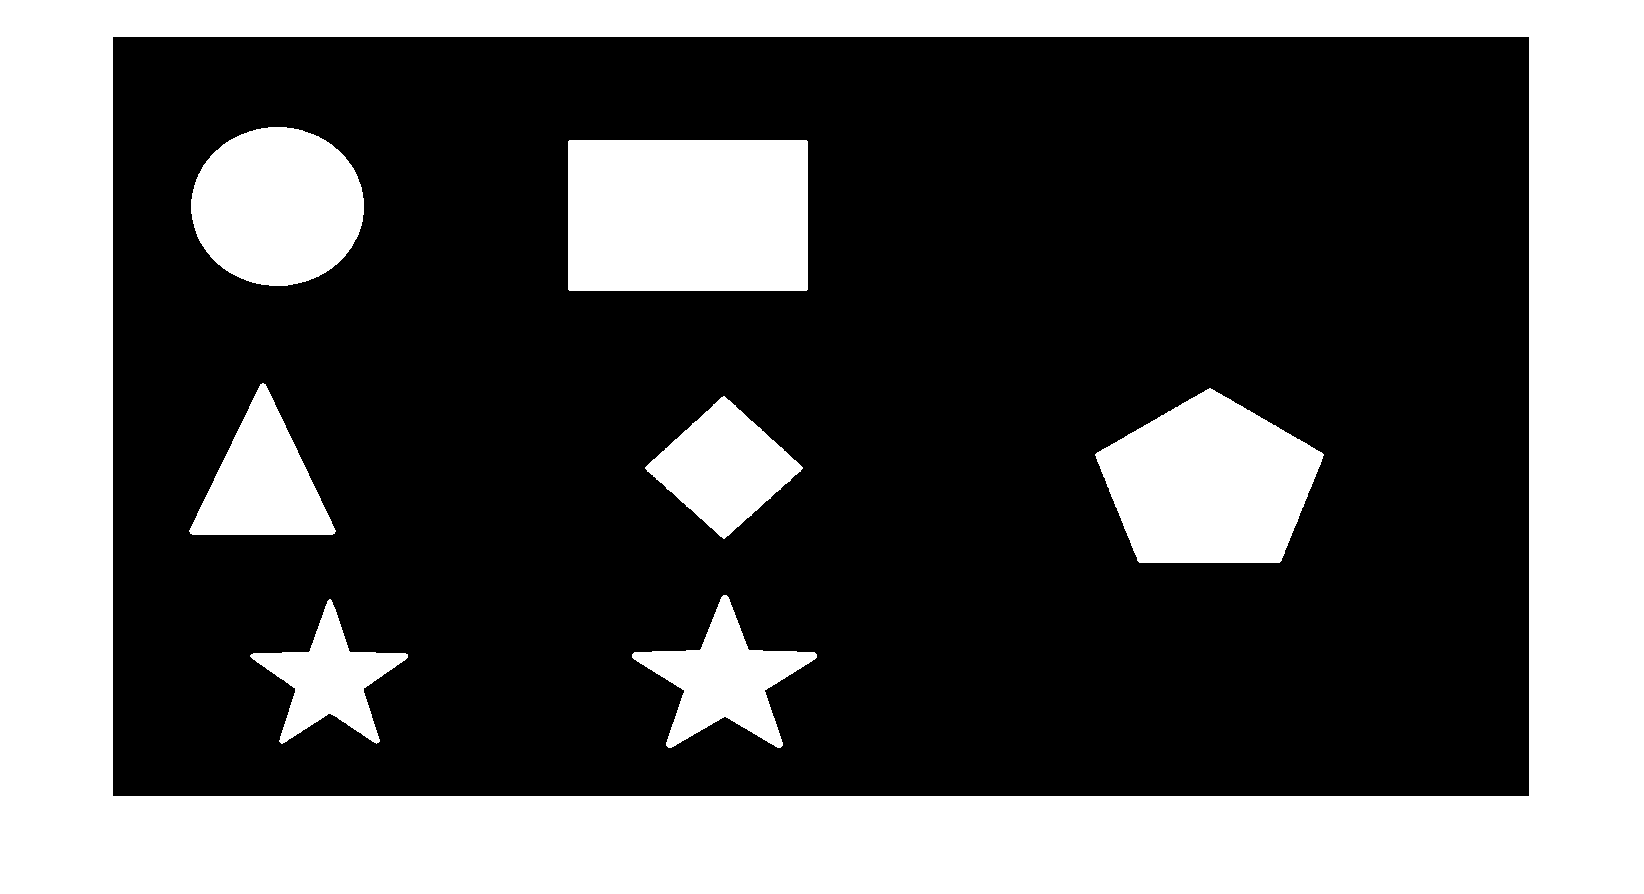


idx=find((array<(Mean+Std))&(array>(Mean-Std)));
L3=ismember(label,idx);
L3=I.*L3;
figure('name','objects between mean-std and mean+std: min FD'),imshow(L3);

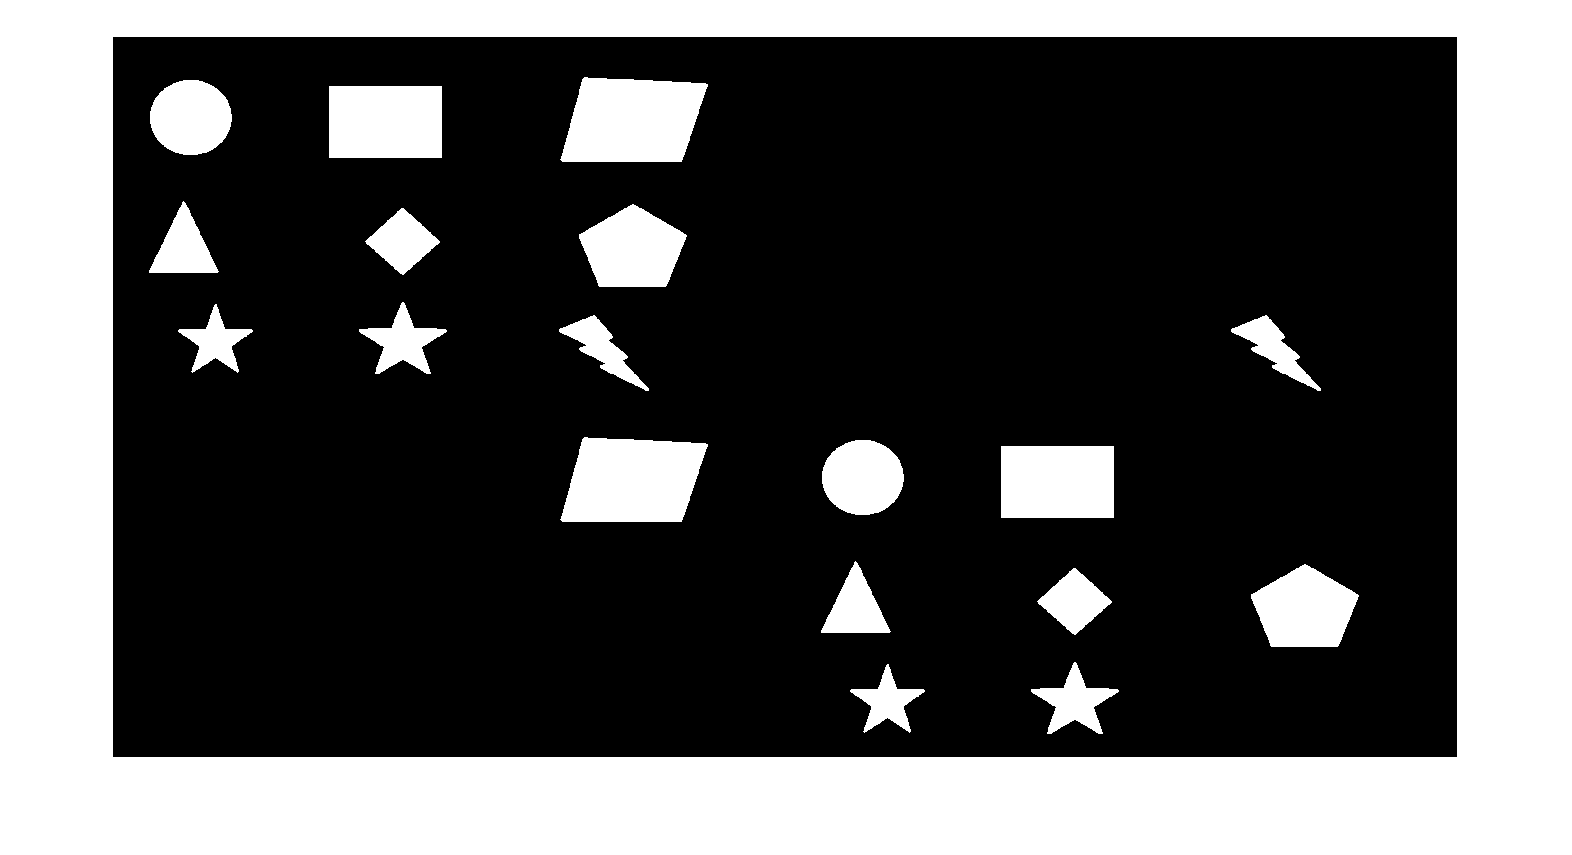

figure(6)
montage({I,L1,L2,L3})

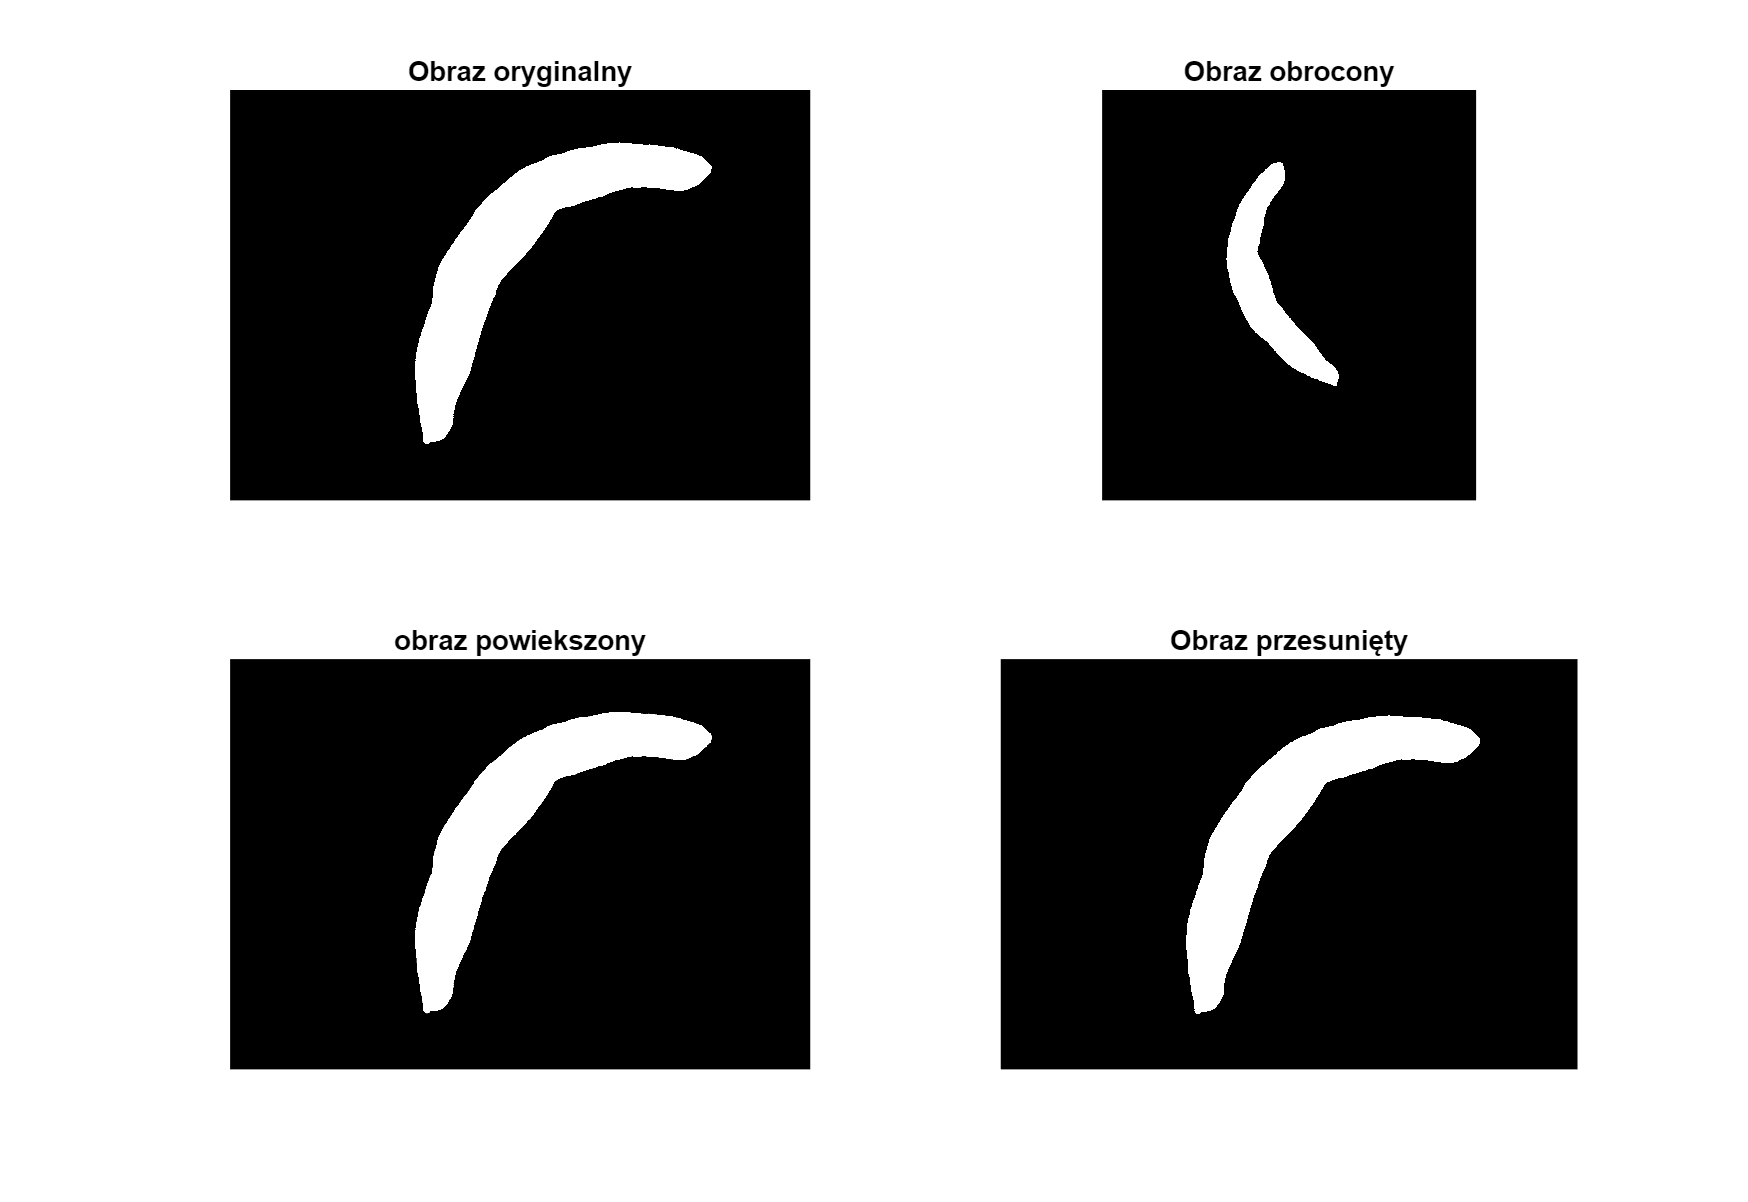

 
I=imread("image2.jpg");

I=rgb2gray(I);

I=imbinarize(I,0.5);



oryginal = 1-I;
obrot =imrotate(oryginal,60);
rozmiar =imresize(oryginal,3);
translacja=imtranslate(oryginal,[15,25],'OutputView','full');
figure(1);
subplot(2,2,1);
imshow(oryginal);
title('Obraz oryginalny');
subplot(2,2,2);
imshow(obrot);
title('Obraz obrocony');
subplot(2,2,3);
imshow(rozmiar);
title('obraz powiekszony');
subplot(2,2,4); imshow(translacja);
title('Obraz przesunięty');







ph(1,:)= abs(log(invmom(oryginal)));
ph(2,:) = abs(log(invmom(obrot)));
ph(3,:) = abs(log(invmom(rozmiar)));
ph(4,:)=abs(log(invmom(translacja)))

ph =     0.6060    1.5967    2.8040    4.8785    9.3428    6.5121   10.1785
    0.6059    1.5966    2.8040    4.8785    9.3429    6.5121   10.1777
    0.6060    1.5967    2.8040    4.8785    9.3428    6.5121   10.1785
    0.6060    1.5967    2.8040    4.8785    9.3428    6.5121   10.1785


Hu moments are invariant to shifting, rotating and scaling


coeffi(oryginal)

ans = struct with fields:
     WM: 0.8040
    WC1: 1.0416e+03
    WC2: 1.8791e+03
     WF: 0.9825


coeffi(obrot)

ans = struct with fields:
     WM: 0.9234
    WC1: 1.0416e+03
    WC2: 2.0034e+03
     WF: 0.5023


coeffi(rozmiar)

ans = struct with fields:
     WM: [-0.4984 0.2748 -0.4984 -0.4984 4.5239 -0.4984 -0.4984 2.6628 -0.4984 -0.4984 0.9793 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 0.0801 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 -0.4984 … ]
    WC1: [2.2568 5.2926 2.2568 2.2568 22.5676 2.2568 2.2568 3.1364e+03 2.2568 2.2568 8.1369 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 4.5135 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 2.2568 … ]
    WC2: [1.1319 6.7469 1.1319 1.1319 124.6616 1.1319 1.1319 1.1488e+04 1.1319 1.1319 16.1052 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 4.8752 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 1.1319 … ]
     WF: [1 0.1818 1 1 0.0100 1 1 0.9825 1 1 0.0769 1 1 1 1 1 1 1 1 0.2500 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0.2500 1 1 1 1 1 1 1 1 1 1 0.2500 1 1 1 1 0.2500 1 1 1 1 1 1 1 1 1 1 1 1 1

coeffi(translacja)

ans = struct with fields:
     WM: 0.8040
    WC1: 1.0416e+03
    WC2: 1.8791e+03
     WF: 0.9825


Malinowska Coefficient and Feret Coefficient stayed invariant for translation of the image. So is the second circularity coefficient.

First circularity coeff was consistent with the original for both rotation and translation.

function [coeff]=coeffi(I)
[label,num]=bwlabel(I);

feats = regionprops(label,'all');
for i=1:num
Ob=feats(i).Perimeter;
S=feats(i).Area;
coeff.WM(i)=(Ob/(2*((pi*S)^(0.5))))-1;
end

for i = 1:num
Pole = feats(i).Area;
coeff.WC1(i) = 2*(sqrt(Pole/pi));
end 

for i=1:num
Ob=feats(i).Perimeter;
coeff.WC2(i)=Ob/pi;
end

for i = 1:num
Dh = feats(i).BoundingBox(3);
Dv = feats(i).BoundingBox(4);
coeff.WF(i) = Dh/Dv;
end
end